clear
close all
clc

% cambia path

addpath '/Users/Lorenzo/Desktop/Tesi/Functions&Data'

addpath '/Users/Lorenzo/Desktop/Tesi/TesiVero'


load BankClients.mat

addpath '/Users/Lorenzo/Desktop/Tesi'

% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID

NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; % create a matrix 
XNum = rescale(XNum); % normalize in [0, 1]
% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features

% Encoding (ie create dummy variables)
%grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end)]; % To use the dummy variables in a model, we must delete a column
            % ABBIAMO DECISO DI TENERE ANCHE L'ULTIMA COLONNA DELLE DUMMY
end

X = [XCat XNum];




tabulate(Data.Investments)

  Value    Count   Percent
      1     1314     26.28%
      2     1496     29.92%
      3     2190     43.80%



tabulate(Data.Job)

  Value    Count   Percent
      1      609     12.18%
      2     3284     65.68%
      3      144      2.88%
      4      107      2.14%
      5      856     17.12%



D1 = pdist(X, @MixDistanceL1copia);   

% abbiamo cambiato la distanza separando le dummy date da Investments per
% poter regolare il loro peso: vedi file 
%calculate the distance between every pair of objects in the dataset using MixDistanceL1
D2 = pdist(X, @MixDistanceL2copia); 
%calculate the distance between every pair of objects in the dataset using MixDistanceL2

%linkages using the L1 mix distance
single1 = linkage(D1, "single");
complete1 = linkage(D1, "complete");
average1 = linkage(D1, "average");
weighted1 = linkage(D1, "weighted");
%linkages using the L2 mix distance
single2 = linkage(D2, "single");
complete2 = linkage(D2, "complete");
average2 = linkage(D2, "average");
weighted2 = linkage(D2, "weighted");

c_single1 = cophenet(single1,D1)

c_single1 = 0.8702


c_single2 = cophenet(single2,D2)

c_single2 = 0.8736


c_average1 = cophenet(average1,D1)

c_average1 = 0.8960


c_average2 = cophenet(average2,D2)   % migliore, 0.8992

c_average2 = 0.8992


c_complete1 = cophenet(complete1,D1)

c_complete1 = 0.8917


c_complete2 = cophenet(complete2,D2)

c_complete2 = 0.8914


c_weighted1 = cophenet(weighted1,D1)

c_weighted1 = 0.8911


c_weighted2 = cophenet(weighted2,D2)

c_weighted2 = 0.8960

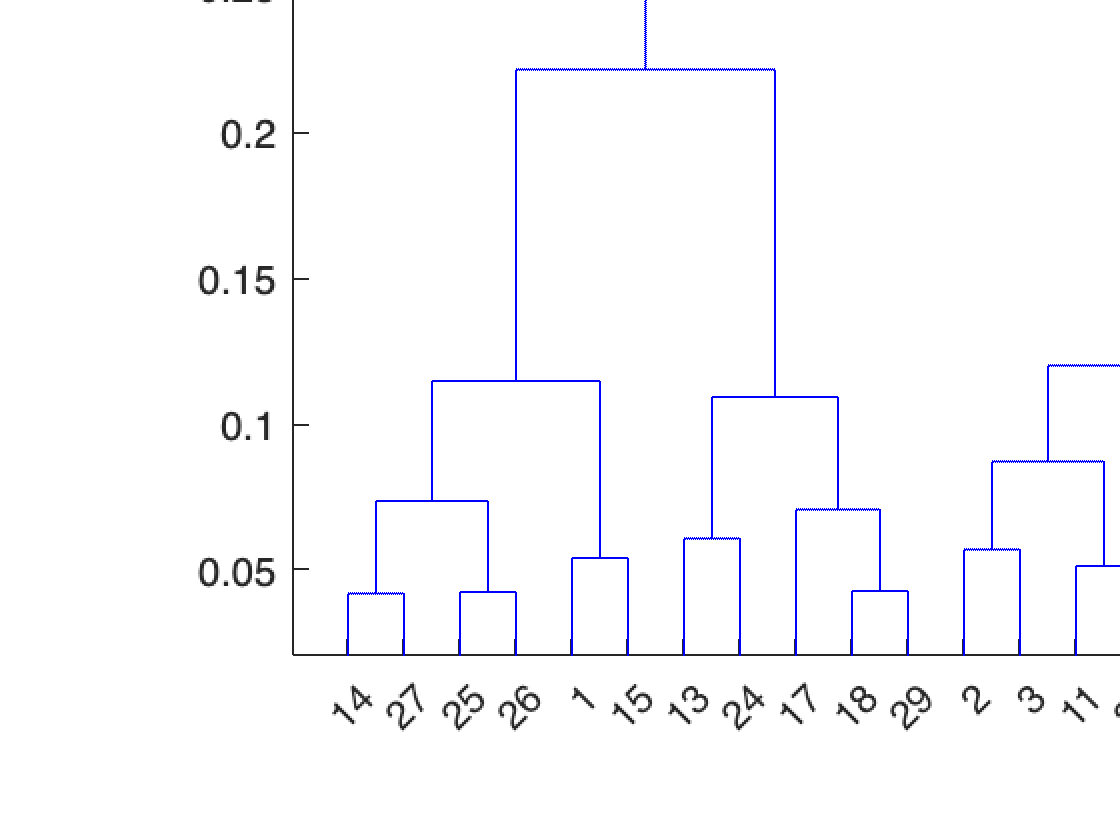

average2 = linkage(D2, "average");

figure
dendrogram(average2)
title("Average Linkage")

%sembra che 6 possa andare, vediamo cosa dicono gli indici

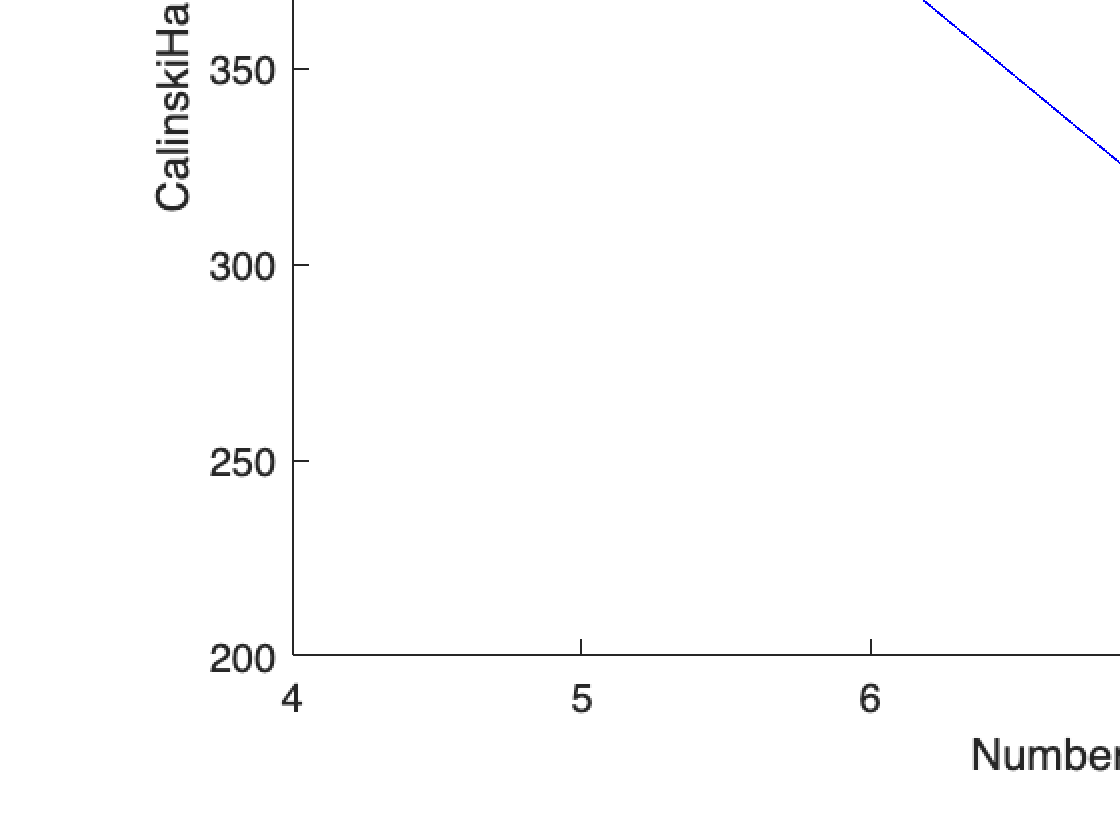

T4 = cluster(average2,'maxclust',4);

T5 = cluster(average2,'maxclust',5);

T6 = cluster(average2,'maxclust',6);

T7 = cluster(average2,'maxclust',7);

T8 = cluster(average2,'maxclust',8);

T9 = cluster(average2,'maxclust',9);

T10 = cluster(average2,'maxclust',10);


clust = [T4 T5 T6 T7 T8 T9 T10];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)


eva1

eva1 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 5000
         InspectedK: [4 5 6 7 8 9 10]
    CriterionValues: [542.2036 428.1838 378.6860 317.4938 275.2396 242.2770 216.3394]
           OptimalK: 4


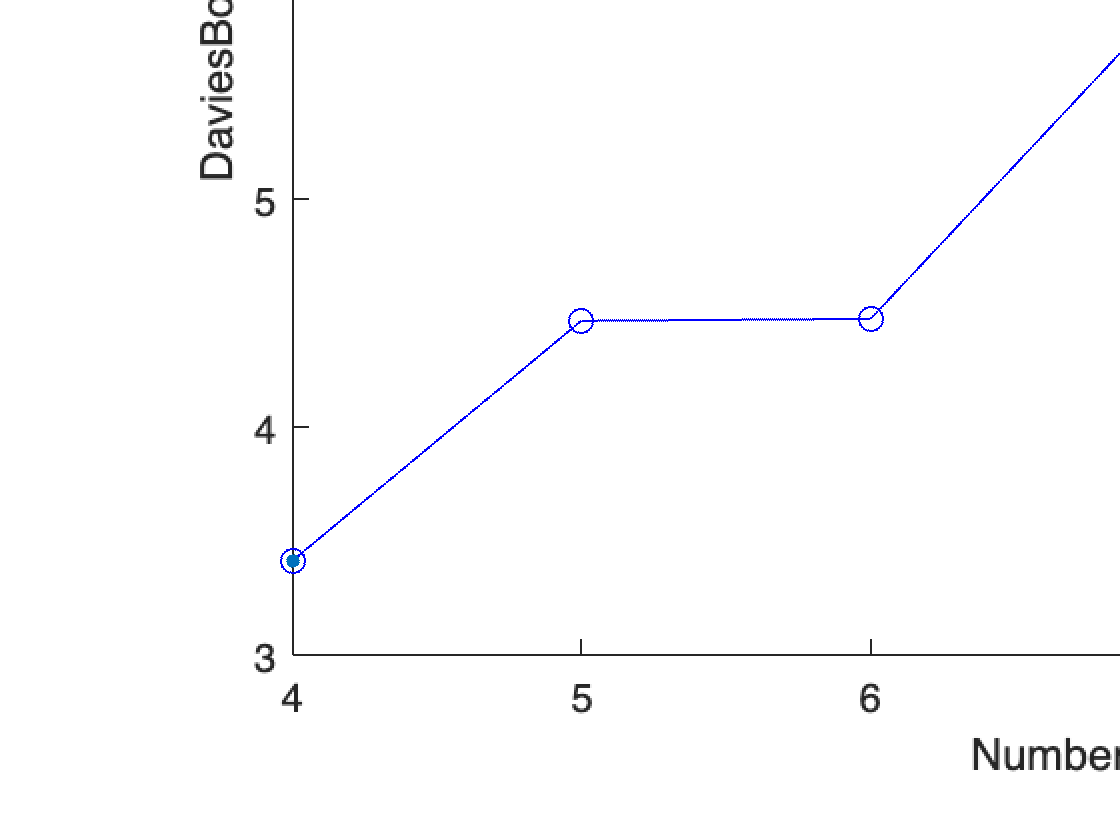


eva2 = evalclusters(X,clust,'DaviesBouldin');
figure
plot(eva2)


eva2

eva2 =   DaviesBouldinEvaluation with properties:

    NumObservations: 5000
         InspectedK: [4 5 6 7 8 9 10]
    CriterionValues: [3.4160 4.4678 4.4766 5.8266 6.5993 7.0760 8.0127]
           OptimalK: 4


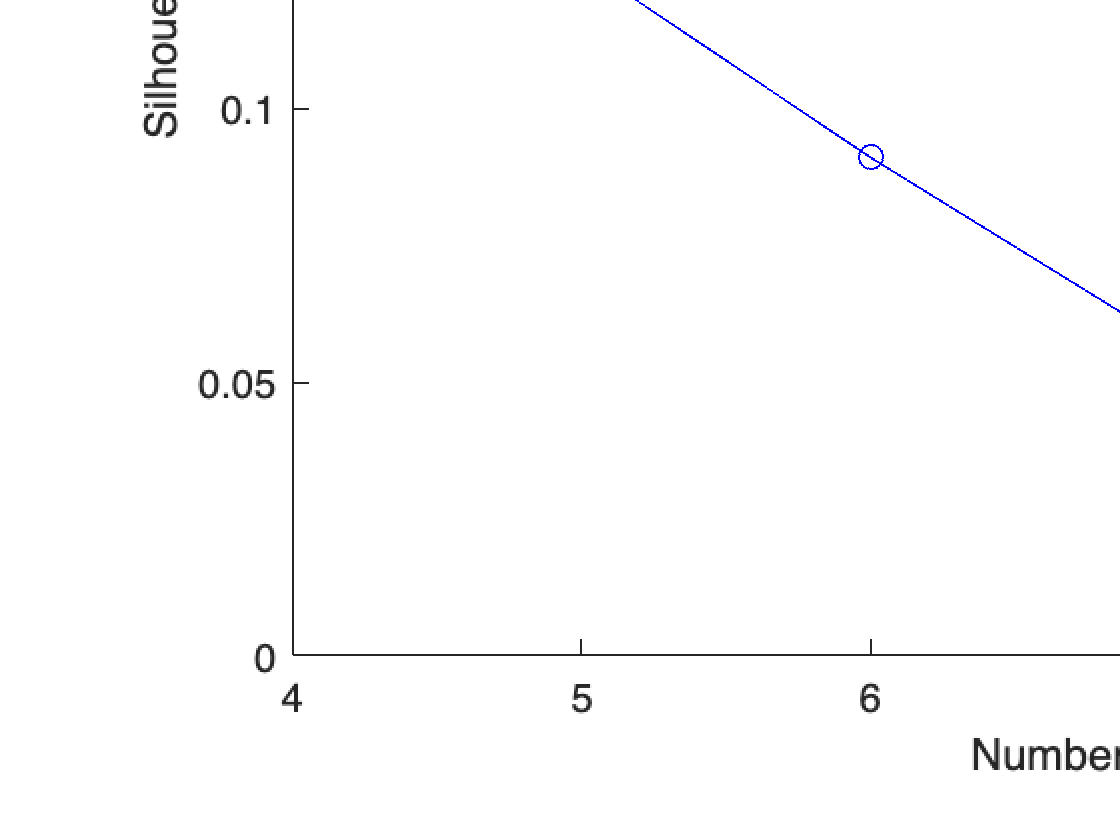


eva3 = evalclusters(X,clust,'silhouette');
figure
plot(eva3)


eva3

eva3 =   SilhouetteEvaluation with properties:

    NumObservations: 5000
         InspectedK: [4 5 6 7 8 9 10]
    CriterionValues: [0.2471 0.1264 0.0910 0.0583 0.0332 0.0189 0.0125]
           OptimalK: 4


%trovo tabelle coi valori per ogni scelta del numero di cluster
tabulate(T6)

  Value    Count   Percent
      1      737     14.74%
      2      759     15.18%
      3      804     16.08%
      4     1386     27.72%
      5      770     15.40%
      6      544     10.88%


tabulate(T5)

  Value    Count   Percent
      1      804     16.08%
      2     1386     27.72%
      3      770     15.40%
      4      544     10.88%
      5     1496     29.92%


%NOSTRA SCELTA scegliamo 6 cluster

tabulate(T6)

  Value    Count   Percent
      1      737     14.74%
      2      759     15.18%
      3      804     16.08%
      4     1386     27.72%
      5      770     15.40%
      6      544     10.88%



tabulate(T7)

  Value    Count   Percent
      1      450      9.00%
      2      309      6.18%
      3      737     14.74%
      4      804     16.08%
      5     1386     27.72%
      6      770     15.40%
      7      544     10.88%



tabulate(T8)

  Value    Count   Percent
      1      549     10.98%
      2      837     16.74%
      3      450      9.00%
      4      309      6.18%
      5      737     14.74%
      6      804     16.08%
      7      770     15.40%
      8      544     10.88%



tabulate(T9)

  Value    Count   Percent
      1      233      4.66%
      2      311      6.22%
      3      549     10.98%
      4      837     16.74%
      5      450      9.00%
      6      309      6.18%
      7      737     14.74%
      8      804     16.08%
      9      770     15.40%


% Select the number of the cluster
C1 = BankClients(T6==1,:);
C2 = BankClients(T6==2,:);
C3 = BankClients(T6==3,:);
C4 = BankClients(T6==4,:);
C5 = BankClients(T6==5,:);
C6 = BankClients(T6==6,:);

writetable(C1, 'C1.csv');
writetable(C2, 'C2.csv');
writetable(C3, 'C3.csv');
writetable(C4, 'C4.csv');
writetable(C5, 'C5.csv');
writetable(C6, 'C6.csv');

% Frequency tables
%tabulate(C1.Job)
%tabulate(C1.Area)
%tabulate(C1.CitySize)
tabulate(C1.Investments)

  Value    Count   Percent
      1        0      0.00%
      2      737    100.00%
      3        0      0.00%



summary(C1(:,"Age"))

Variables:

    Age: 737×1 double

        Values:

            Min          64   
            Median       81   
            Max          95   



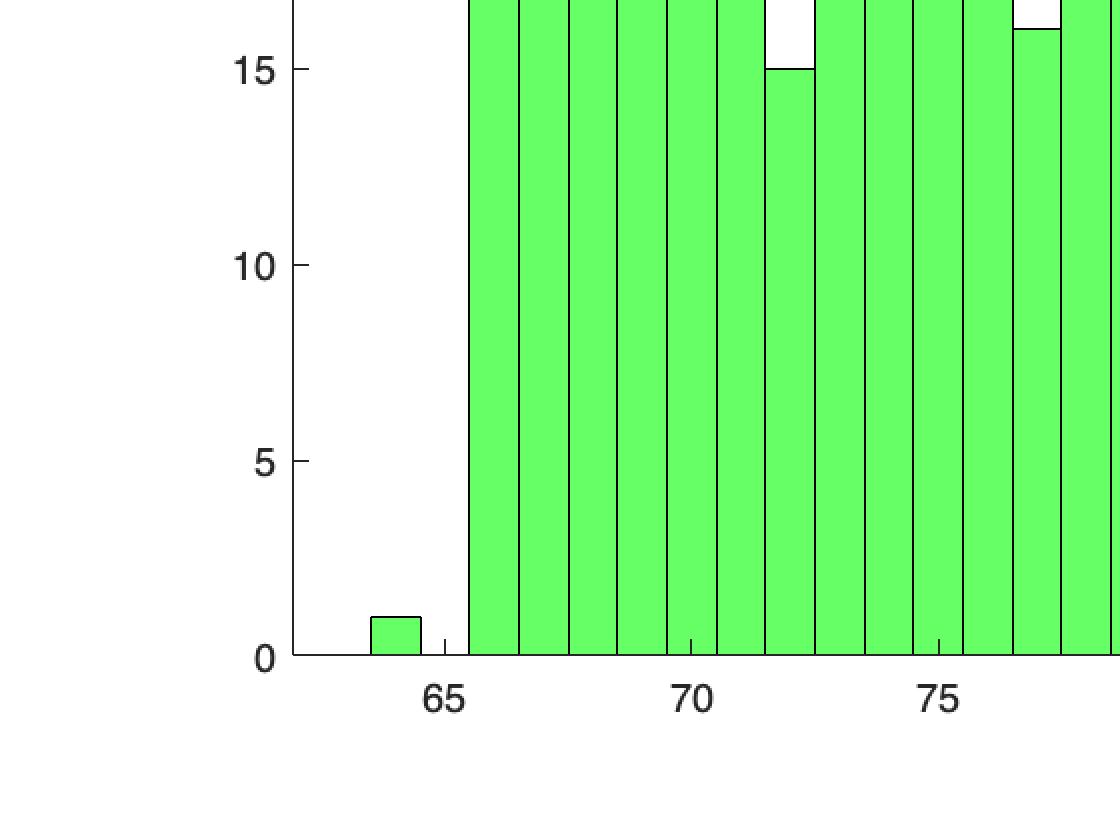

histogram(C1.Age, 'FaceColor','g')
title('Age')

mean(C1.Age) %vecchi

ans = 81.0339

std(C1.Age)

ans = 8.7332

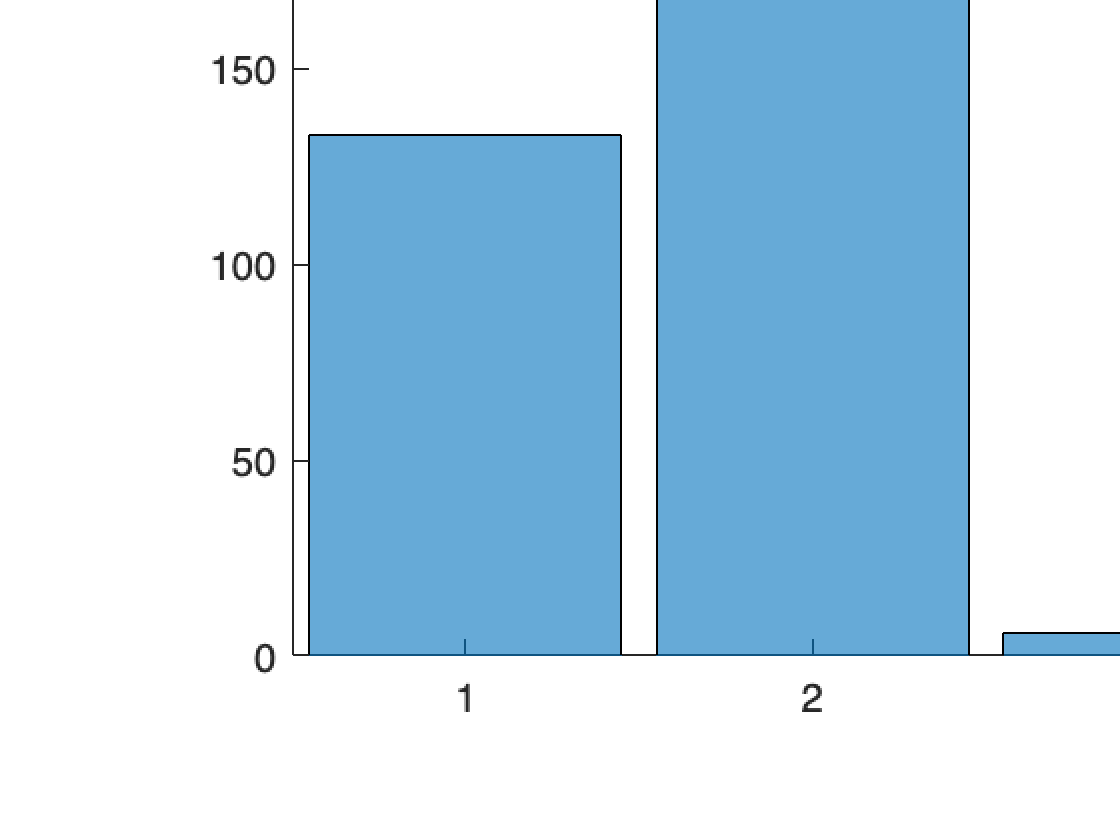


histogram(C1.Job)
title('Job')

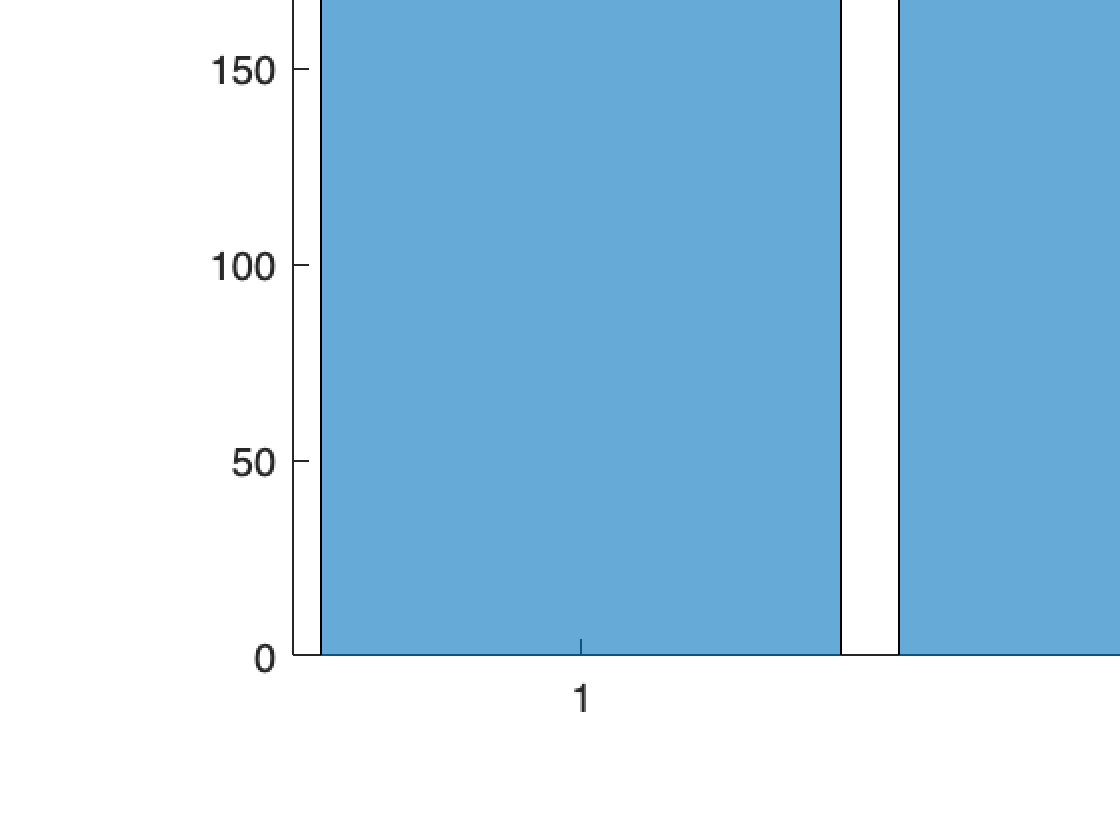



histogram(C1.CitySize)
title('City Size')

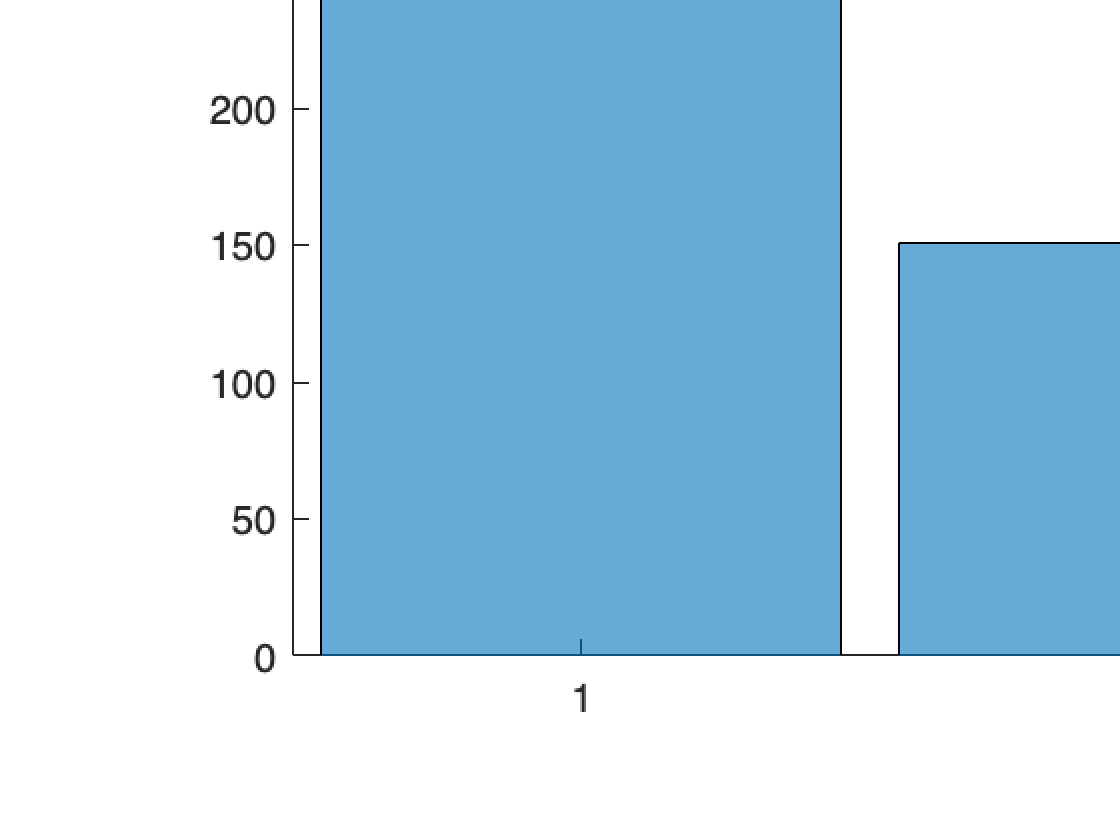




histogram(C1.Area)
title('Area')

num=[2,7:17];
C1num=C1(:, num);
%pairplot(C1(:,num))

summary(C1(:, "Income"))

Variables:

    Income: 737×1 double

        Values:

            Min             0 
            Median    0.44146 
            Max       0.97428 



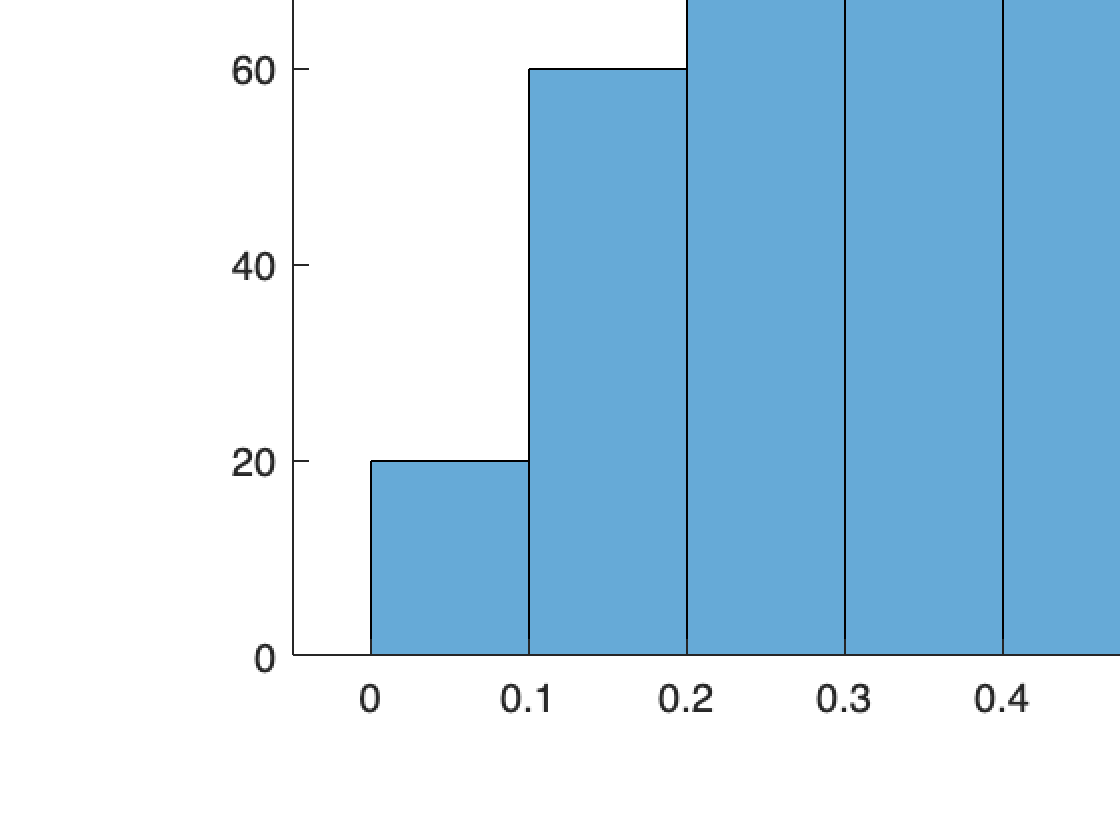

histogram(C1.Income)

mean(C1.Income)

ans = 0.4605


summary(C1(:, "Wealth"))

Variables:

    Wealth: 737×1 double

        Values:

            Min             0 
            Median    0.44876 
            Max       0.98962 



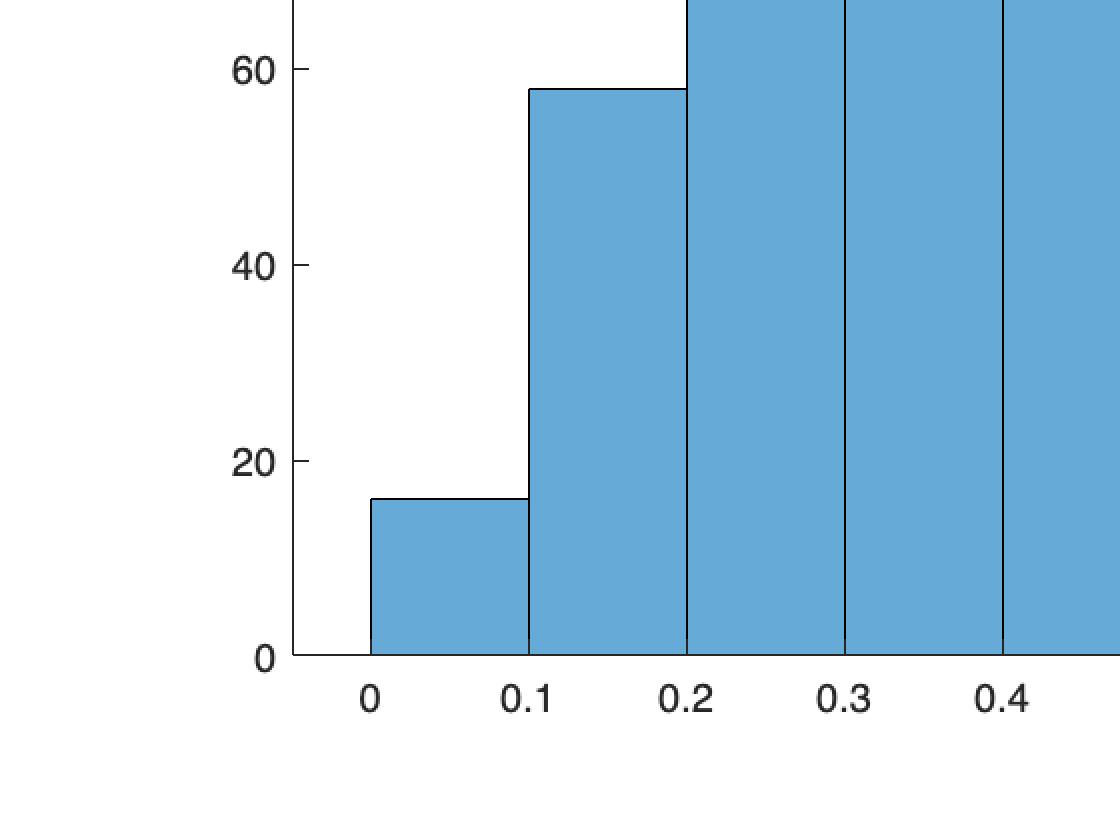

histogram(C1.Wealth)

mean(C1.Wealth)

ans = 0.4645


summary(C1(:, "Debt"))

Variables:

    Debt: 737×1 double

        Values:

            Min             0 
            Median    0.17158 
            Max        0.8881 



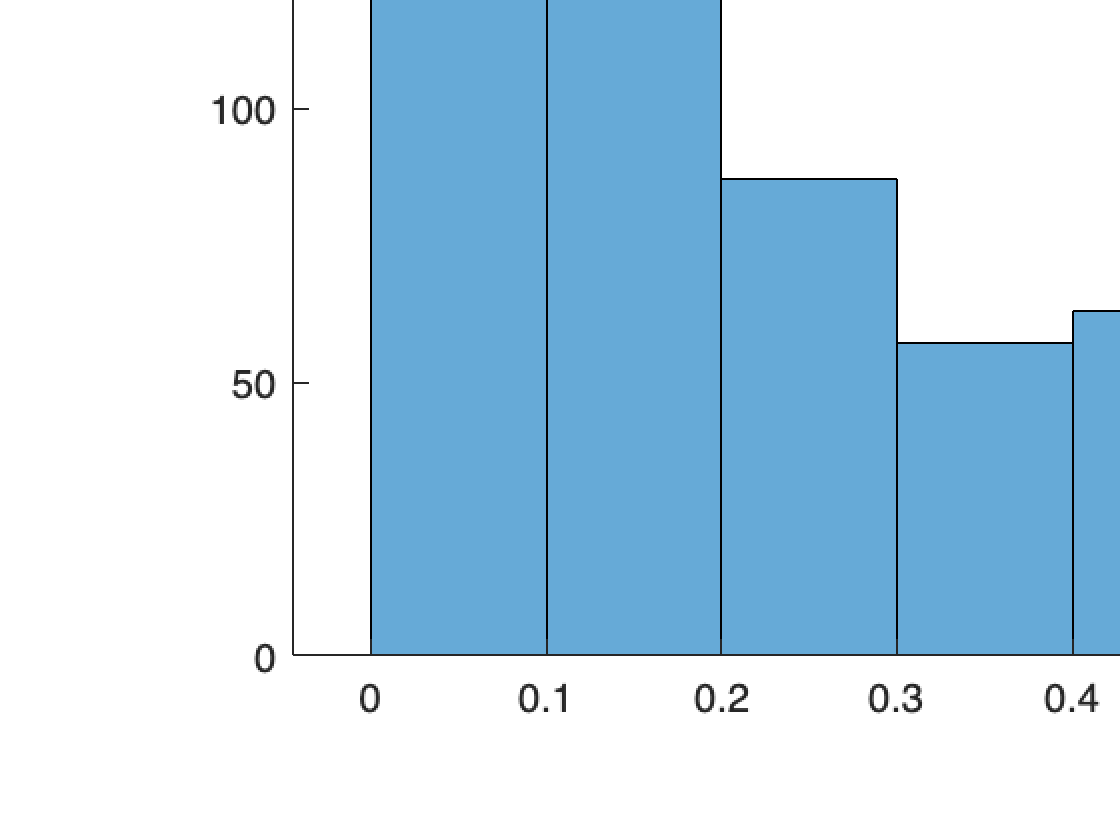

histogram(C1.Debt)

mean(C1.Debt)

ans = 0.2557


summary(C1(:, "FinEdu"))

Variables:

    FinEdu: 737×1 double

        Values:

            Min             0 
            Median    0.39029 
            Max       0.90561 



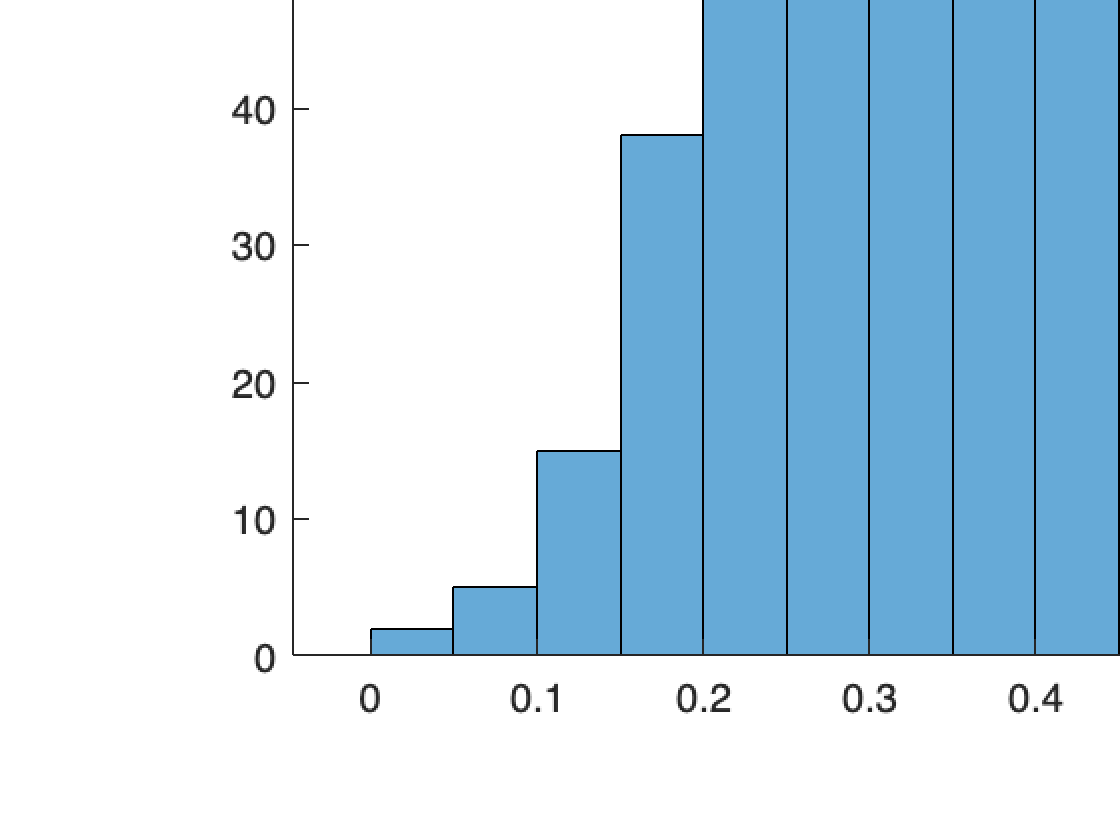

histogram(C1.FinEdu)

mean(C1.FinEdu)

ans = 0.4026


summary(C1(:, "ESG"))

Variables:

    ESG: 737×1 double

        Values:

            Min       0.06868 
            Median    0.60912 
            Max       0.92833 



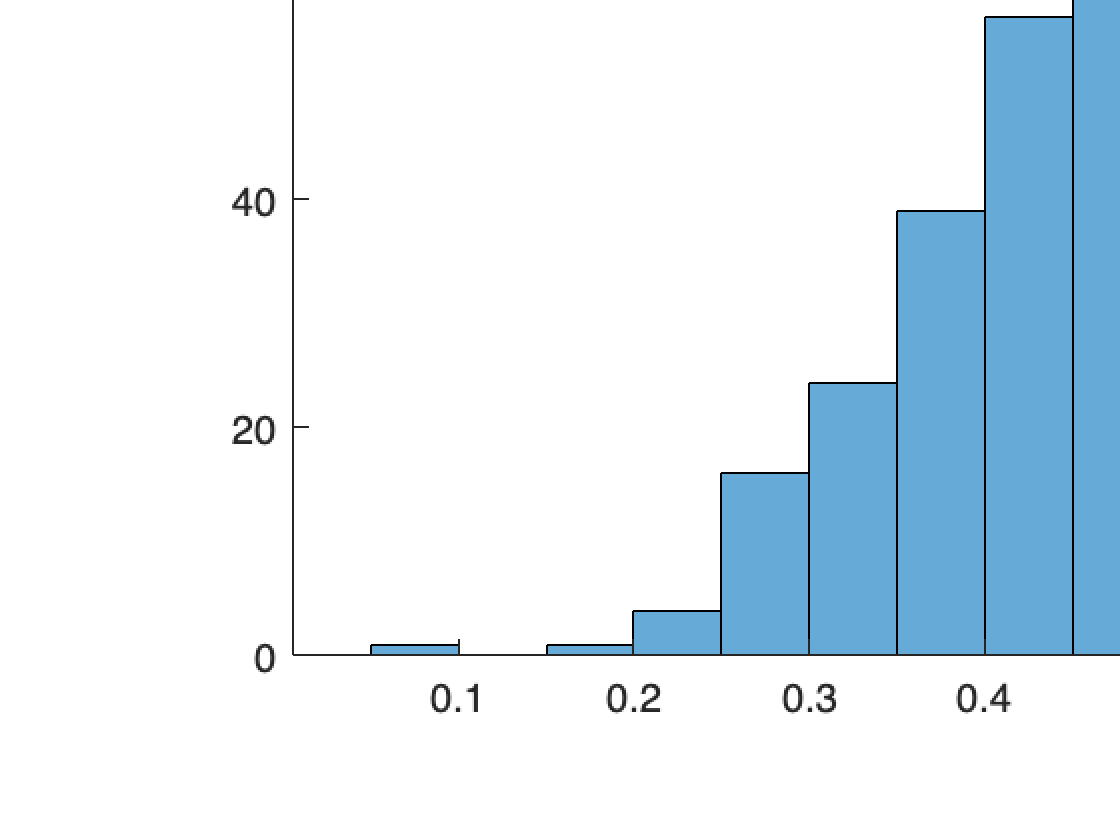

histogram(C1.ESG)

mean(C1.ESG)

ans = 0.5974


summary(C1(:, "Digital"))

Variables:

    Digital: 737×1 double

        Values:

            Min             0 
            Median    0.36057 
            Max       0.95951 



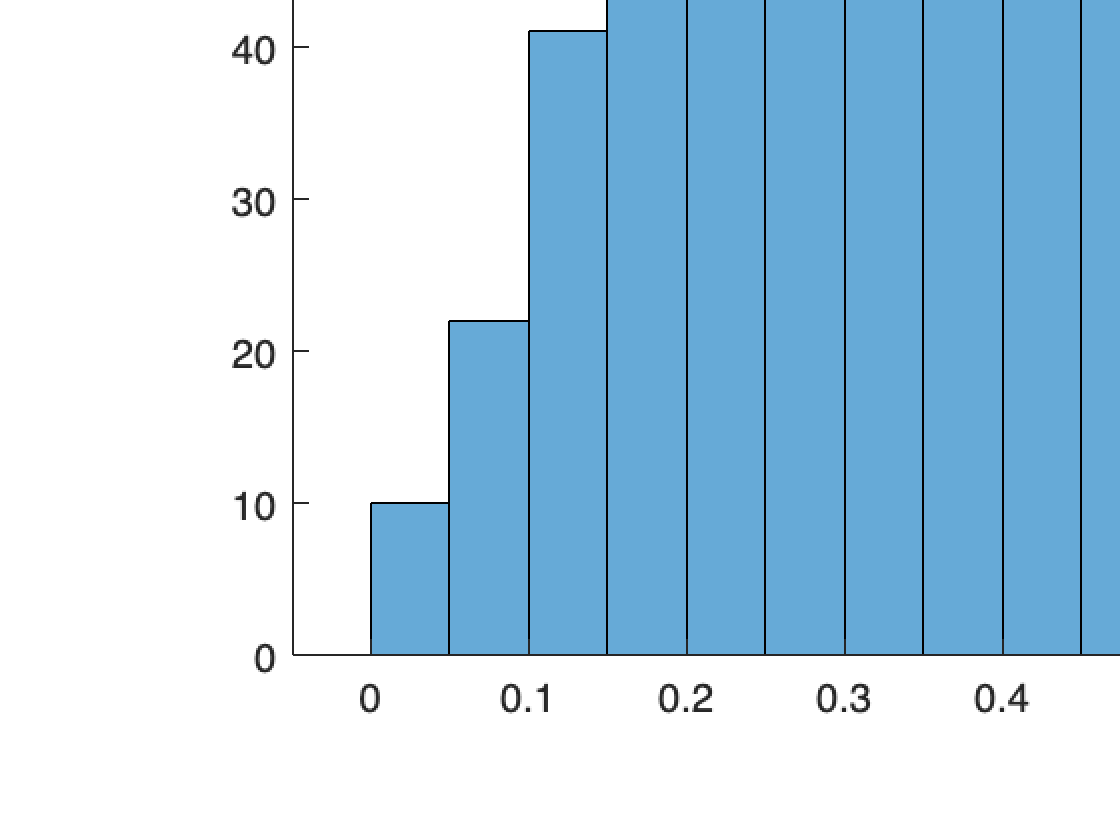

histogram(C1.Digital)

mean(C1.Digital)

ans = 0.3837


summary(C1(:, "BankFriend"))

Variables:

    BankFriend: 737×1 double

        Values:

            Min       0.18609 
            Median    0.62504 
            Max       0.96527 



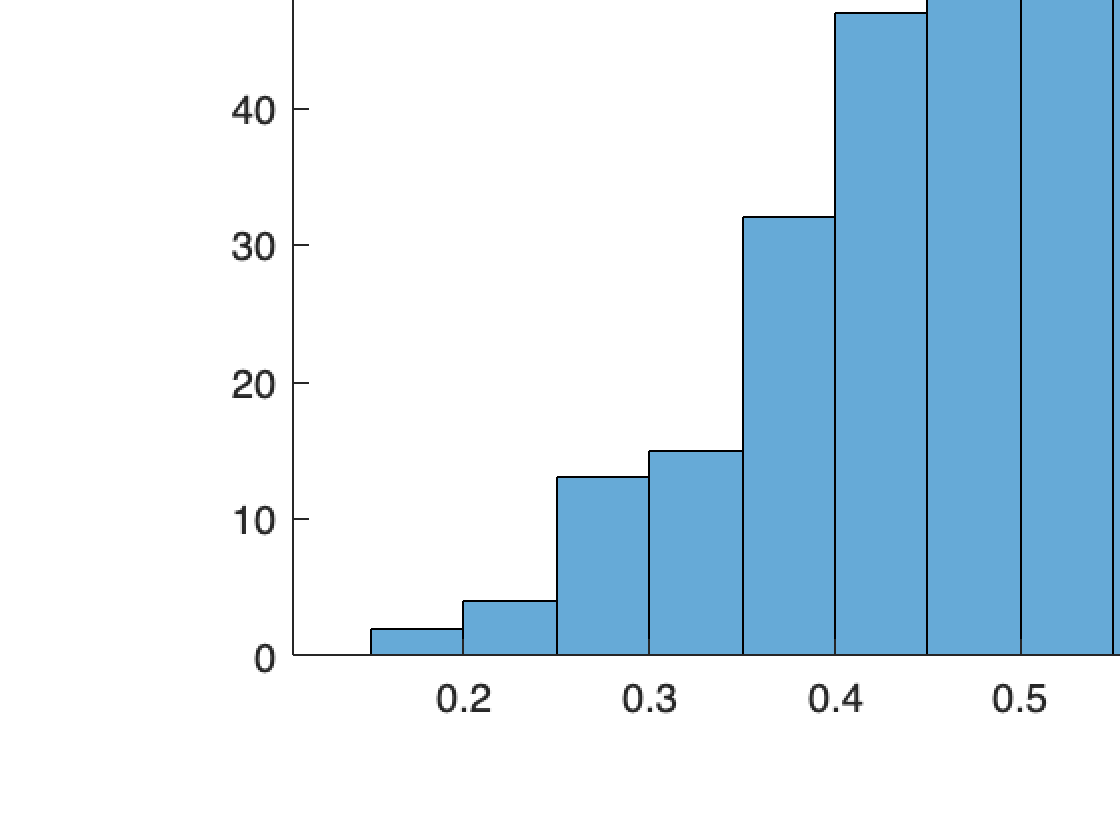

histogram(C1.BankFriend)

mean(C1.BankFriend)

ans = 0.6175


summary(C1(:, "LifeStyle"))

Variables:

    LifeStyle: 737×1 double

        Values:

            Min             0 
            Median    0.28617 
            Max        0.9018 



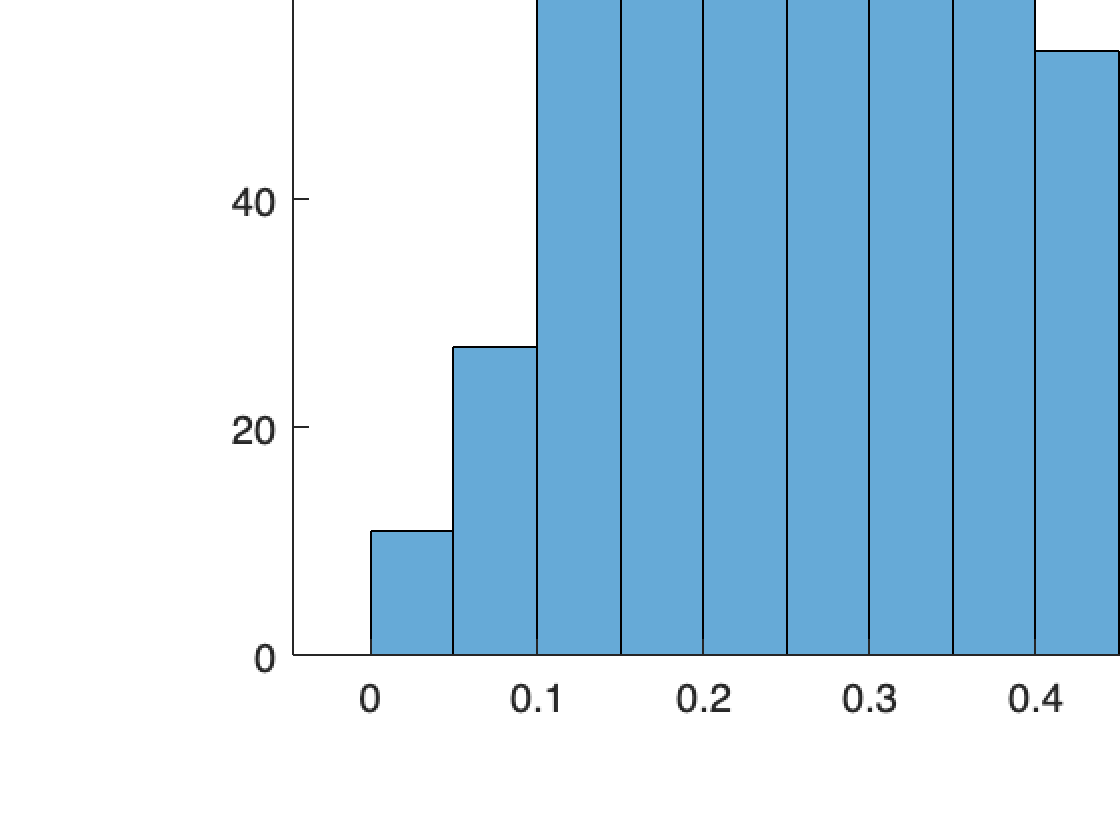

histogram(C1.LifeStyle)

mean(C1.LifeStyle)

ans = 0.3217


summary(C1(:, "Luxury"))

Variables:

    Luxury: 737×1 double

        Values:

            Min             0 
            Median    0.27392 
            Max       0.99591 



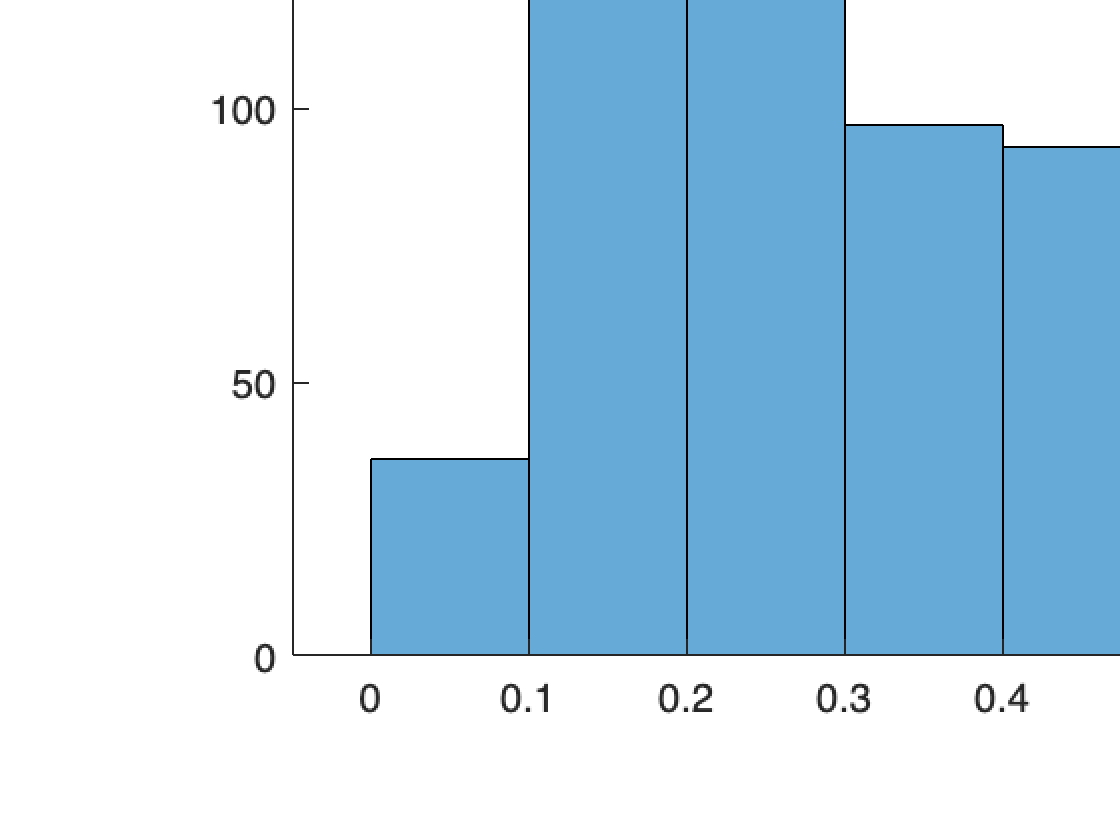

histogram(C1.Luxury)

mean(C1.Luxury)

ans = 0.3308


summary(C1(:, "Saving"))

Variables:

    Saving: 737×1 double

        Values:

            Min       0.004191
            Median     0.38924
            Max        0.92859



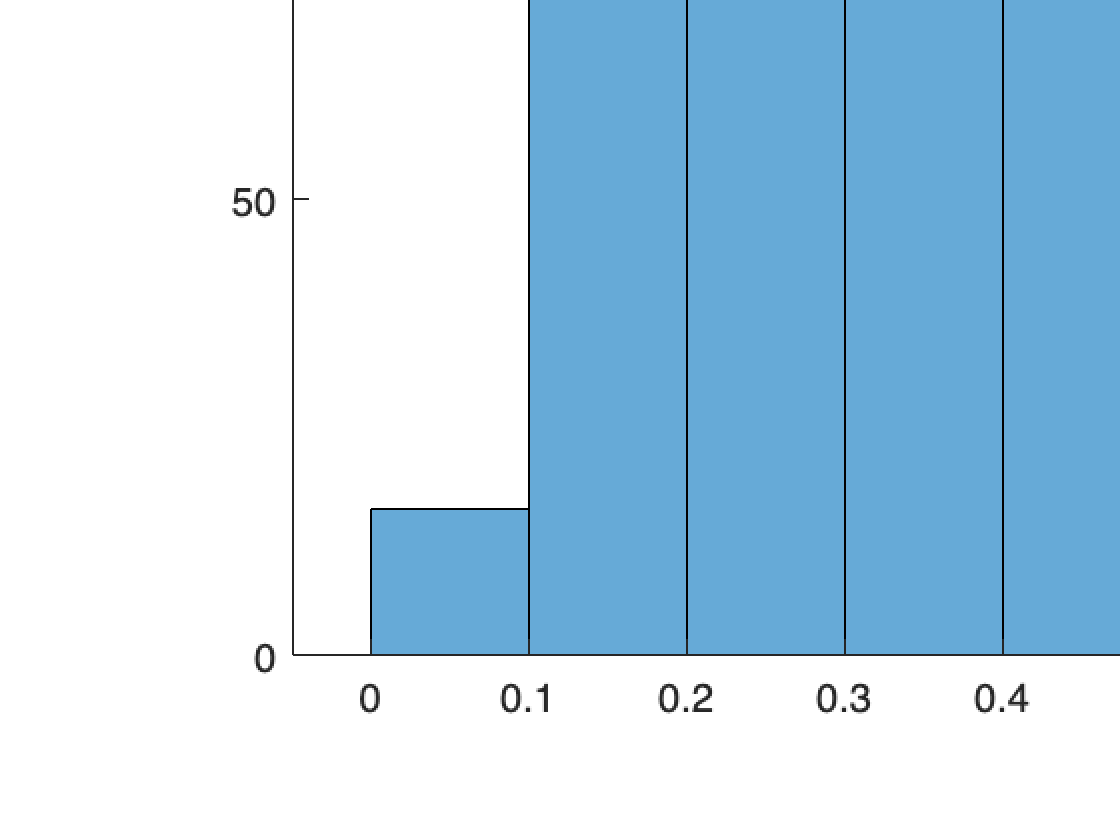

histogram(C1.Saving)

mean(C1.Saving)

ans = 0.4158

C2 = BankClients(T6==2,:);

% Frequency tables
tabulate(C2.Job)

  Value    Count   Percent
      1       79     10.41%
      2      594     78.26%
      3       24      3.16%
      4       19      2.50%
      5       43      5.67%


tabulate(C2.Area)

  Value    Count   Percent
      1      590     77.73%
      2       97     12.78%
      3       72      9.49%


tabulate(C2.CitySize)

  Value    Count   Percent
      1      166     21.87%
      2      239     31.49%
      3      354     46.64%


tabulate(C2.Investments)

  Value    Count   Percent
      1        0      0.00%
      2      759    100.00%
      3        0      0.00%



summary(C2(:,"Age"))

Variables:

    Age: 759×1 double

        Values:

            Min          19   
            Median       48   
            Max          66   



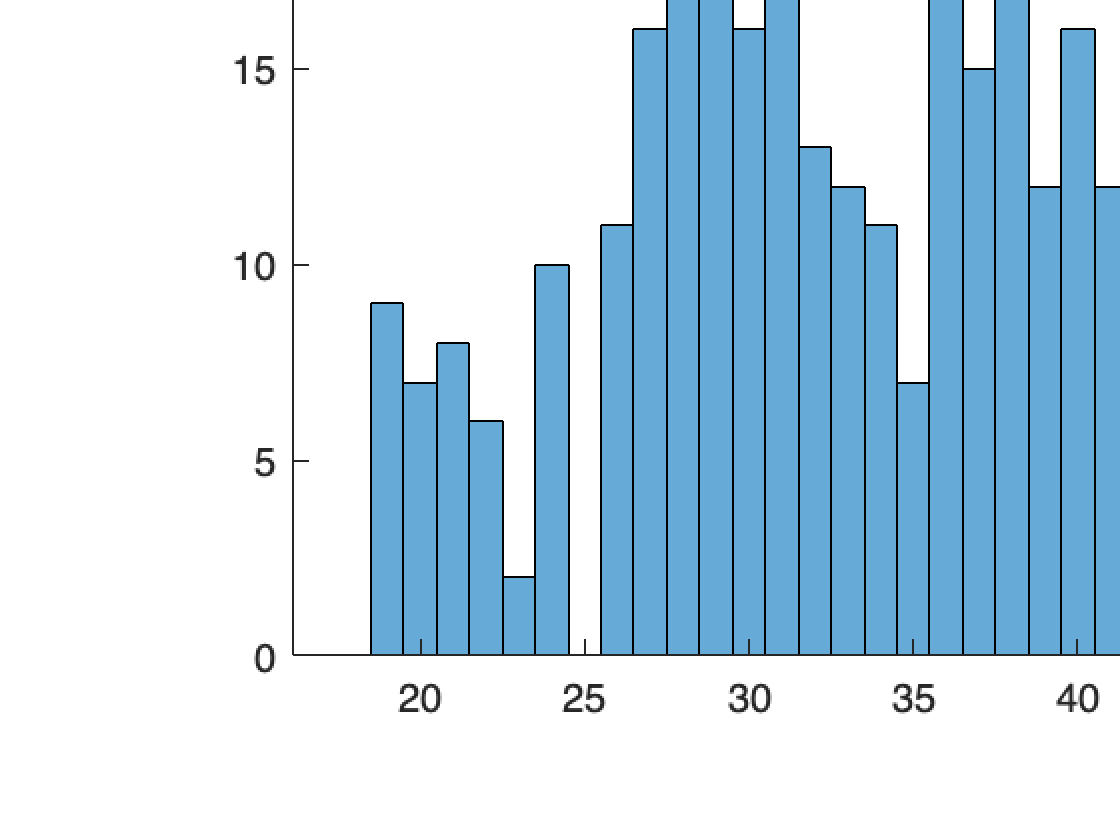

histogram(C2.Age)
title('Age')

mean(C2.Age)

ans = 45.8195


summary(C2(:,"Job"))

Variables:

    Job: 759×1 categorical

        Values:

            1       79   
            2      594   
            3       24   
            4       19   
            5       43   



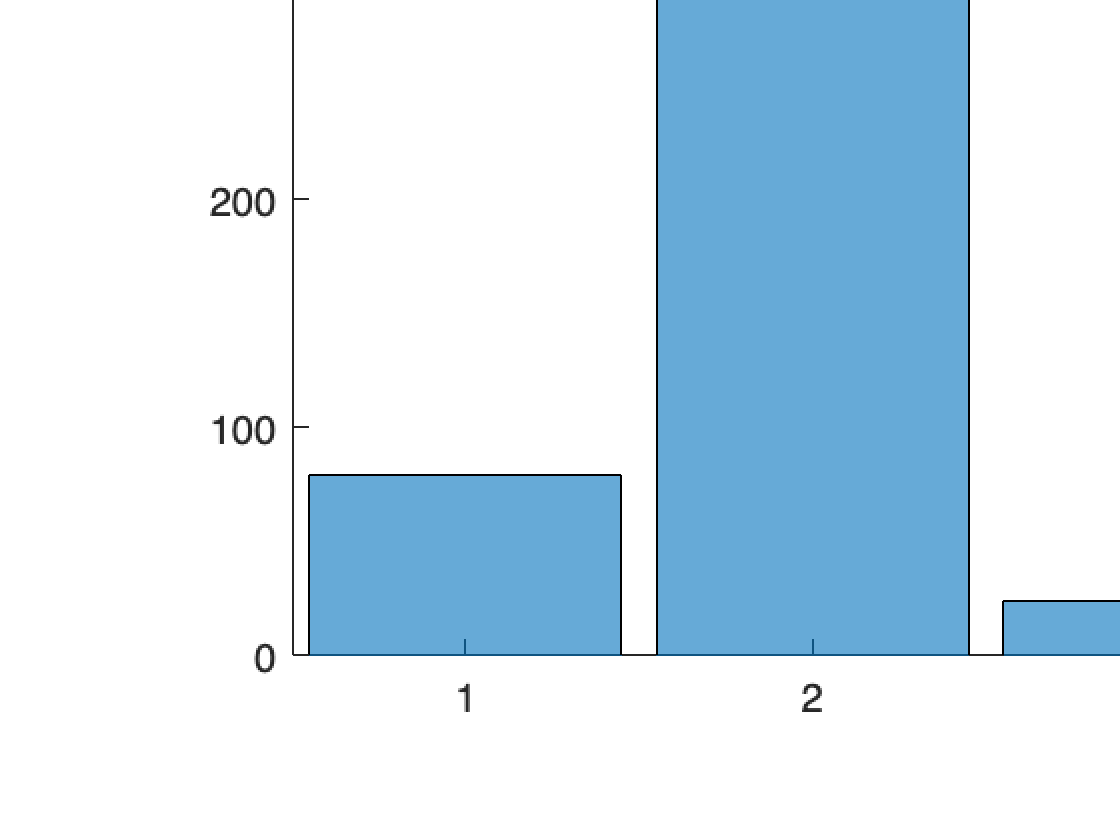

histogram(C2.Job)
title('Job')


summary(C2(:,"CitySize"))

Variables:

    CitySize: 759×1 categorical

        Values:

            1      166   
            2      239   
            3      354   



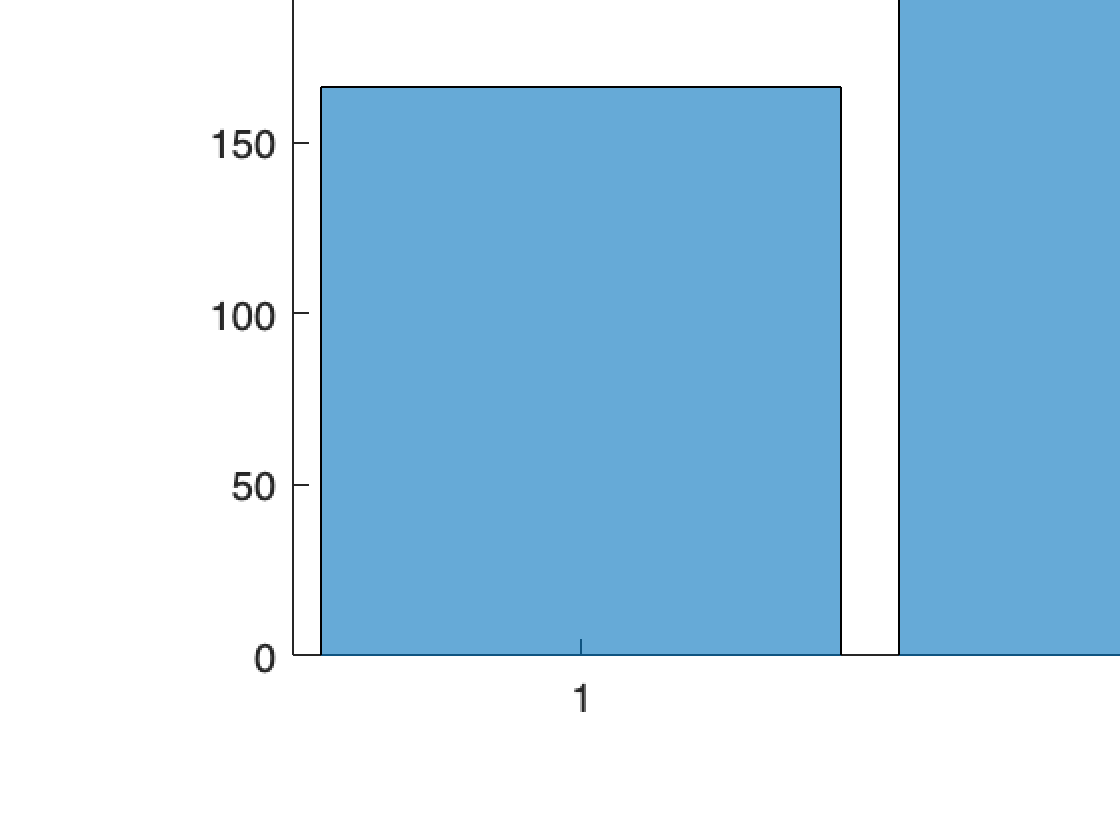

histogram(C2.CitySize)
title('City Size')



summary(C2(:,"Area"))

Variables:

    Area: 759×1 categorical

        Values:

            1      590   
            2       97   
            3       72   



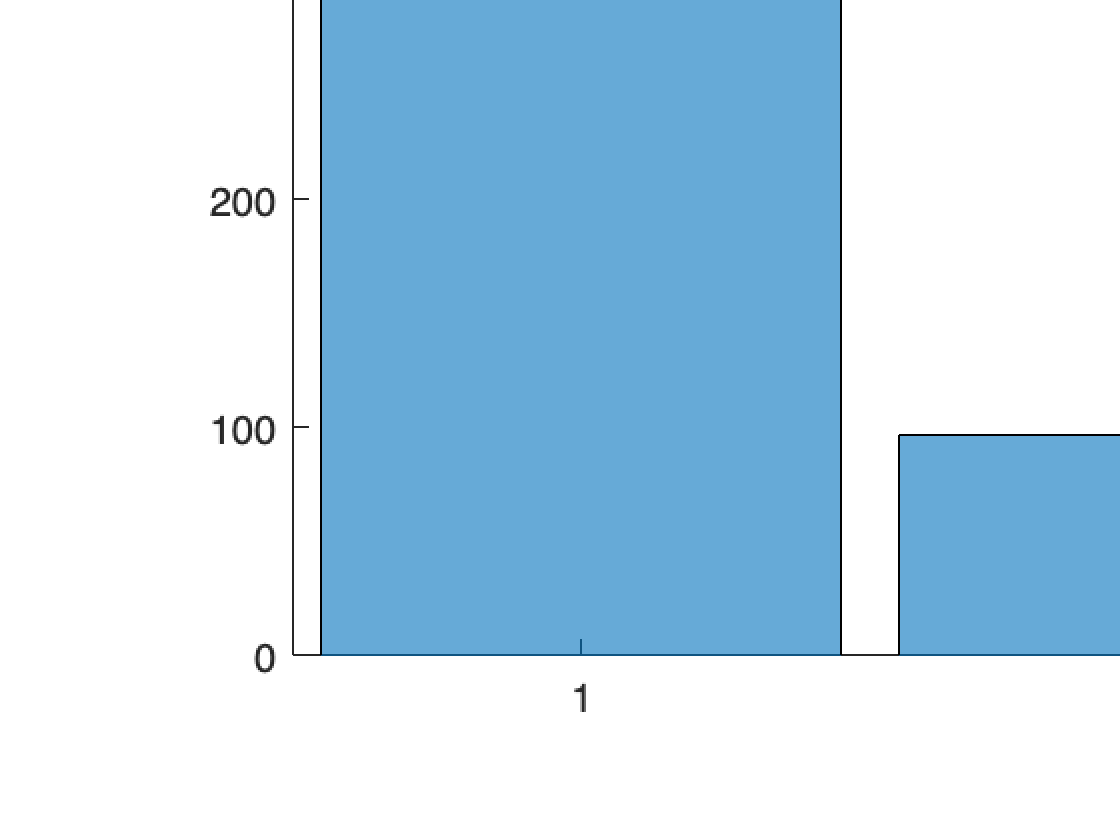

histogram(C2.Area)
title('Area')


summary(C2(:,"Investments"))

Variables:

    Investments: 759×1 categorical

        Values:

            1        0   
            2      759   
            3        0   



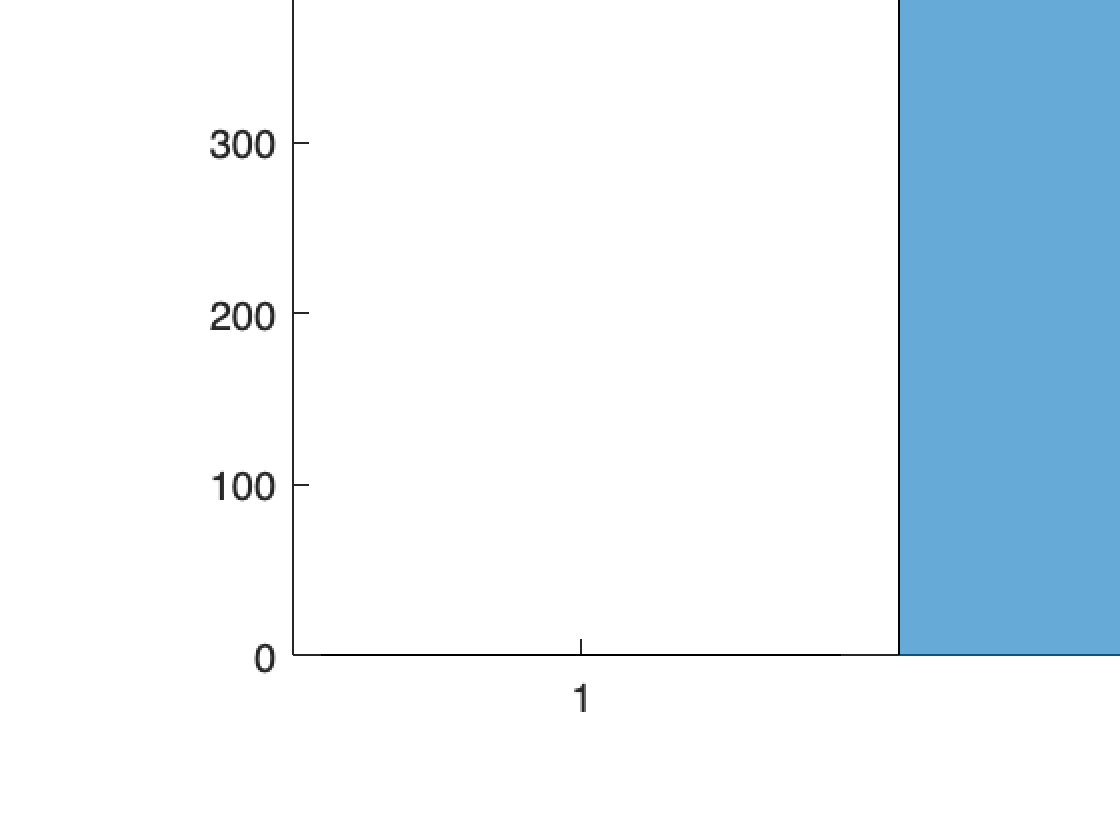

histogram(C2.Investments)
title(['Investments'])



summary(C2(:, "Income"))

Variables:

    Income: 759×1 double

        Values:

            Min       0.083995
            Median     0.71533
            Max        0.97725



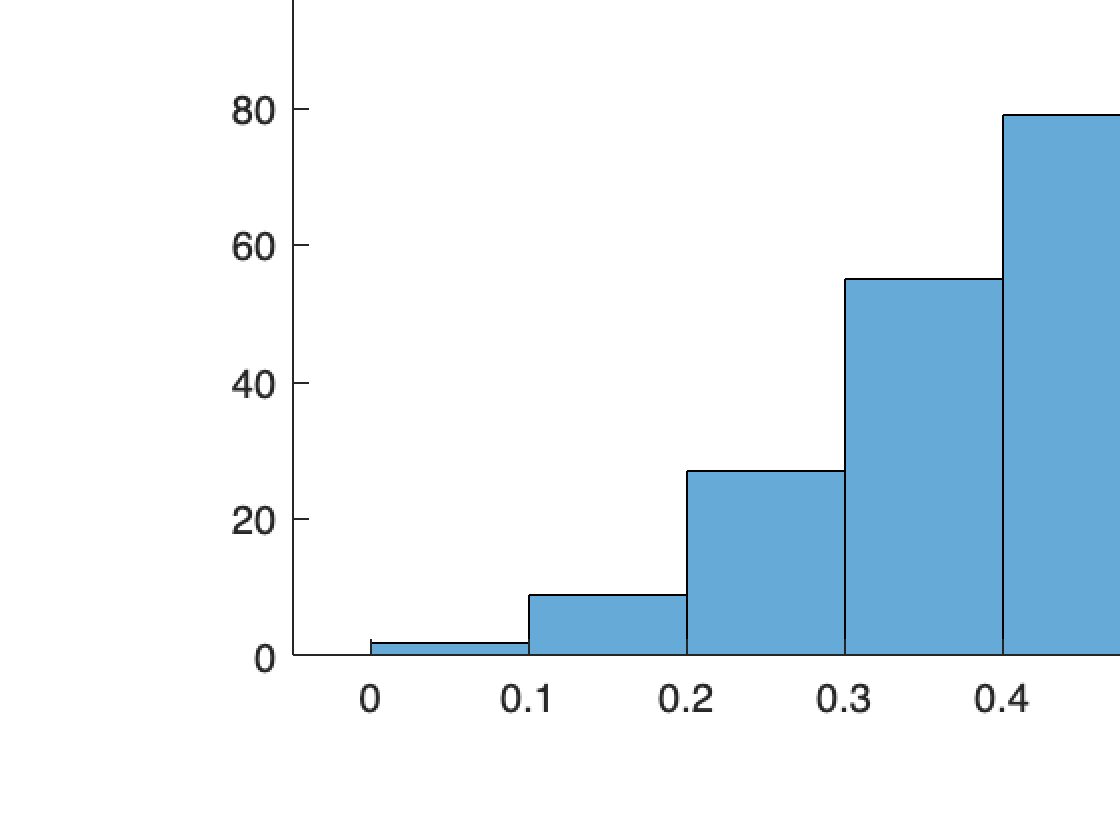

histogram(C2.Income)

mean(C2.Income)

ans = 0.6736


summary(C2(:, "Wealth"))

Variables:

    Wealth: 759×1 double

        Values:

            Min       0.059355
            Median     0.71513
            Max        0.99544



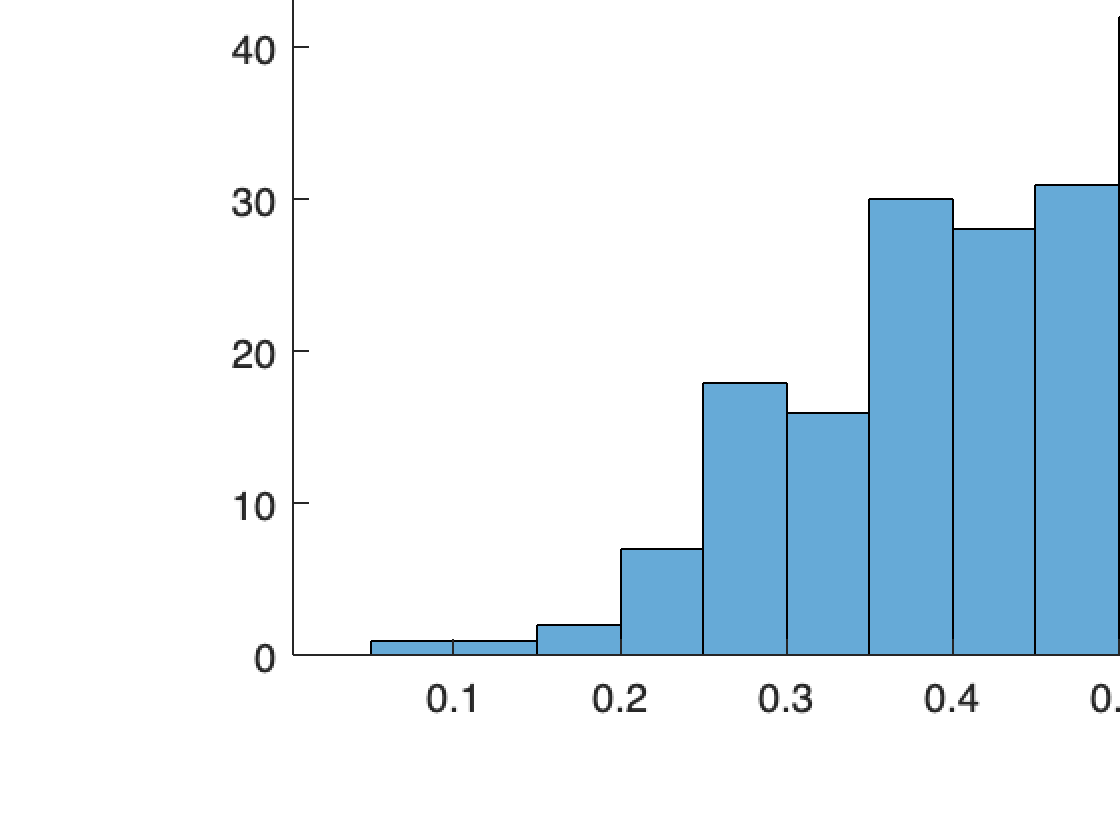

histogram(C2.Wealth)

mean(C2.Wealth)

ans = 0.6875


summary(C2(:, "Debt"))

Variables:

    Debt: 759×1 double

        Values:

            Min       0.014591
            Median     0.52083
            Max        0.96469



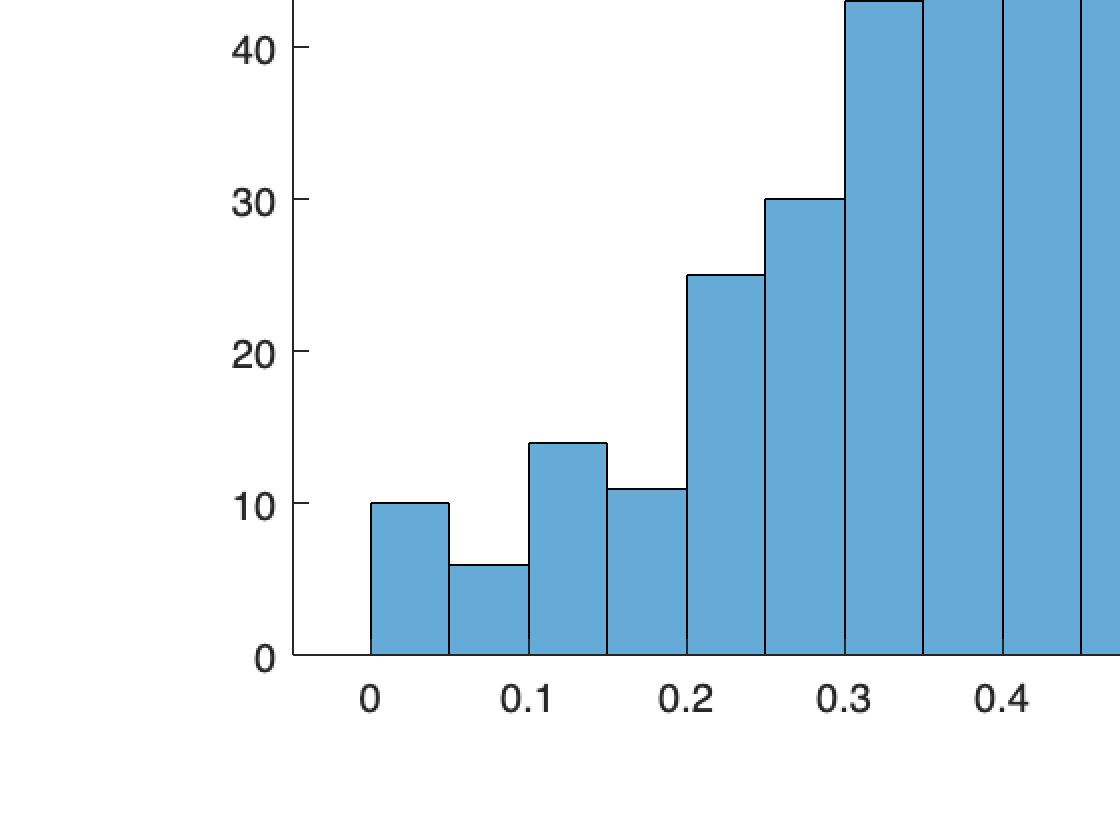

histogram(C2.Debt)

mean(C2.Debt)

ans = 0.5138


summary(C2(:, "FinEdu"))

Variables:

    FinEdu: 759×1 double

        Values:

            Min       0.10138 
            Median    0.63705 
            Max       0.94471 



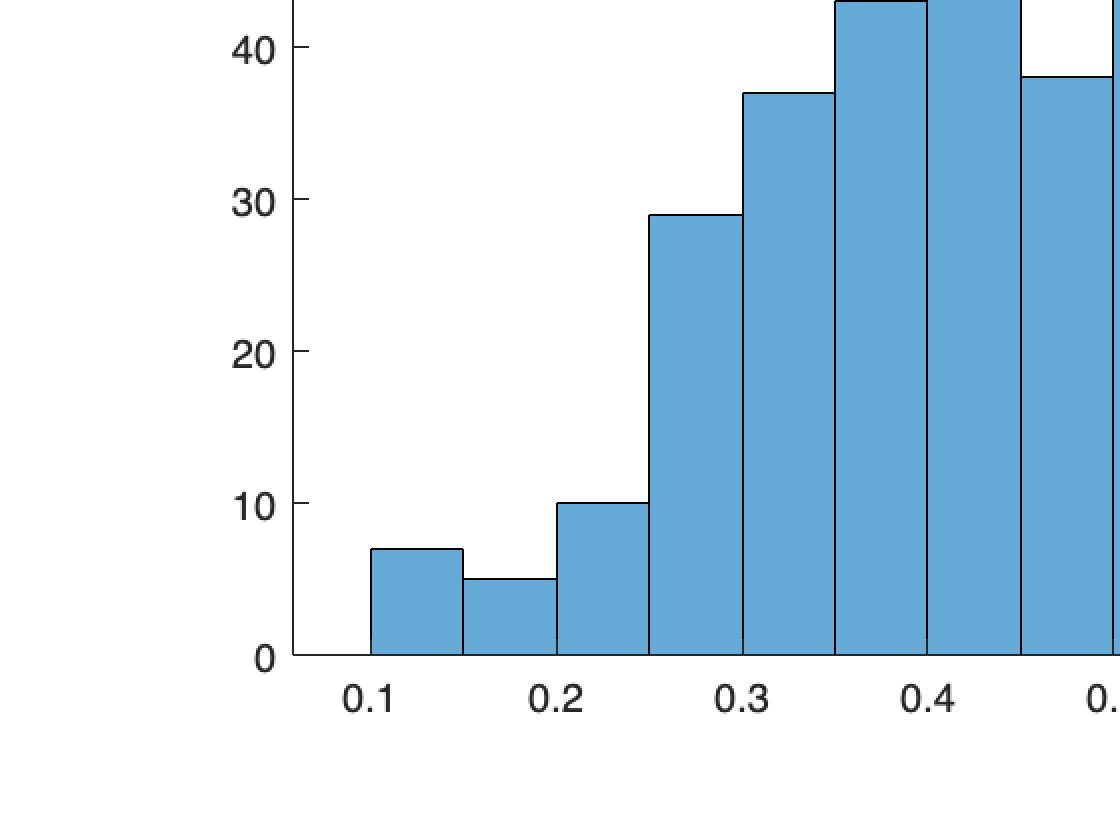

histogram(C2.FinEdu)

mean(C2.FinEdu)

ans = 0.6107


summary(C2(:, "ESG"))

Variables:

    ESG: 759×1 double

        Values:

            Min       0.043817
            Median     0.62418
            Max        0.97285



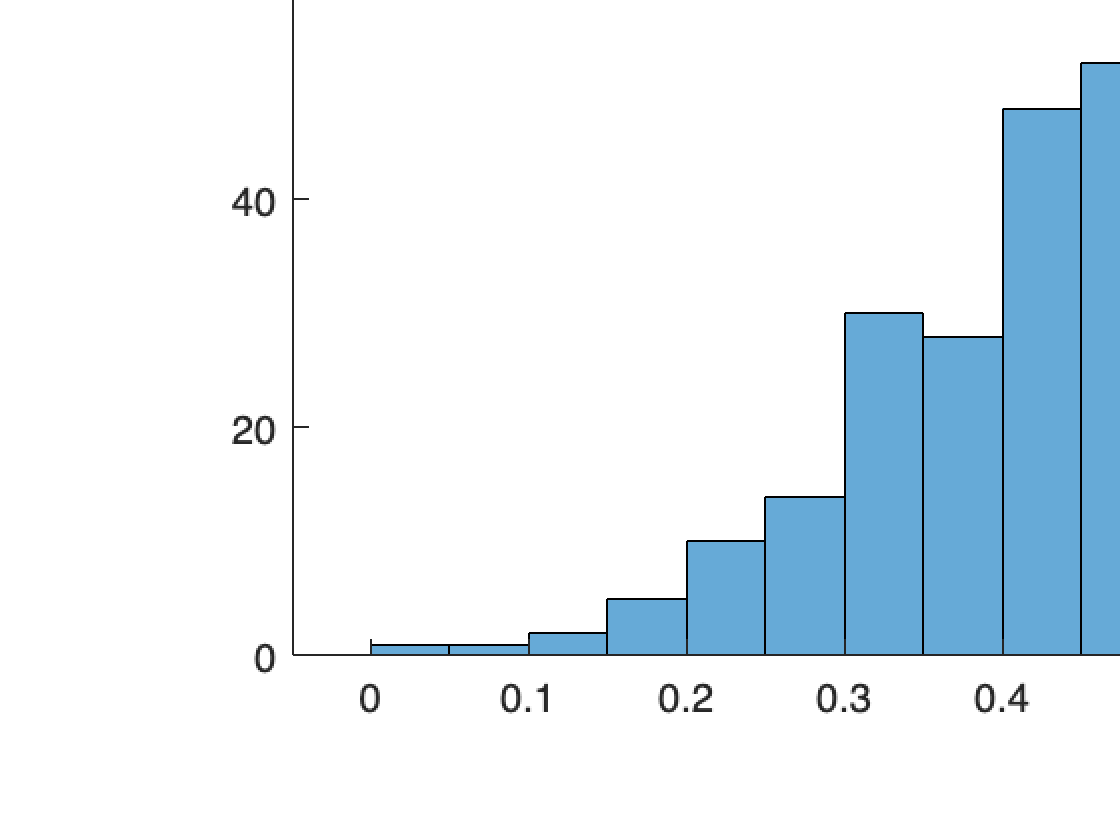

histogram(C2.ESG)

mean(C2.ESG)

ans = 0.6084


summary(C2(:, "Digital"))

Variables:

    Digital: 759×1 double

        Values:

            Min       0.033527
            Median     0.67413
            Max        0.96225



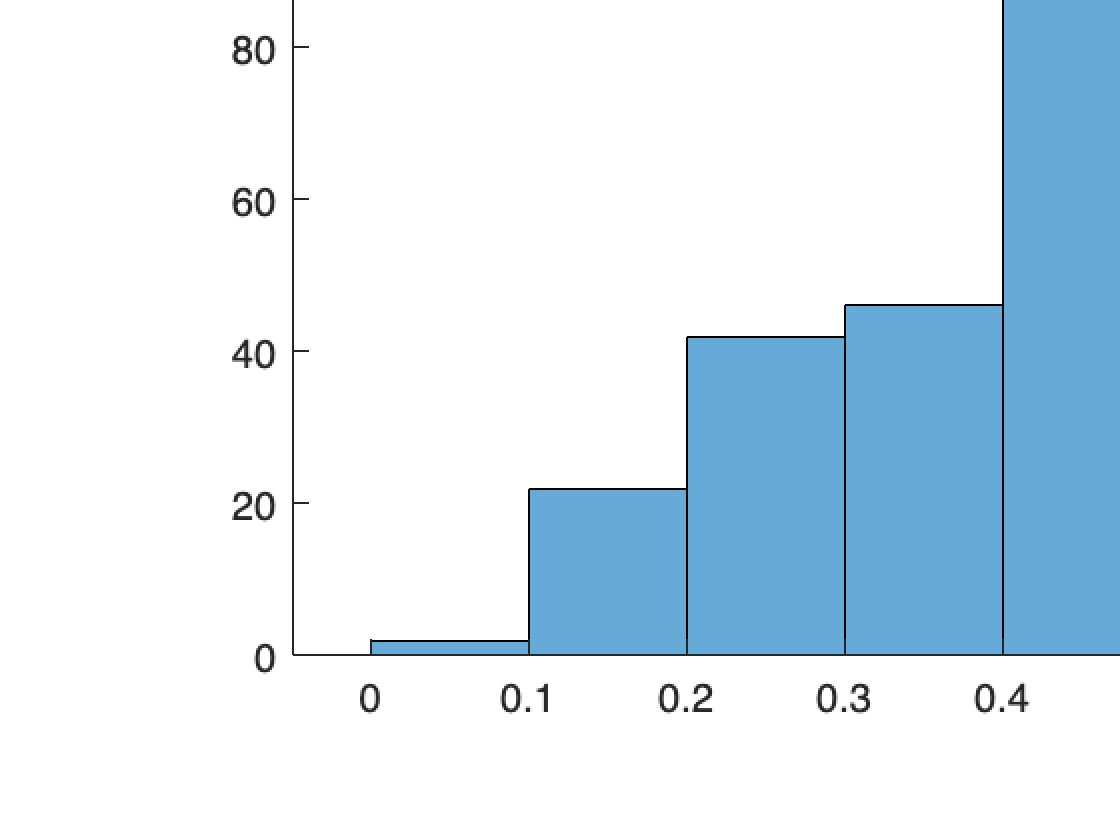

histogram(C2.Digital)

mean(C2.Digital)

ans = 0.6349


summary(C2(:, "BankFriend"))

Variables:

    BankFriend: 759×1 double

        Values:

            Min        0.2055 
            Median    0.70577 
            Max       0.97213 



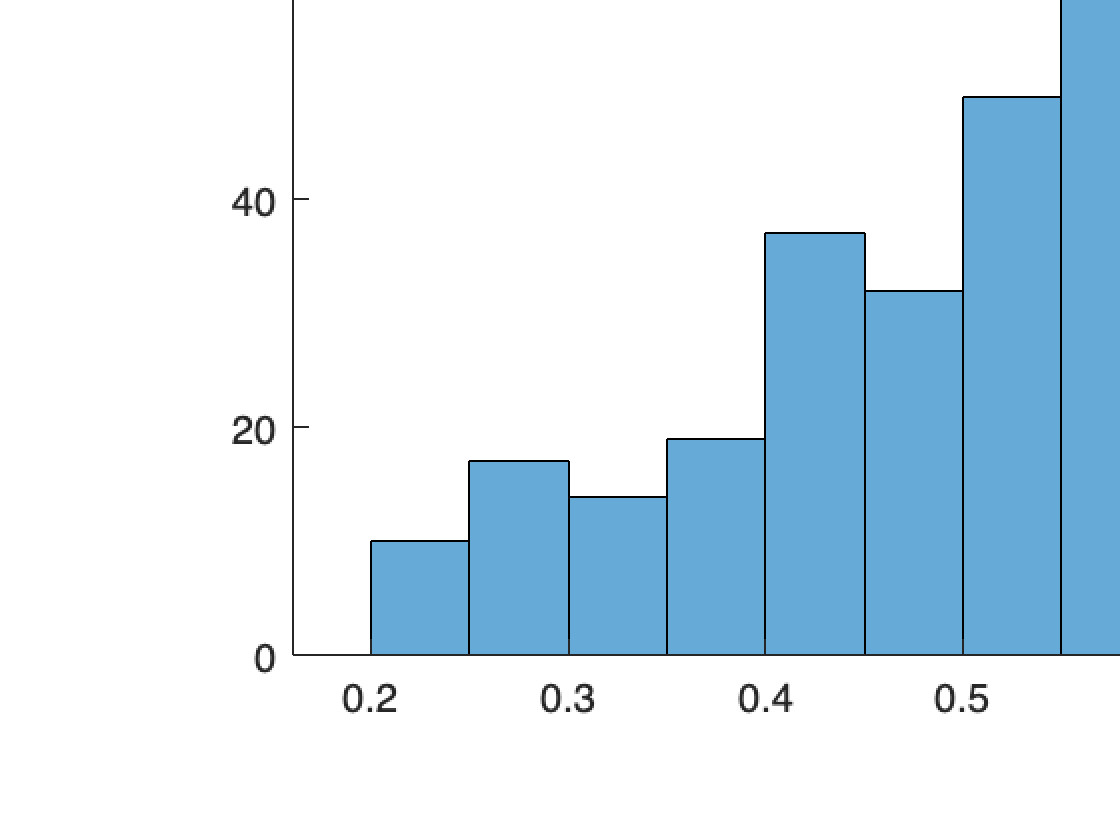

histogram(C2.BankFriend)

mean(C2.BankFriend)

ans = 0.6704


summary(C2(:, "LifeStyle"))

Variables:

    LifeStyle: 759×1 double

        Values:

            Min       0.014093
            Median     0.59178
            Max        0.97101



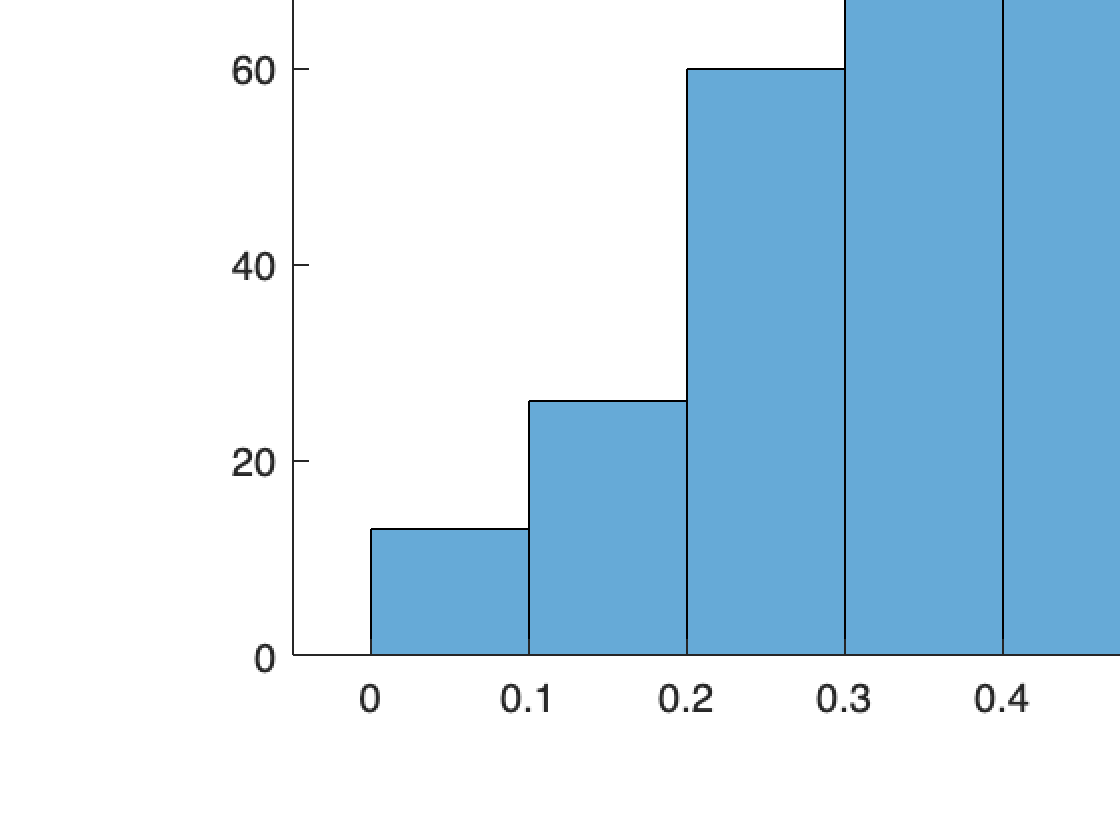

histogram(C2.LifeStyle)

mean(C2.LifeStyle)

ans = 0.5698


summary(C2(:, "Luxury"))

Variables:

    Luxury: 759×1 double

        Values:

            Min       0.087593
            Median     0.64872
            Max        0.99348



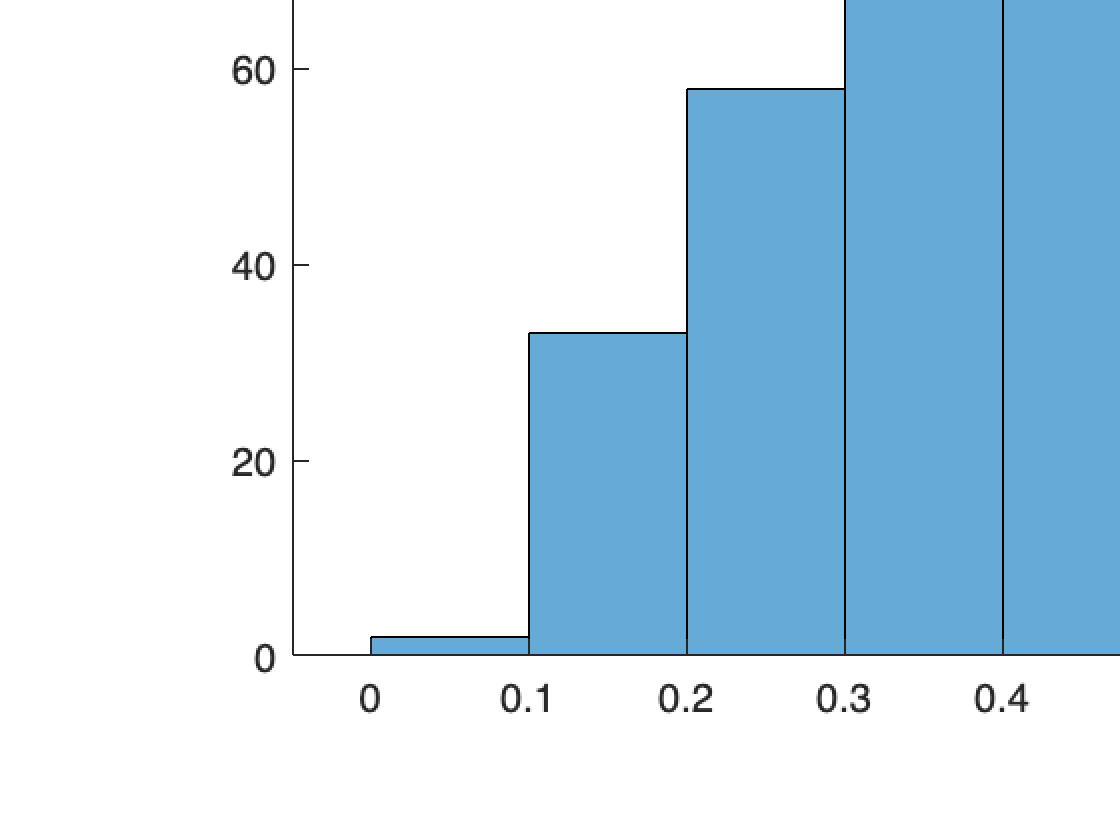

histogram(C2.Luxury)

mean(C2.Luxury)

ans = 0.6155


summary(C2(:, "Saving"))

Variables:

    Saving: 759×1 double

        Values:

            Min       0.0097008
            Median       0.5778
            Max         0.96553



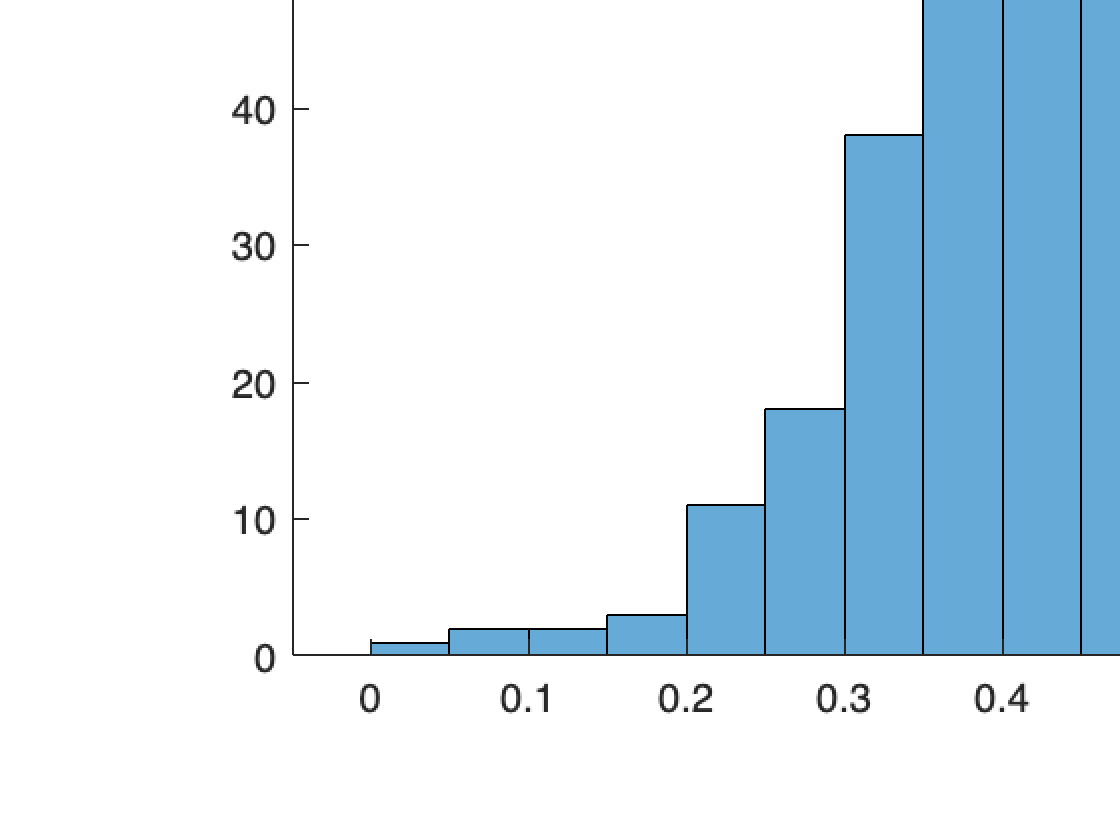

histogram(C2.Saving)

mean(C2.Saving)

ans = 0.5683

C3 = BankClients(T6==3,:);

% Frequency tables
tabulate(C3.Job)

  Value    Count   Percent
      1      104     12.94%
      2      537     66.79%
      3       17      2.11%
      4        9      1.12%
      5      137     17.04%


tabulate(C3.Area)

  Value    Count   Percent
      1      583     72.51%
      2      130     16.17%
      3       91     11.32%


tabulate(C3.CitySize)

  Value    Count   Percent
      1      348     43.28%
      2      343     42.66%
      3      113     14.05%


tabulate(C3.Investments)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3      804    100.00%



summary(C3(:,"Age"))

Variables:

    Age: 804×1 double

        Values:

            Min          66   
            Median       82   
            Max          95   



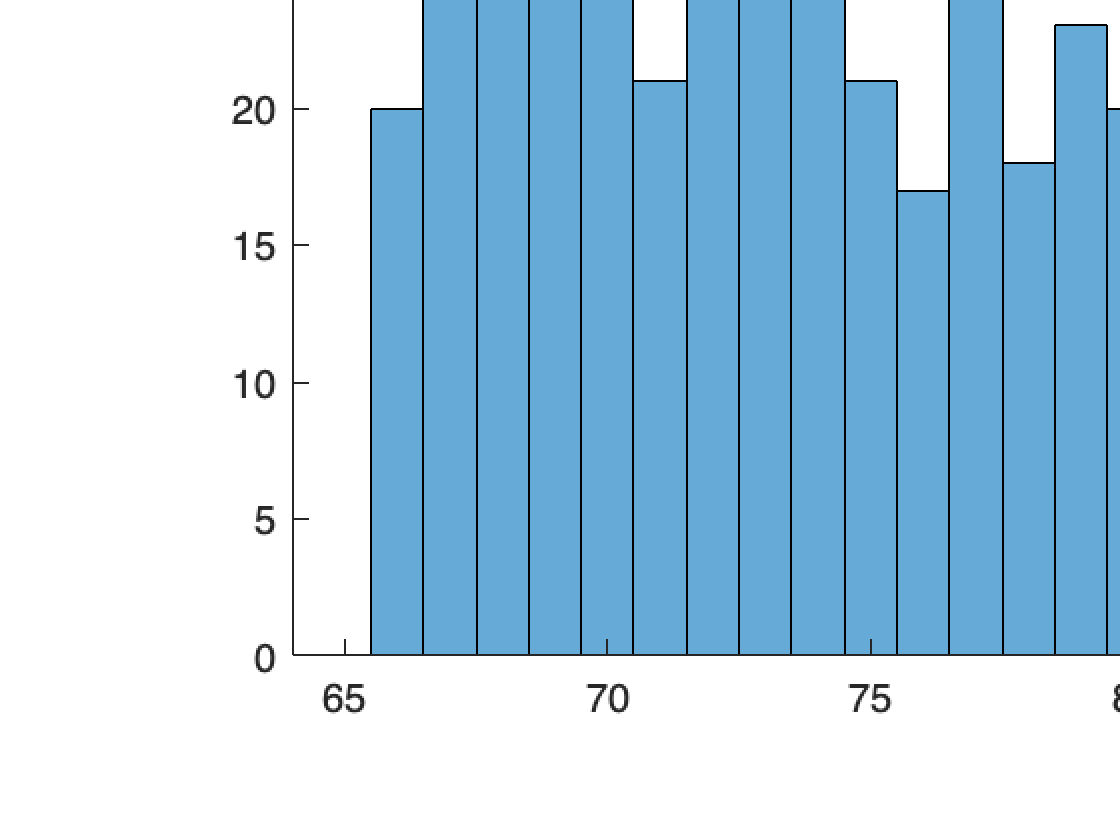

histogram(C3.Age)
title('Age')

mean(C3.Age)

ans = 81.3433


summary(C3(:,"Job"))

Variables:

    Job: 804×1 categorical

        Values:

            1      104   
            2      537   
            3       17   
            4        9   
            5      137   



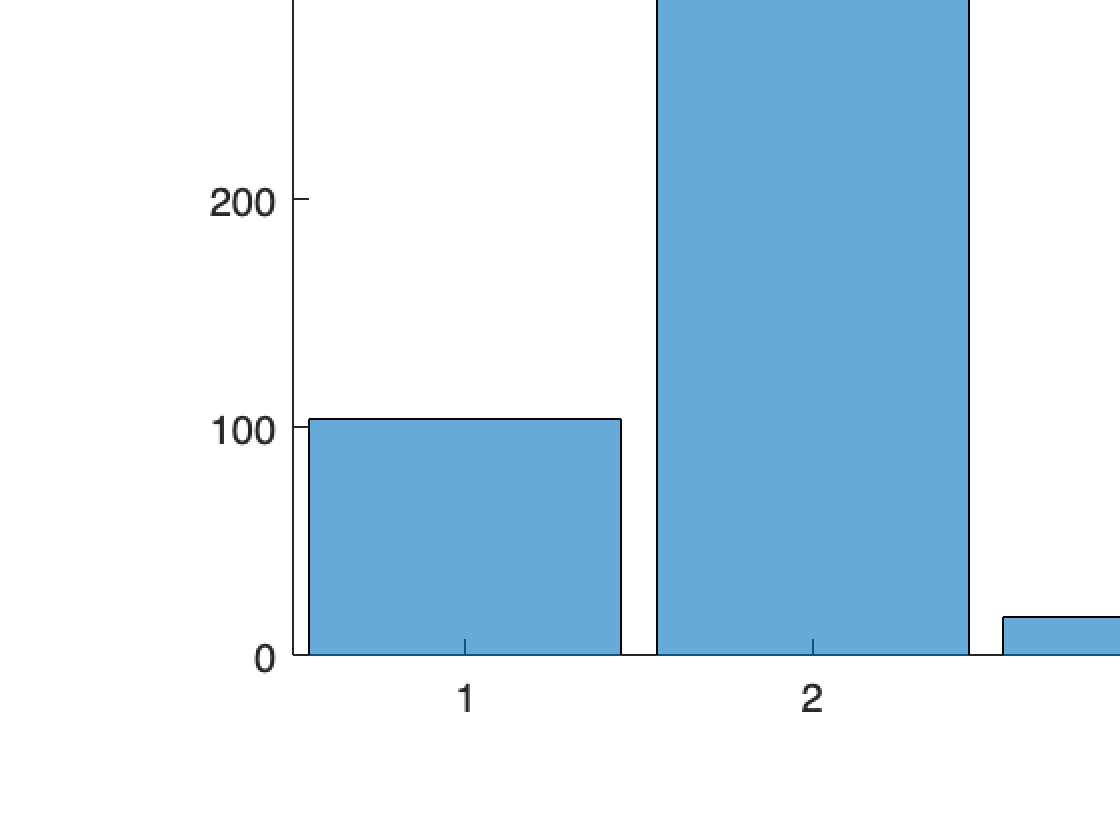

histogram(C3.Job)
title('Job')


summary(C3(:,"CitySize"))

Variables:

    CitySize: 804×1 categorical

        Values:

            1      348   
            2      343   
            3      113   



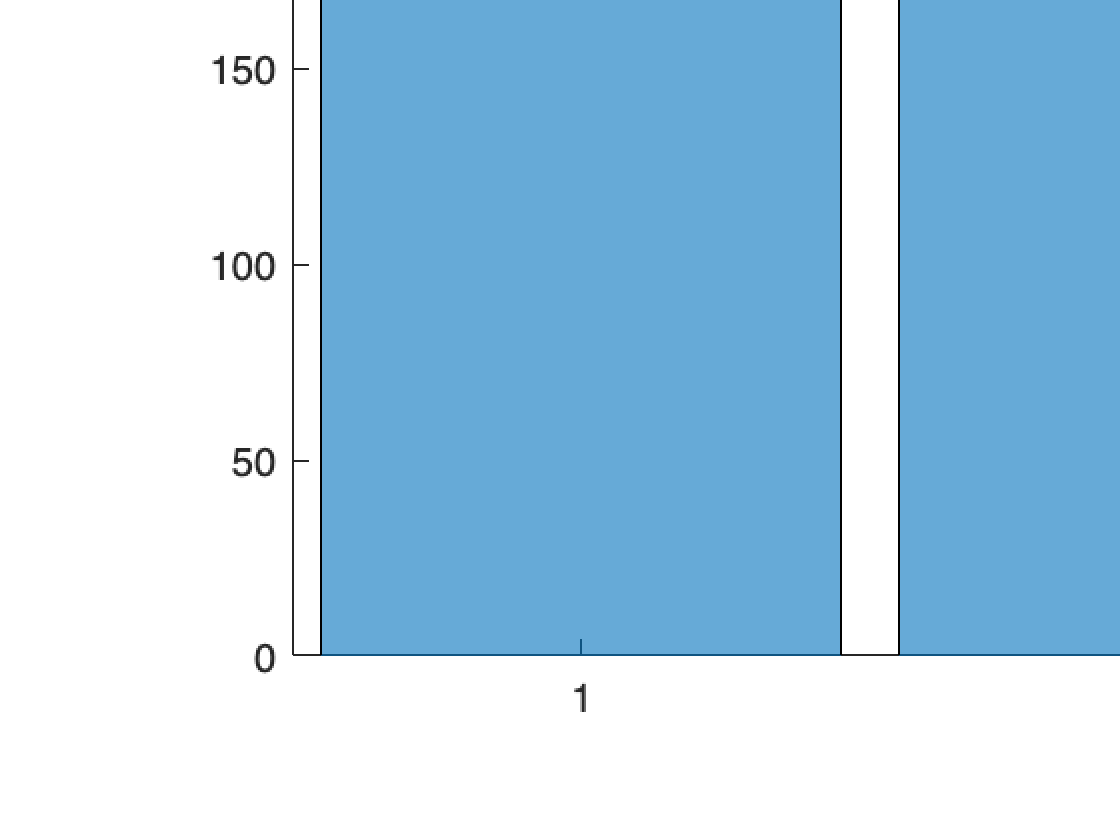

histogram(C3.CitySize)
title('City Size')



summary(C3(:,"Area"))

Variables:

    Area: 804×1 categorical

        Values:

            1      583   
            2      130   
            3       91   



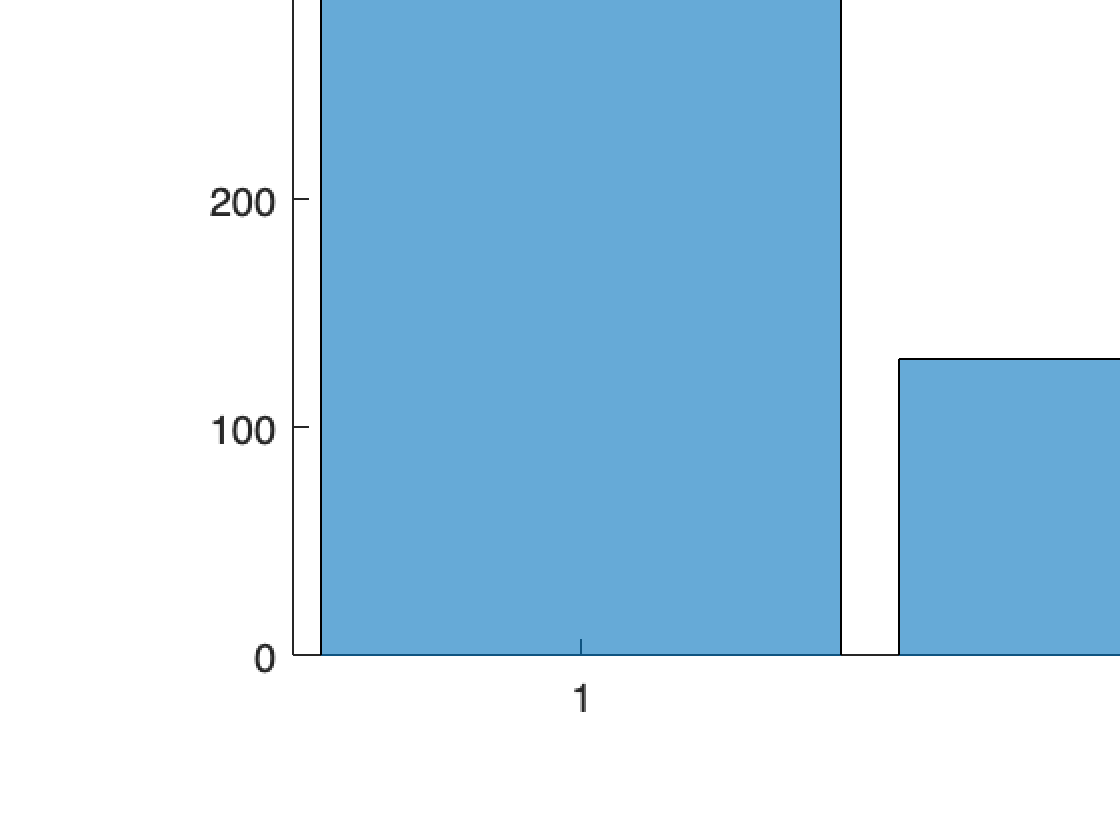

histogram(C3.Area)
title('Area')


summary(C3(:,"Investments"))

Variables:

    Investments: 804×1 categorical

        Values:

            1        0   
            2        0   
            3      804   



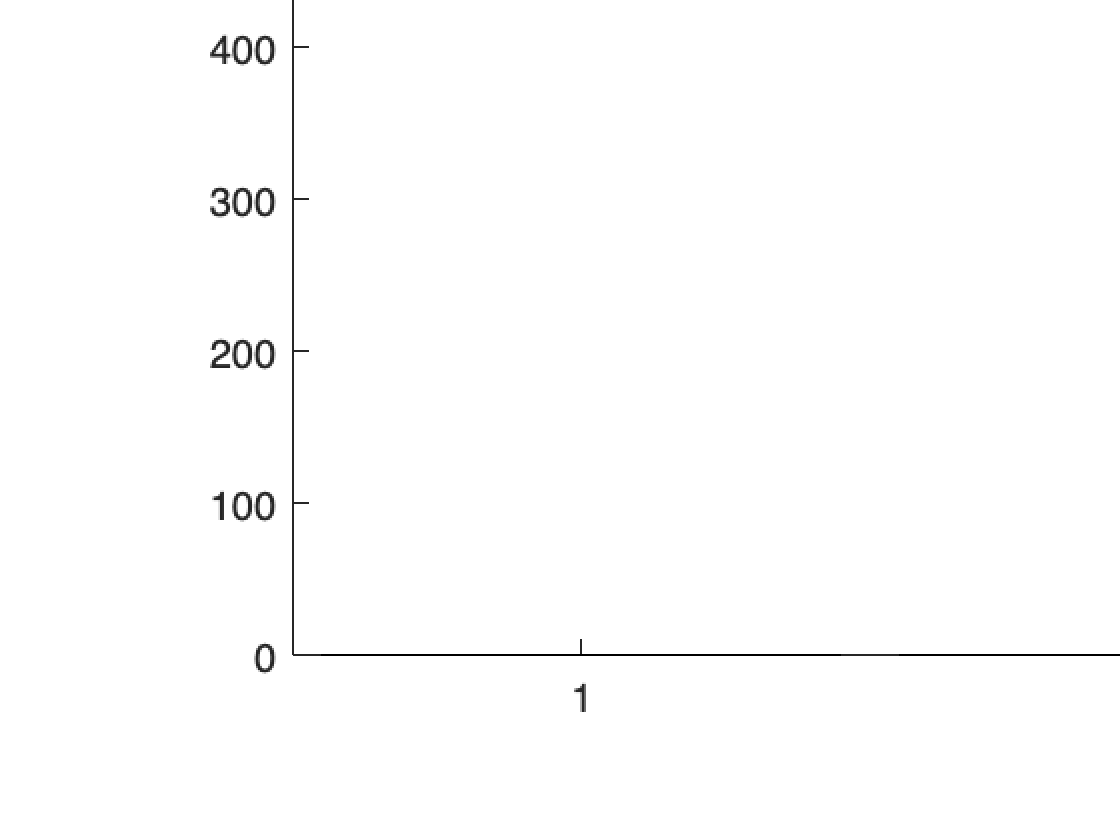

histogram(C3.Investments)
title(['Investments'])


summary(C3(:, "Income"))

Variables:

    Income: 804×1 double

        Values:

            Min       0.066275
            Median      0.5527
            Max        0.97144



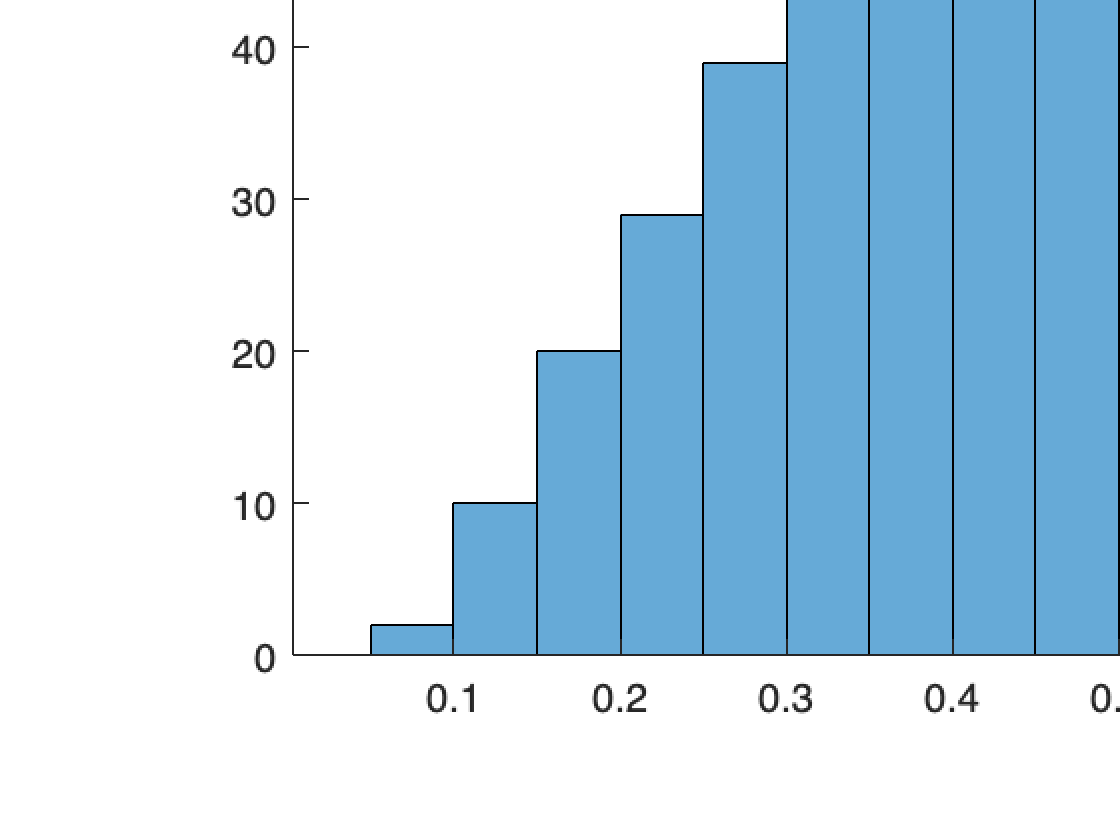

histogram(C3.Income)

mean(C3.Income)

ans = 0.5475


summary(C3(:, "Wealth"))

Variables:

    Wealth: 804×1 double

        Values:

            Min             0 
            Median    0.56082 
            Max       0.99315 



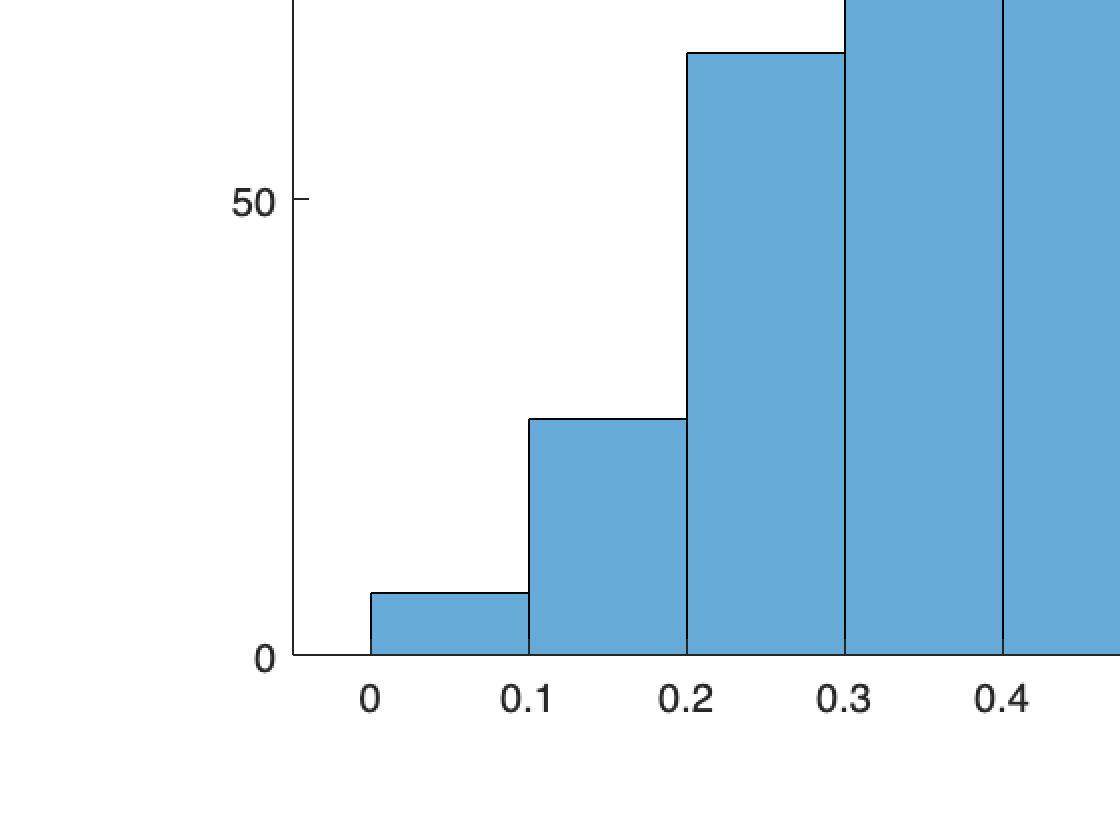

histogram(C3.Wealth)

mean(C3.Wealth)

ans = 0.5487


summary(C3(:, "Debt"))

Variables:

    Debt: 804×1 double

        Values:

            Min             0 
            Median    0.44735 
            Max       0.93163 



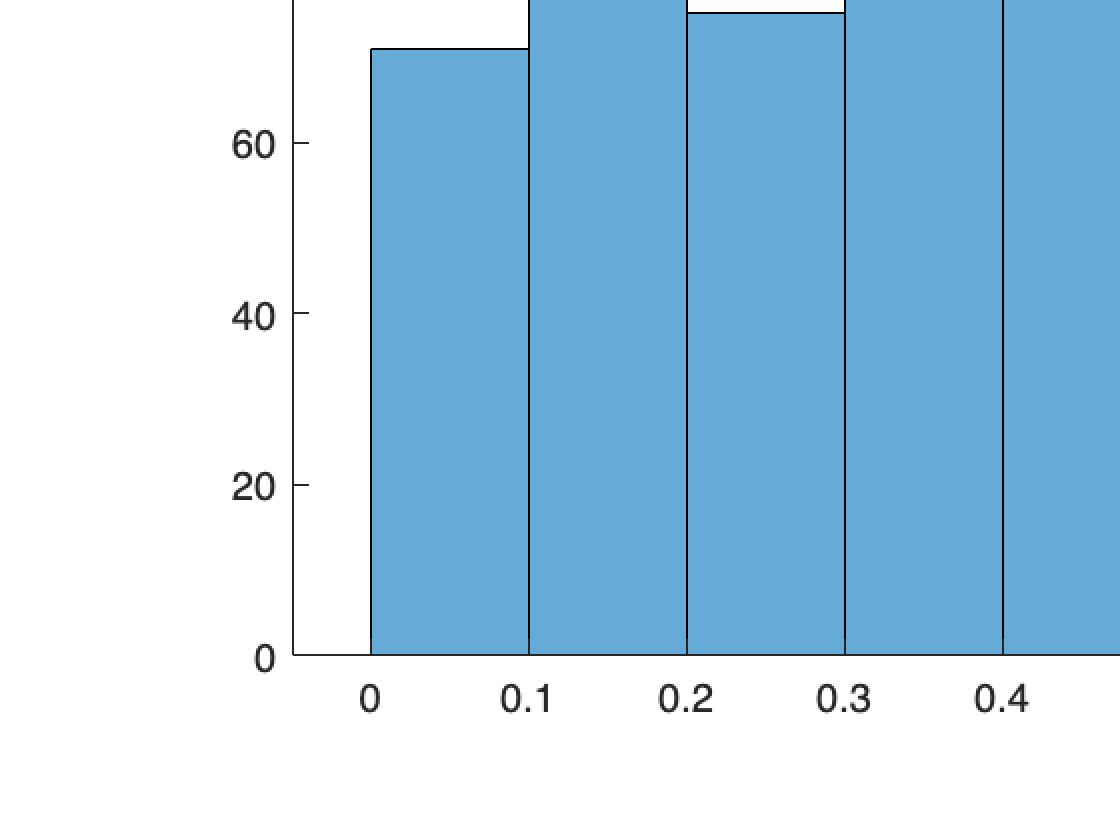

histogram(C3.Debt)

mean(C3.Debt)

ans = 0.4295


summary(C3(:, "FinEdu"))

Variables:

    FinEdu: 804×1 double

        Values:

            Min       0.061388
            Median     0.46638
            Max        0.90165



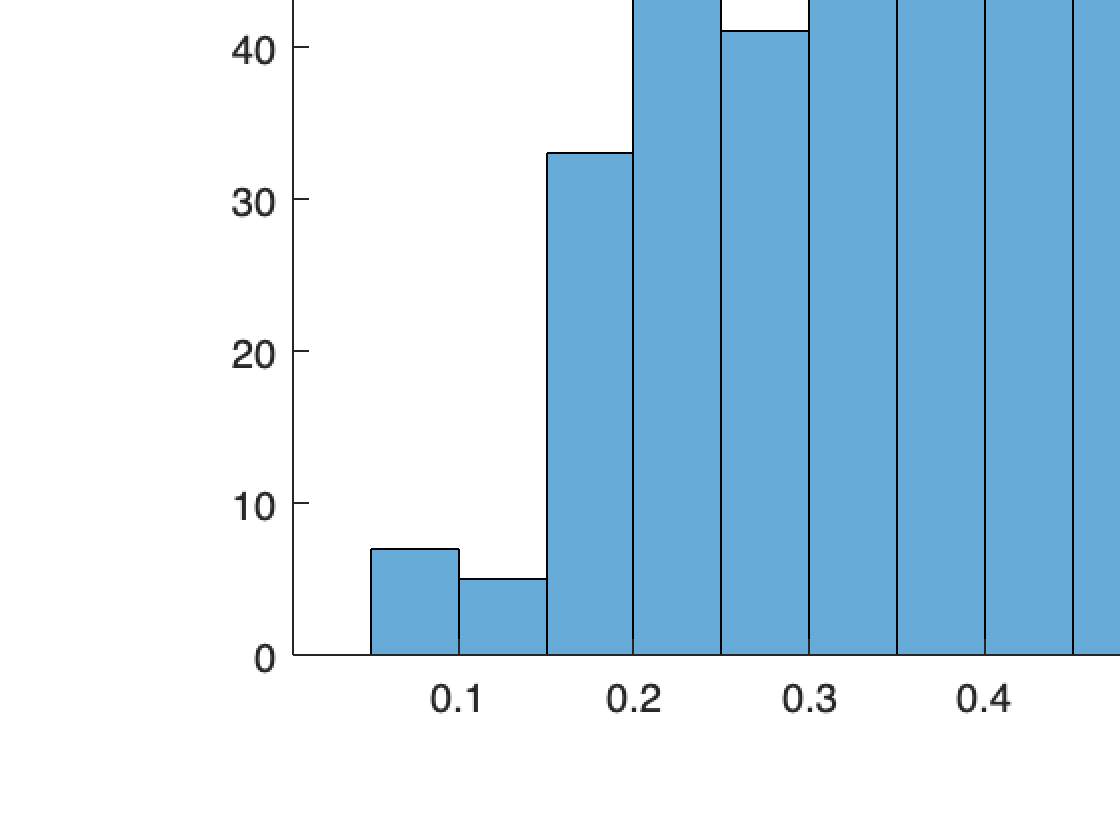

histogram(C3.FinEdu)

mean(C3.FinEdu)

ans = 0.4680


summary(C3(:, "ESG"))

Variables:

    ESG: 804×1 double

        Values:

            Min       0.14503 
            Median    0.56232 
            Max       0.95376 



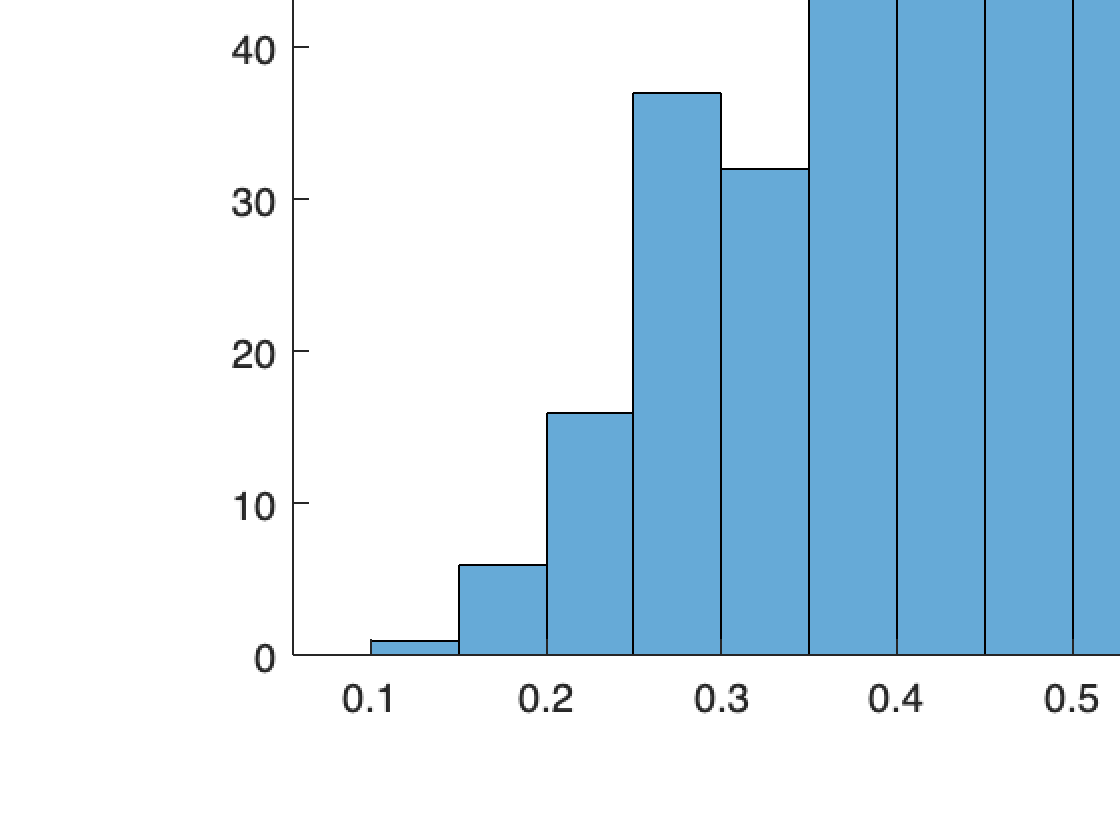

histogram(C3.ESG)

mean(C3.ESG)

ans = 0.5562


summary(C3(:, "Digital"))

Variables:

    Digital: 804×1 double

        Values:

            Min             0 
            Median     0.4747 
            Max       0.96011 



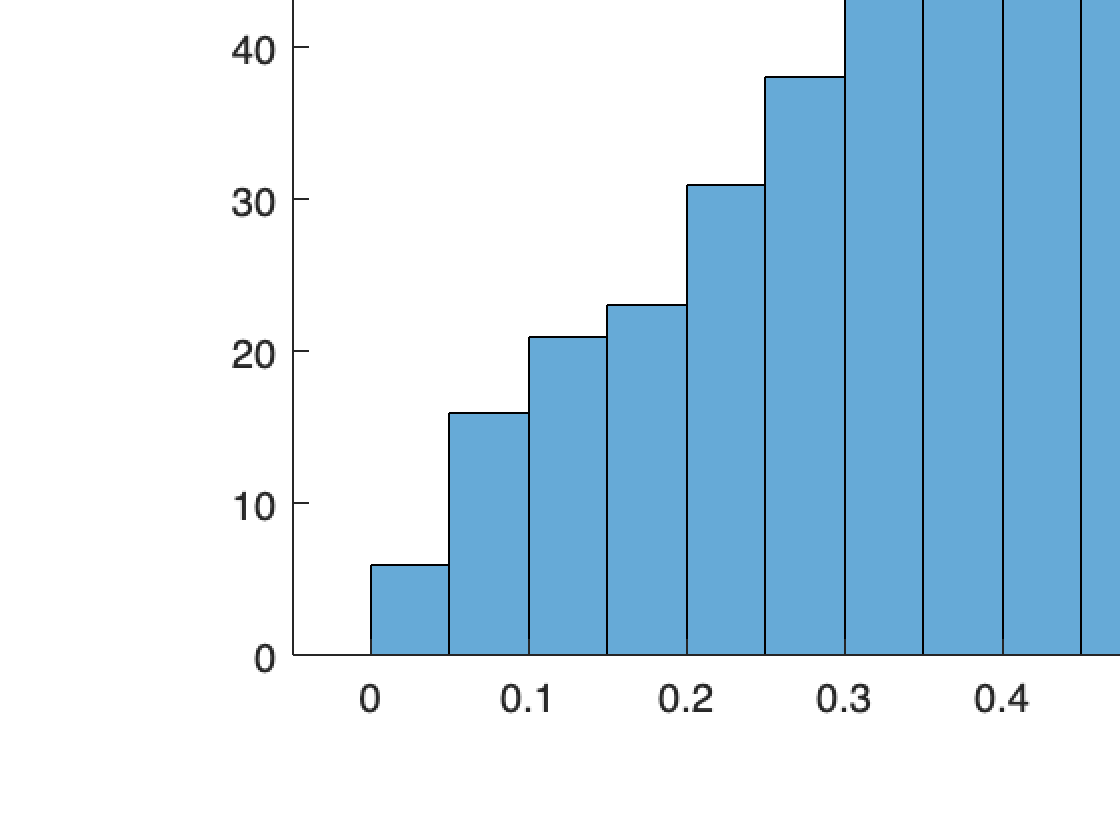

histogram(C3.Digital)

mean(C3.Digital)

ans = 0.4738


summary(C3(:, "BankFriend"))

Variables:

    BankFriend: 804×1 double

        Values:

            Min       0.13104 
            Median    0.60392 
            Max       0.95548 



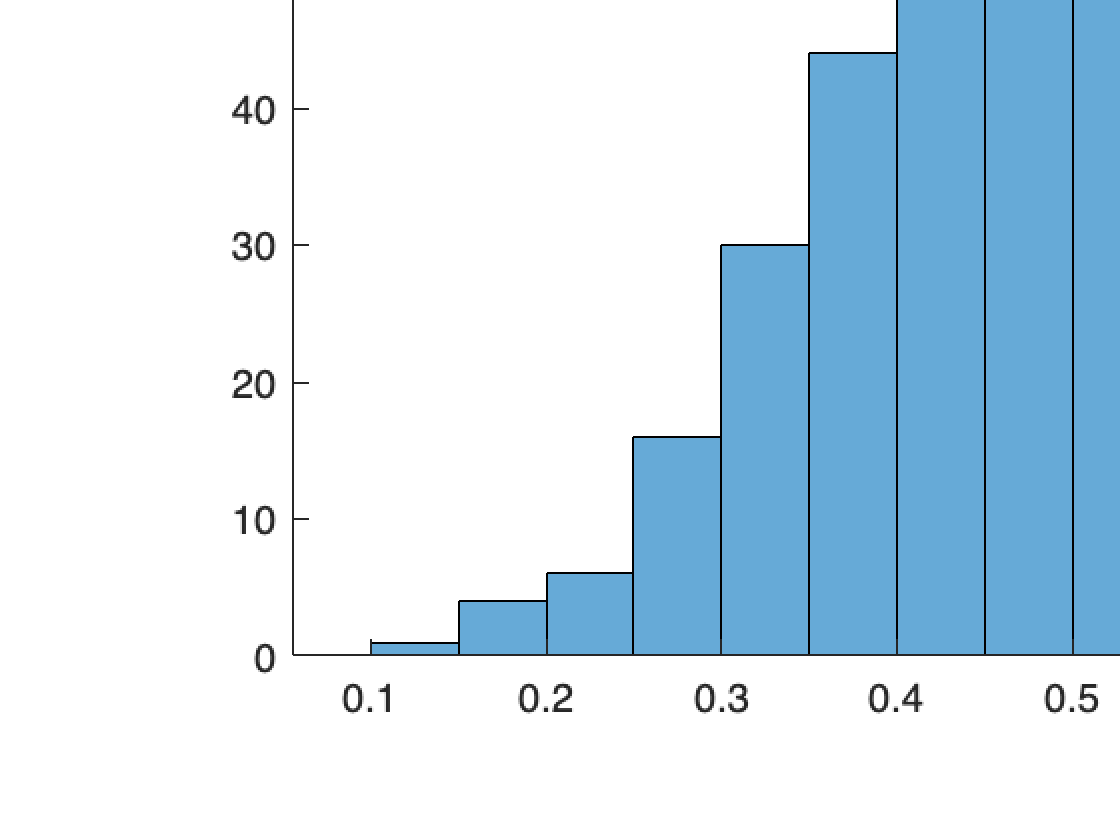

histogram(C3.BankFriend)

mean(C3.BankFriend)

ans = 0.5948


summary(C3(:, "LifeStyle"))

Variables:

    LifeStyle: 804×1 double

        Values:

            Min             0 
            Median    0.38941 
            Max       0.94076 



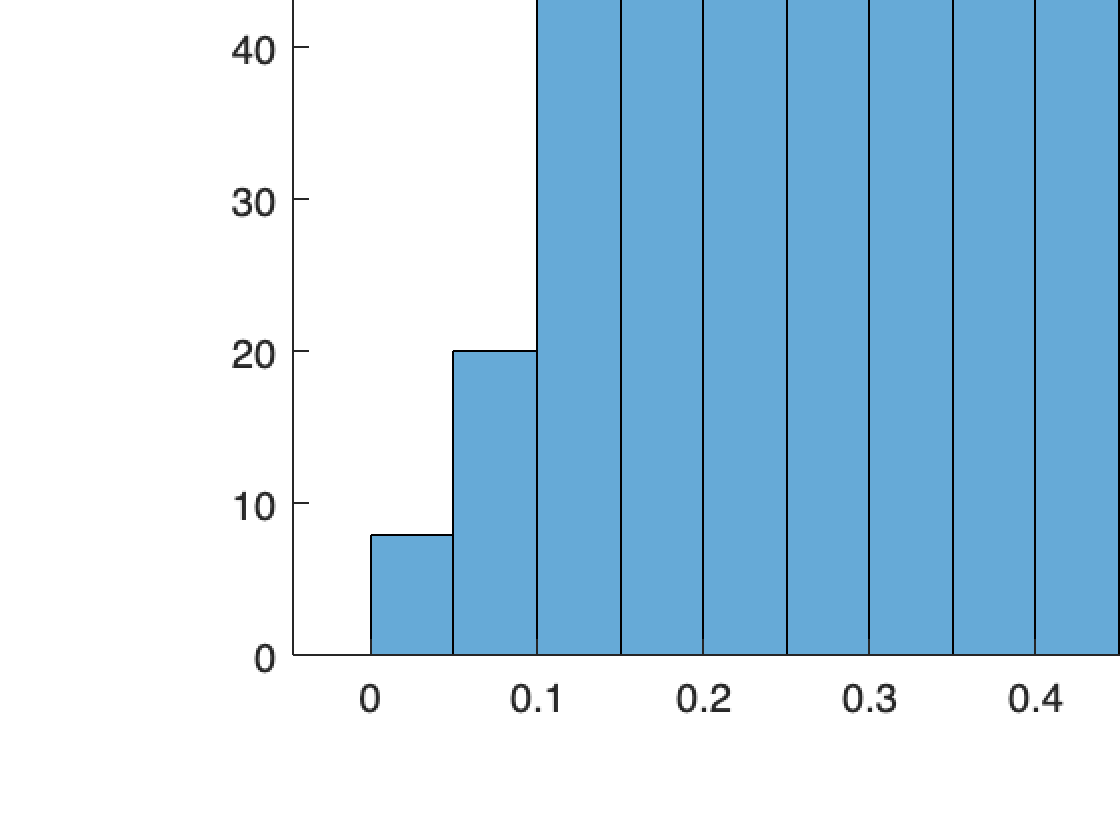

histogram(C3.LifeStyle)

mean(C3.LifeStyle)

ans = 0.4068


summary(C3(:, "Luxury"))

Variables:

    Luxury: 804×1 double

        Values:

            Min             0 
            Median    0.37677 
            Max       0.95914 



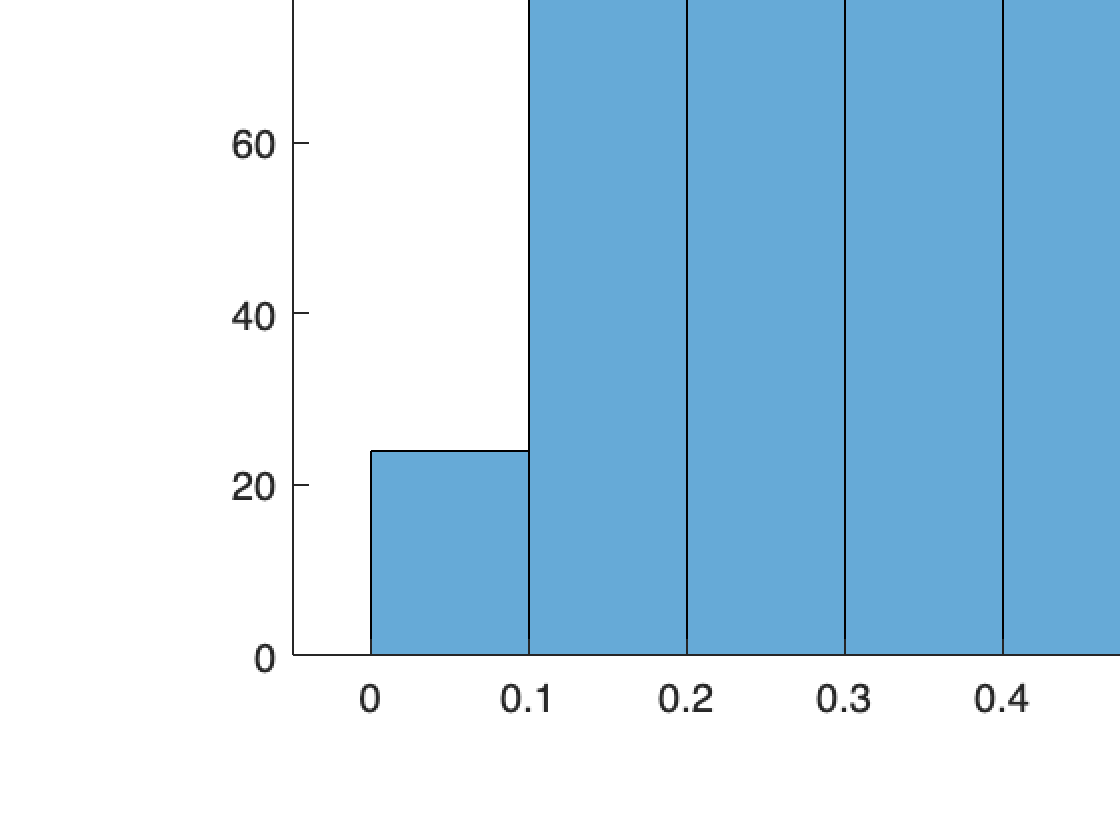

histogram(C3.Luxury)

mean(C3.Luxury)

ans = 0.4121


summary(C3(:, "Saving"))

Variables:

    Saving: 804×1 double

        Values:

            Min       0.037784
            Median     0.54205
            Max        0.93818



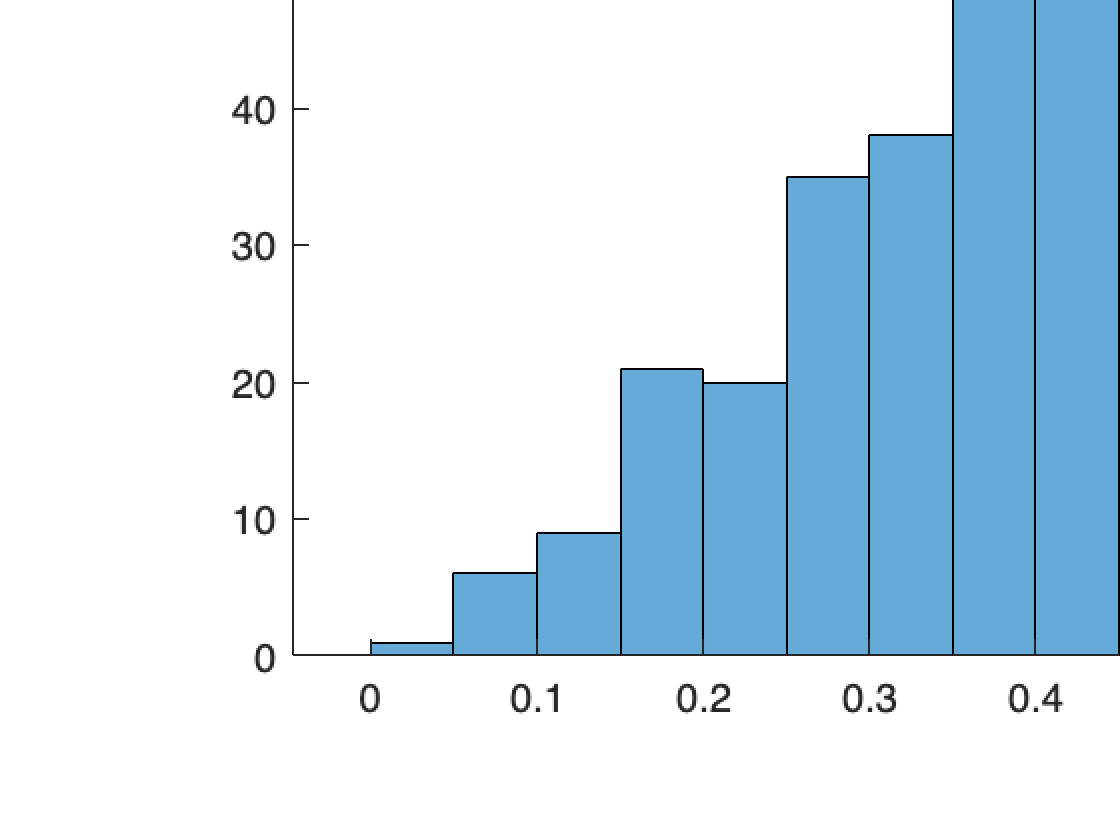

histogram(C3.Saving)

mean(C3.Saving)

ans = 0.5320

C4 = BankClients(T6==4,:);

% Frequency tables
tabulate(C4.Job)

  Value    Count   Percent
      1      107      7.72%
      2     1119     80.74%
      3       71      5.12%
      4       33      2.38%
      5       56      4.04%


tabulate(C4.Area)

  Value    Count   Percent
      1     1049     75.69%
      2      192     13.85%
      3      145     10.46%


tabulate(C4.CitySize)

  Value    Count   Percent
      1      356     25.69%
      2      548     39.54%
      3      482     34.78%


tabulate(C4.Investments)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3     1386    100.00%



summary(C4(:,"Age"))

Variables:

    Age: 1386×1 double

        Values:

            Min          19   
            Median       46   
            Max          66   



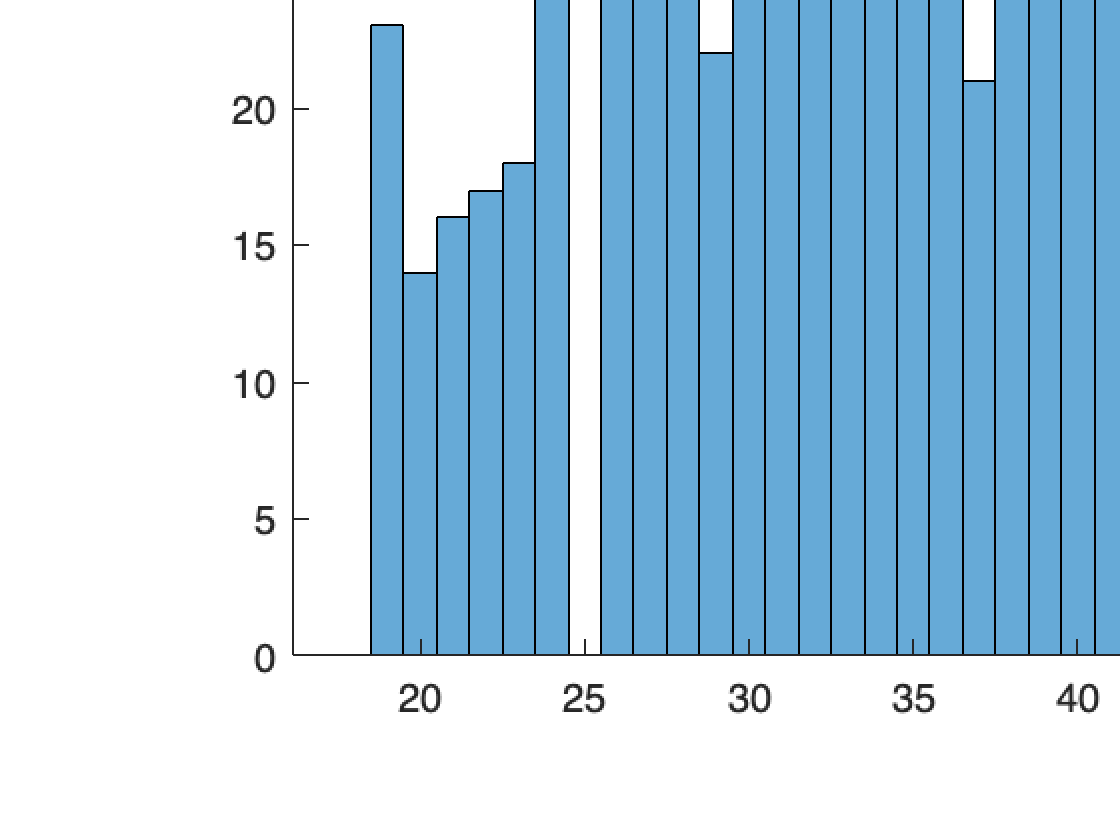

histogram(C4.Age)
title('Age')

mean(C4.Age)

ans = 44.3983


summary(C4(:,"Job"))

Variables:

    Job: 1386×1 categorical

        Values:

            1       107  
            2      1119  
            3        71  
            4        33  
            5        56  



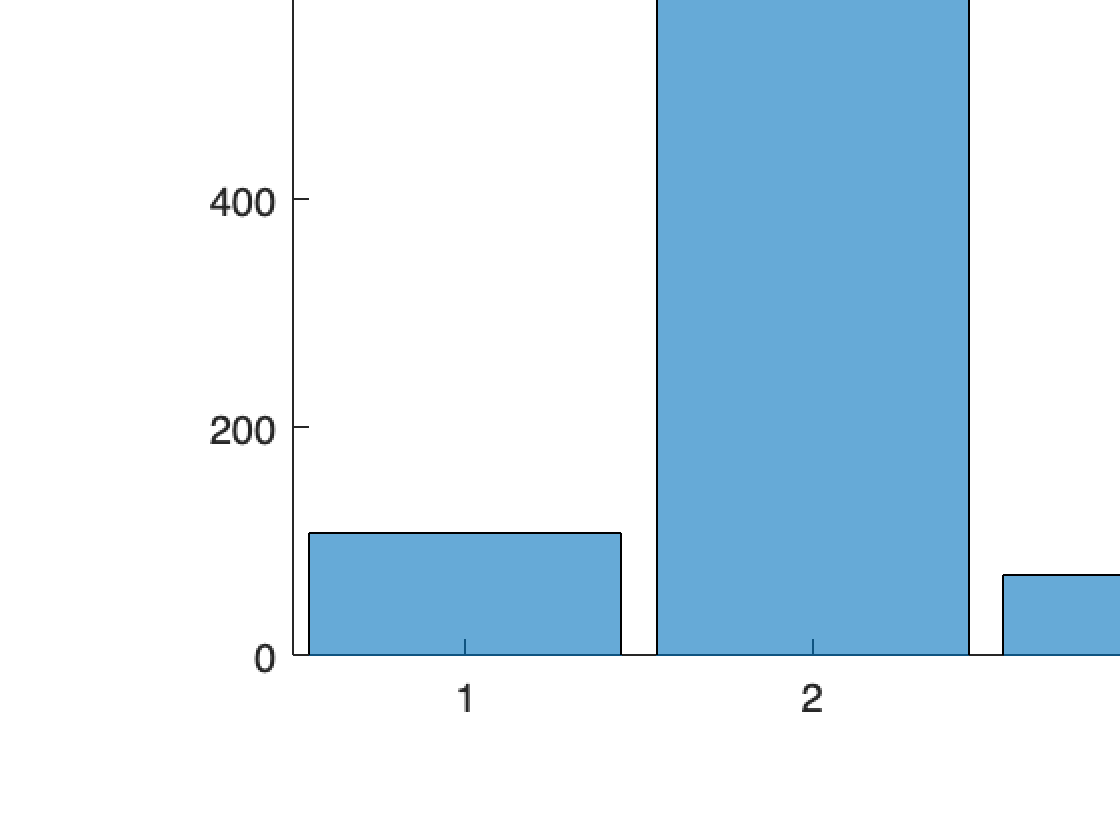

histogram(C4.Job)
title('Job')


summary(C4(:,"CitySize"))

Variables:

    CitySize: 1386×1 categorical

        Values:

            1      356   
            2      548   
            3      482   



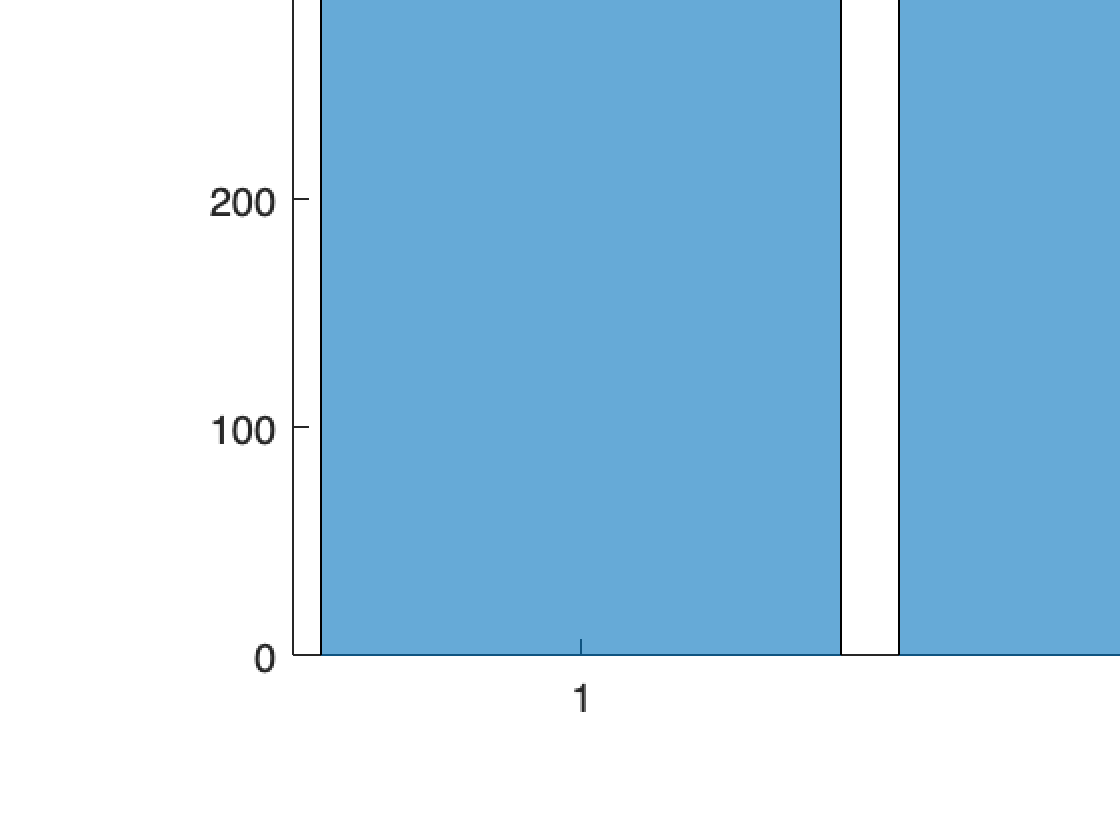

histogram(C4.CitySize)
title('City Size')



summary(C4(:,"Area"))

Variables:

    Area: 1386×1 categorical

        Values:

            1      1049  
            2       192  
            3       145  



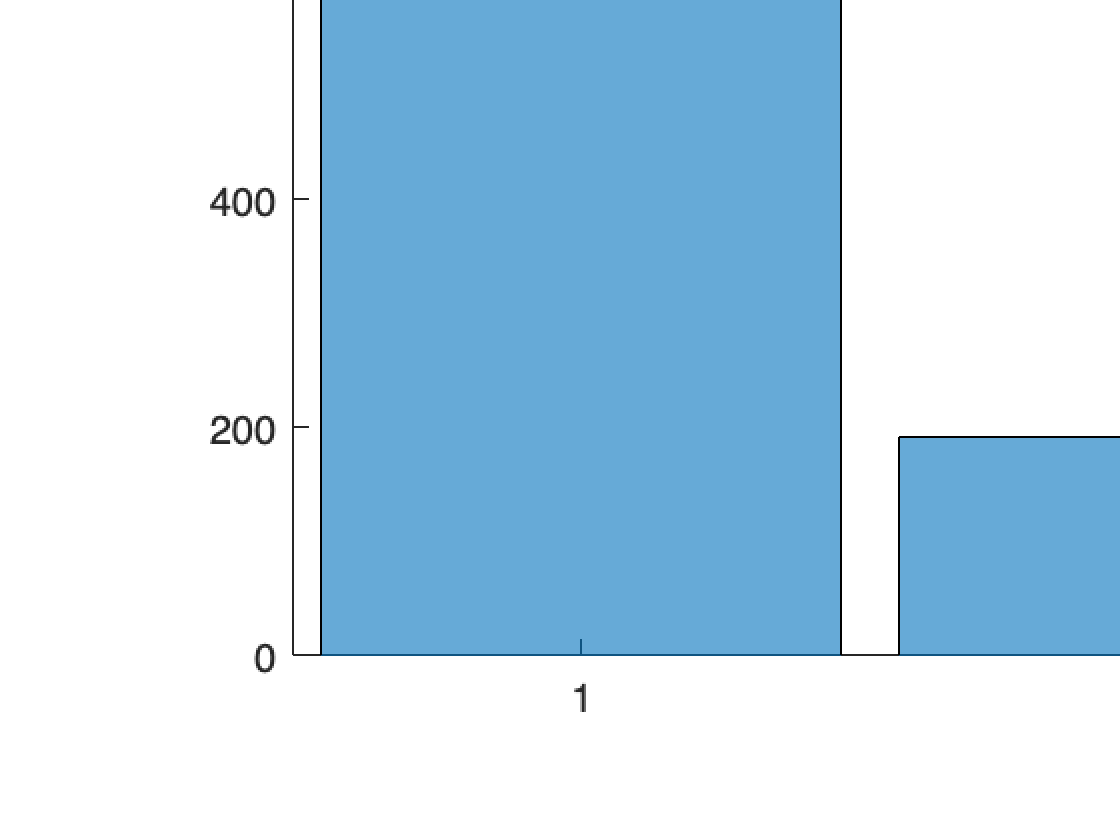

histogram(C4.Area)
title('Area')


summary(C4(:,"Investments"))

Variables:

    Investments: 1386×1 categorical

        Values:

            1         0  
            2         0  
            3      1386  



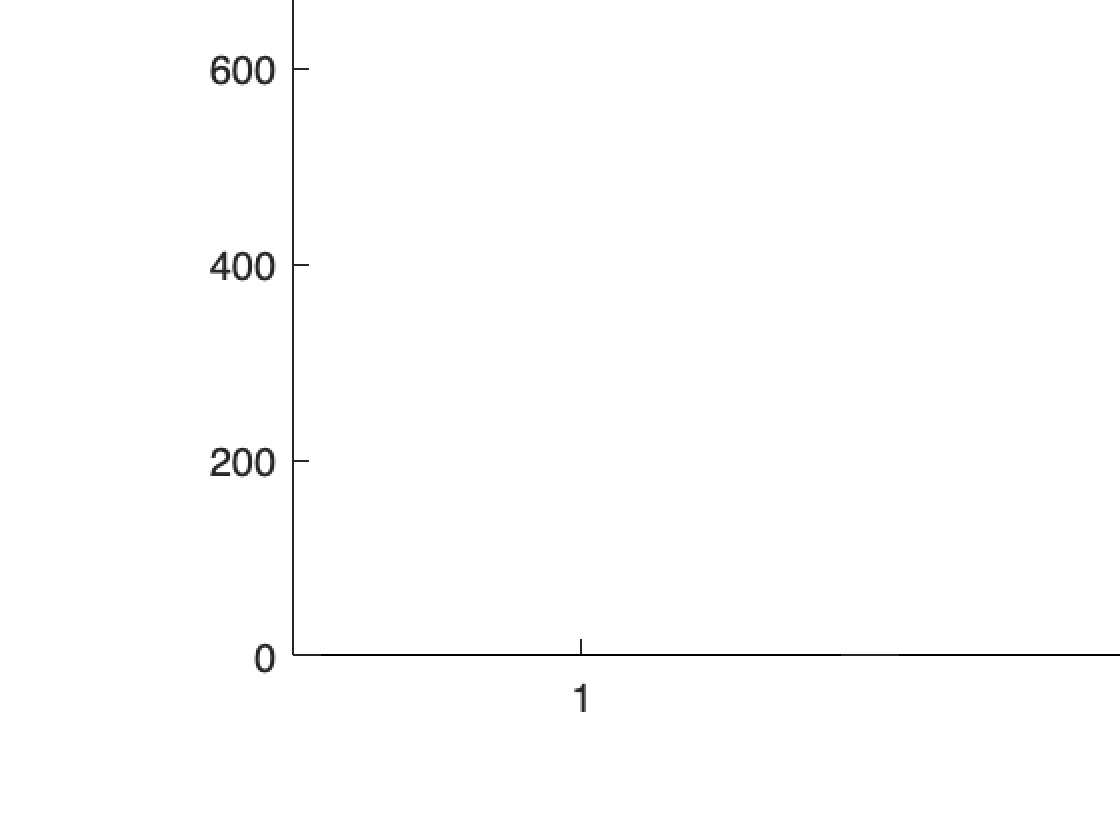

histogram(C4.Investments)
title(['Investments'])


summary(C4(:, "Income"))

Variables:

    Income: 1386×1 double

        Values:

            Min       0.078646
            Median      0.6493
            Max        0.97972



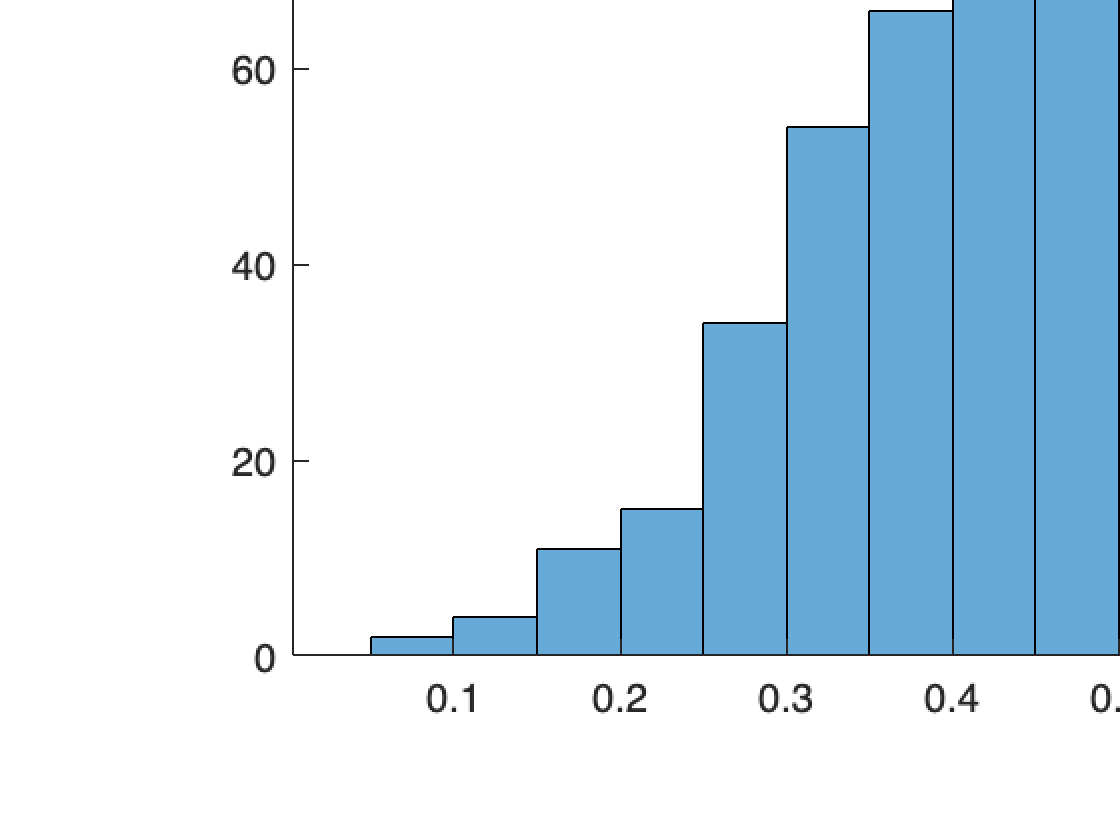

histogram(C4.Income)

mean(C4.Income)

ans = 0.6380


summary(C4(:, "Wealth"))

Variables:

    Wealth: 1386×1 double

        Values:

            Min       0.056928
            Median     0.65864
            Max        0.99454



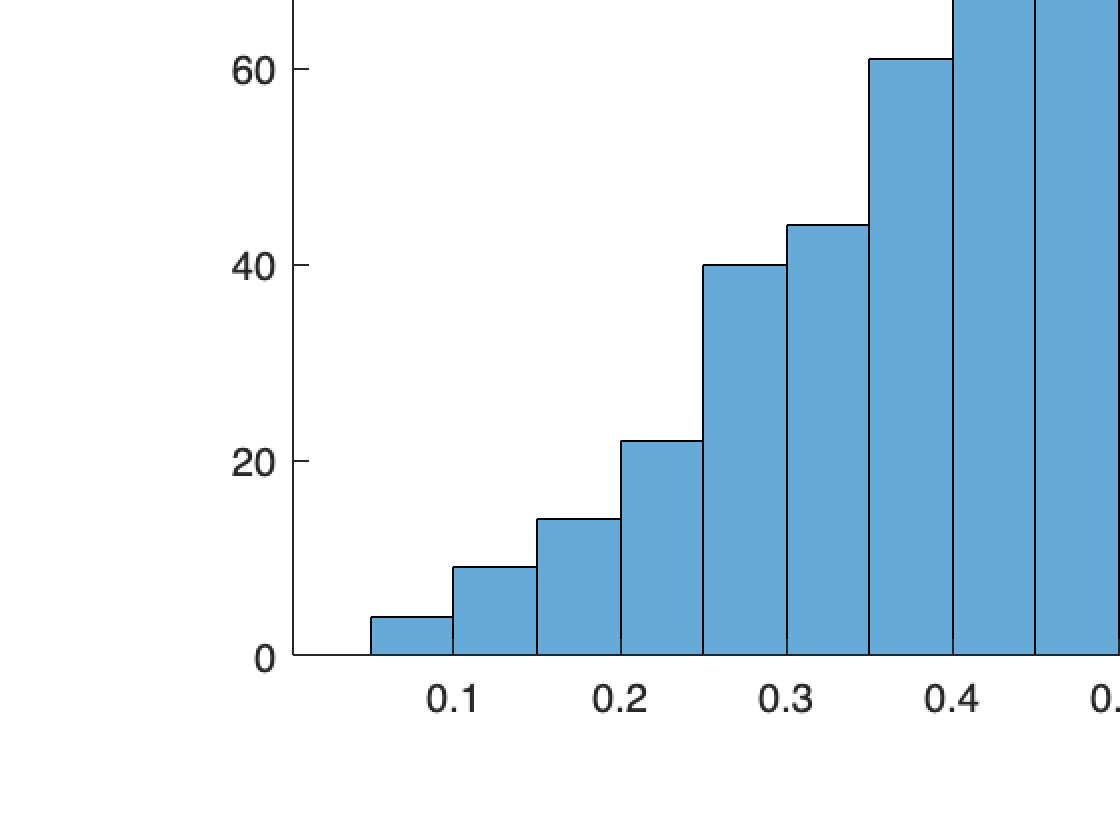

histogram(C4.Wealth)

mean(C4.Wealth)

ans = 0.6388


summary(C4(:, "Debt"))

Variables:

    Debt: 1386×1 double

        Values:

            Min       0.0053773
            Median      0.51674
            Max         0.97691



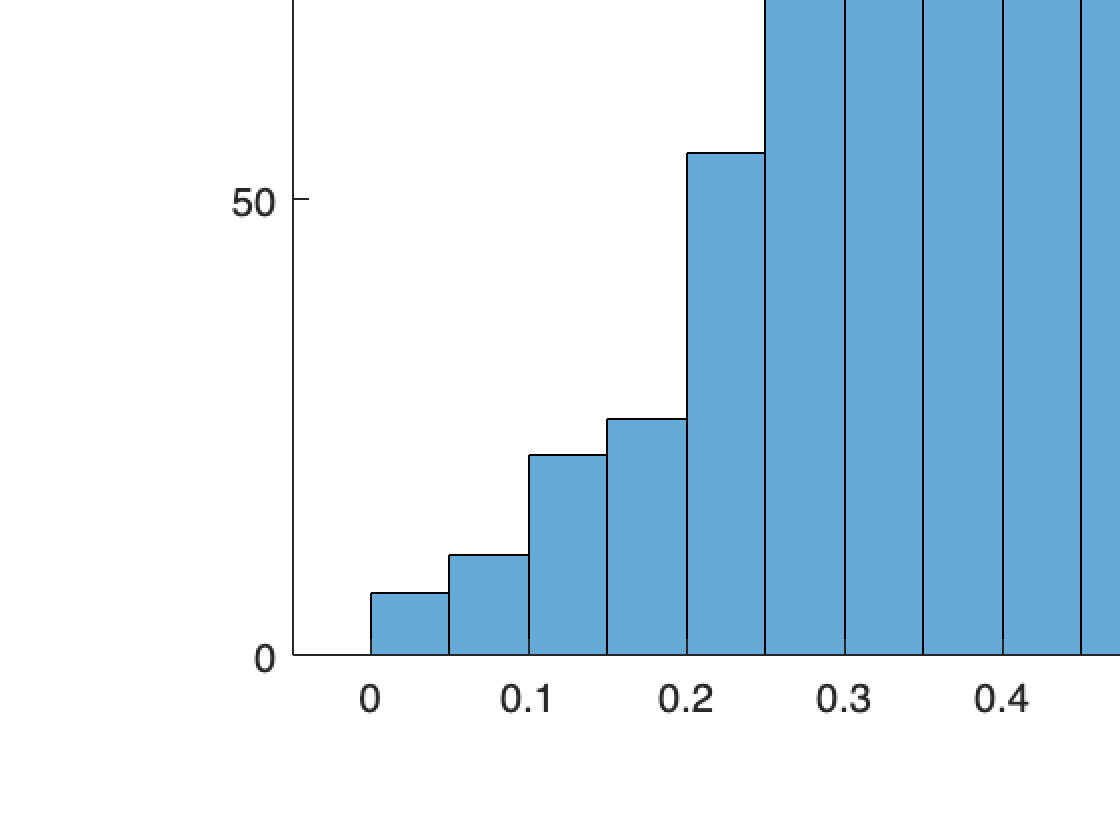

histogram(C4.Debt)

mean(C4.Debt)

ans = 0.5107


summary(C4(:, "FinEdu"))

Variables:

    FinEdu: 1386×1 double

        Values:

            Min       0.081457
            Median     0.58926
            Max        0.96253



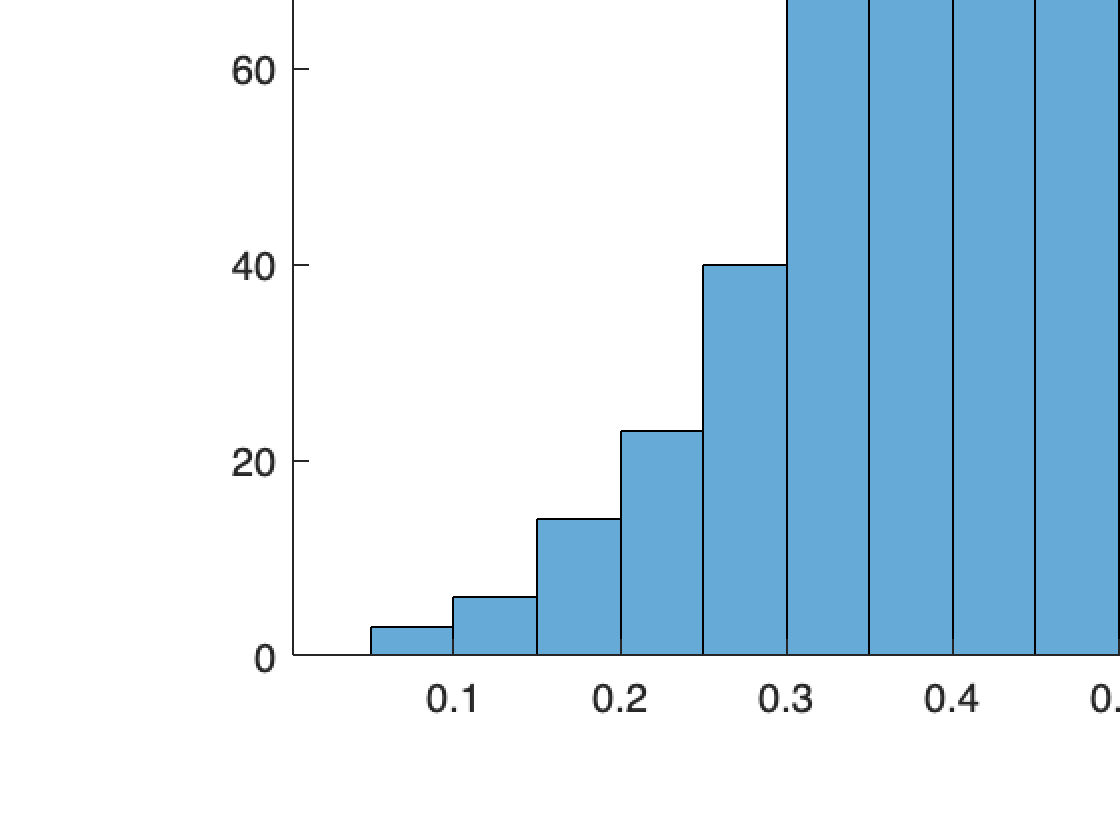

histogram(C4.FinEdu)

mean(C4.FinEdu)

ans = 0.5788


summary(C4(:, "ESG"))

Variables:

    ESG: 1386×1 double

        Values:

            Min       0.14996 
            Median    0.61487 
            Max       0.98952 



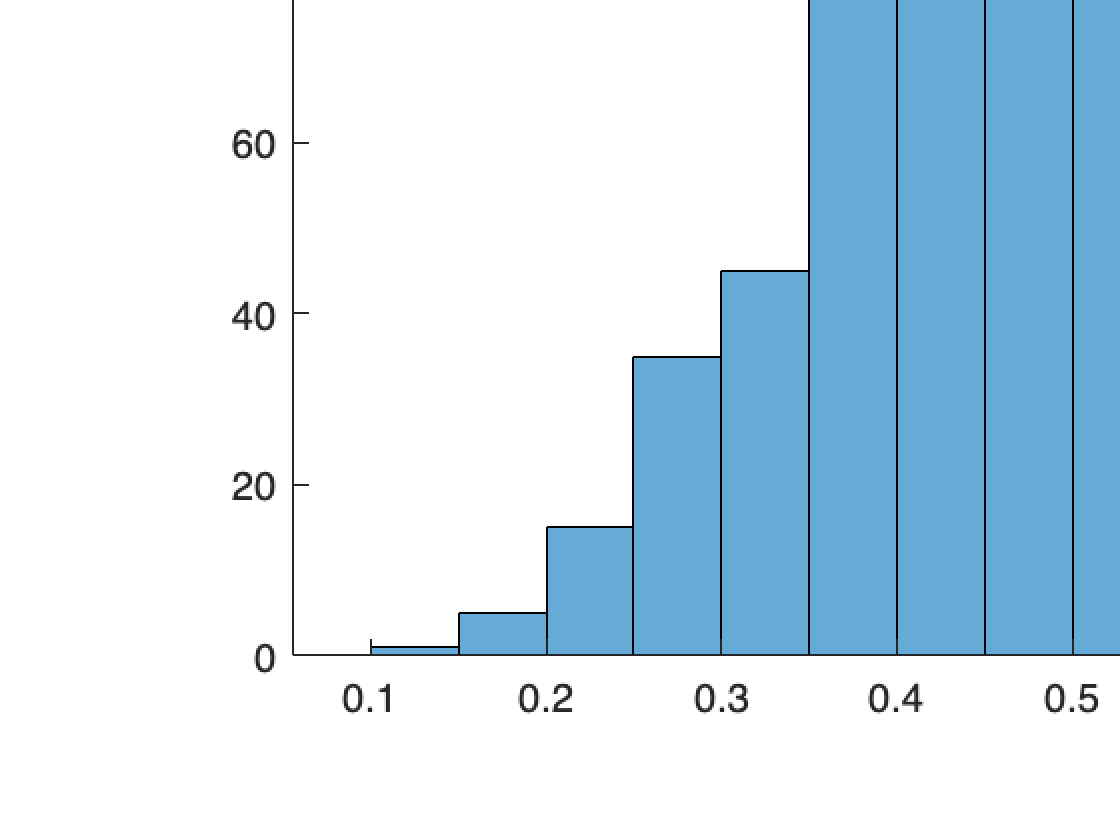

histogram(C4.ESG)

mean(C4.ESG)

ans = 0.6068


summary(C4(:, "Digital"))

Variables:

    Digital: 1386×1 double

        Values:

            Min             0 
            Median    0.61306 
            Max       0.96934 



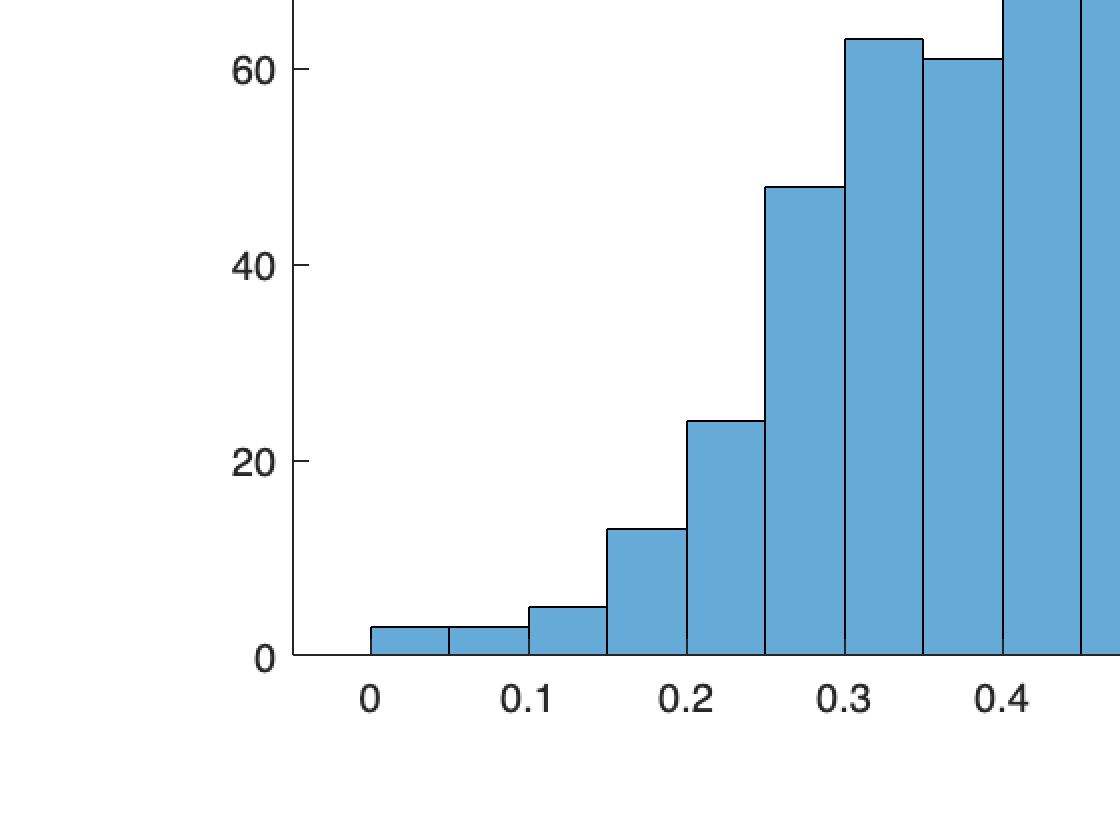

histogram(C4.Digital)

mean(C4.Digital)

ans = 0.6025


summary(C4(:, "BankFriend"))

Variables:

    BankFriend: 1386×1 double

        Values:

            Min        0.1232 
            Median    0.62632 
            Max       0.97423 



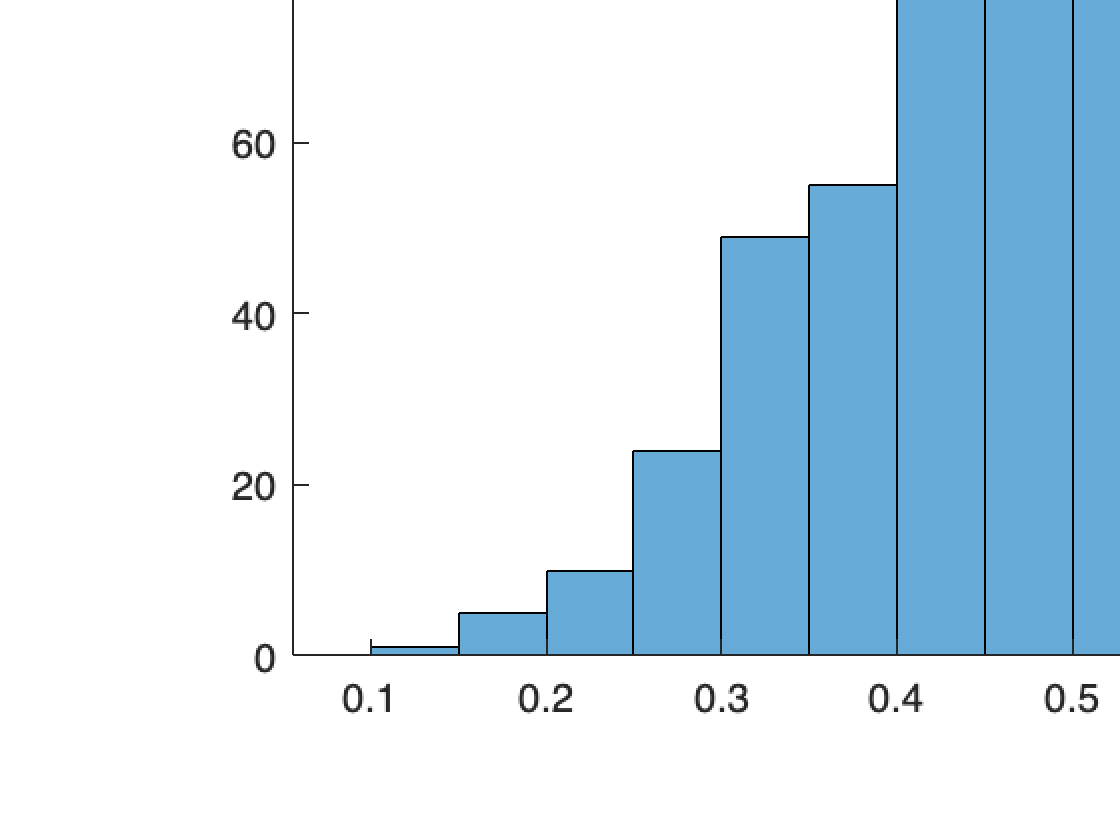

histogram(C4.BankFriend)

mean(C4.BankFriend)

ans = 0.6231


summary(C4(:, "LifeStyle"))

Variables:

    LifeStyle: 1386×1 double

        Values:

            Min       0.0017685
            Median      0.55118
            Max         0.97859



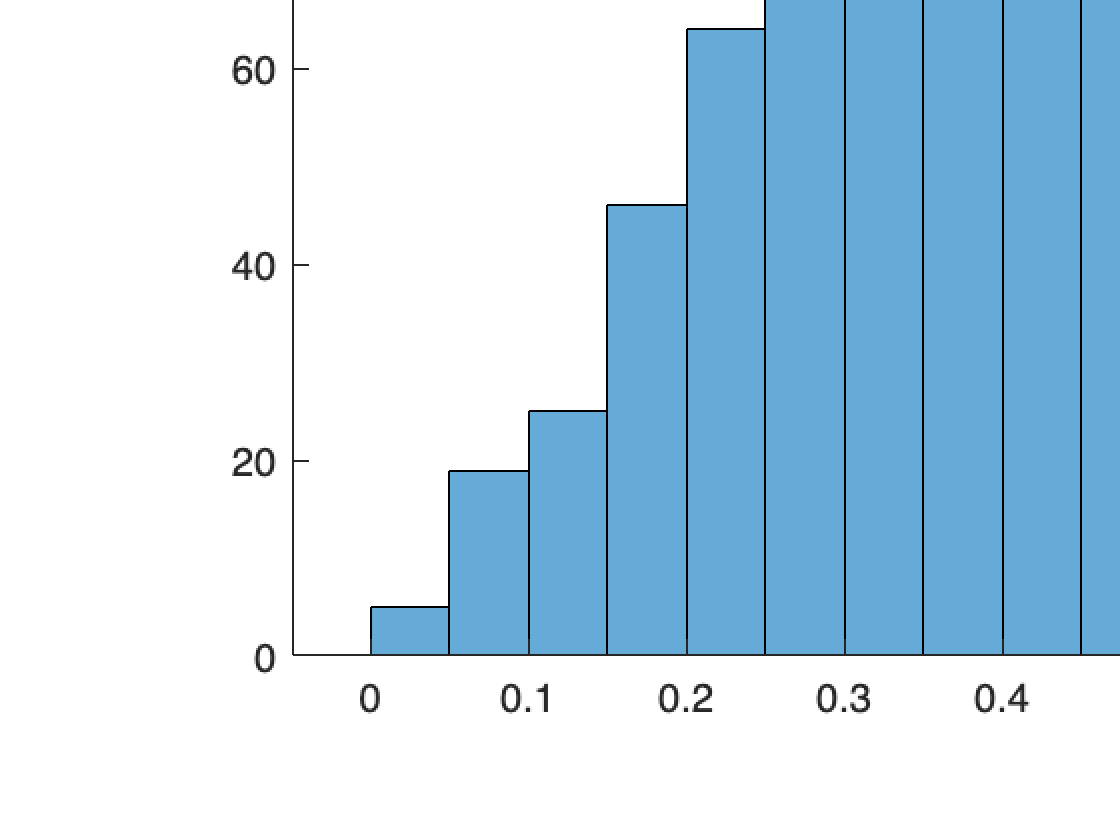

histogram(C4.LifeStyle)

mean(C4.LifeStyle)

ans = 0.5370


summary(C4(:, "Luxury"))

Variables:

    Luxury: 1386×1 double

        Values:

            Min       0.025813
            Median     0.55684
            Max        0.99143



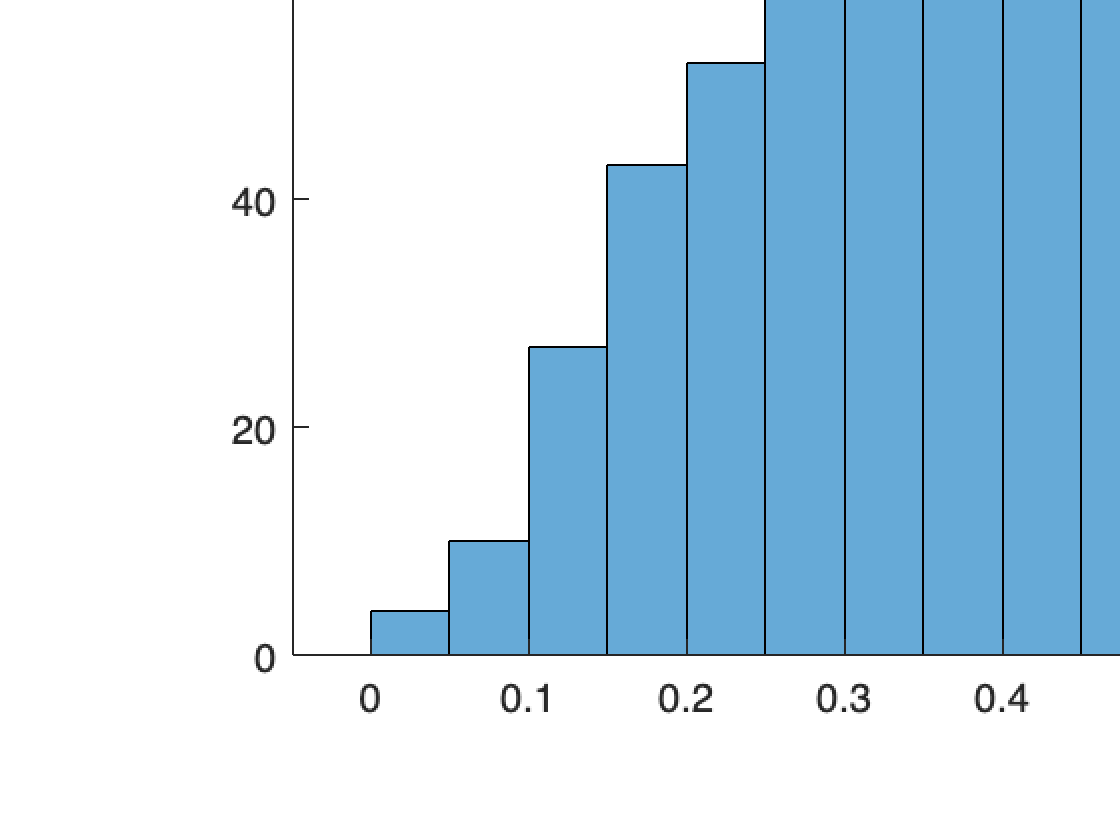

histogram(C4.Luxury)

mean(C4.Luxury)

ans = 0.5577


summary(C4(:, "Saving"))

Variables:

    Saving: 1386×1 double

        Values:

            Min       0.027866
            Median     0.58462
            Max        0.94431



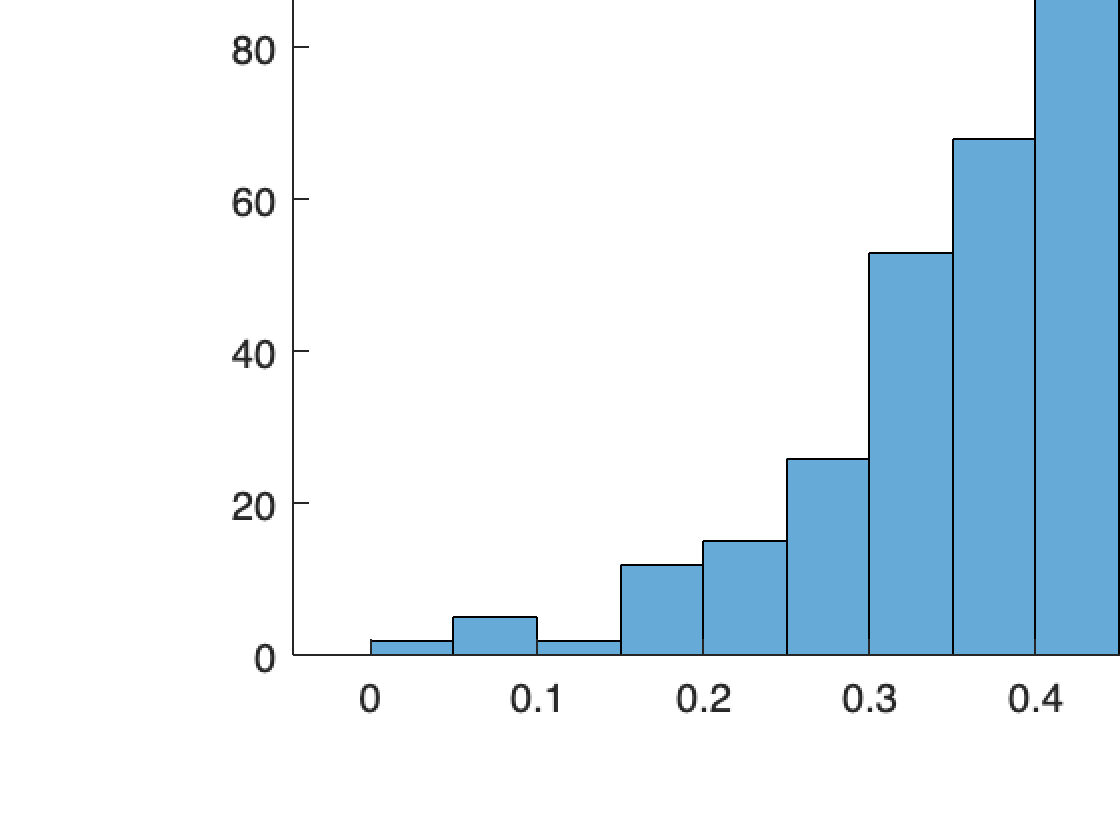

histogram(C4.Saving)

mean(C4.Saving)

ans = 0.5755


C5 = BankClients(T6==5,:);

% Frequency tables
tabulate(C5.Job)

  Value    Count   Percent
      1      101     13.12%
      2      390     50.65%
      3        7      0.91%
      4       17      2.21%
      5      255     33.12%


tabulate(C5.Area)

  Value    Count   Percent
      1      529     68.70%
      2      150     19.48%
      3       91     11.82%


tabulate(C5.CitySize)

  Value    Count   Percent
      1      296     38.44%
      2      369     47.92%
      3      105     13.64%


tabulate(C5.Investments)

  Value    Count   Percent
      1      770    100.00%
      2        0      0.00%
      3        0      0.00%



summary(C5(:,"Age"))

Variables:

    Age: 770×1 double

        Values:

            Min          56   
            Median       80   
            Max          95   



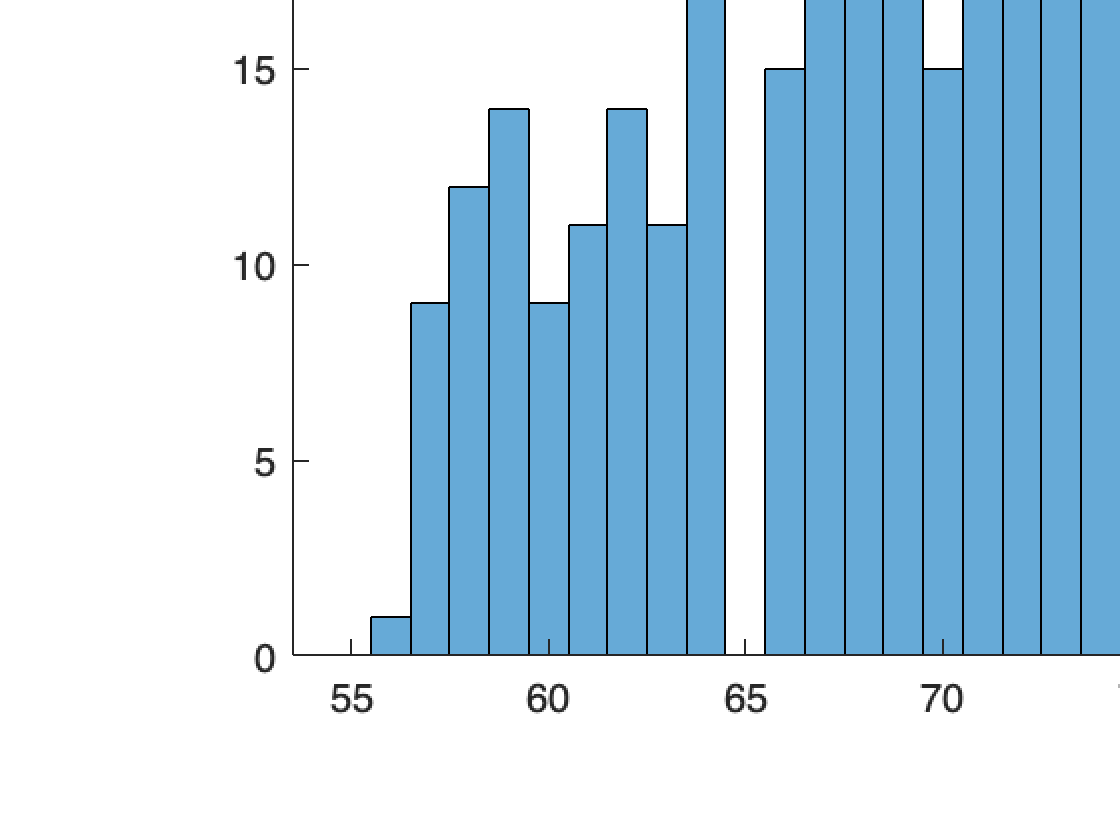

histogram(C5.Age)
title('Age')

mean(C5.Age)

ans = 78.8883


summary(C5(:,"Job"))

Variables:

    Job: 770×1 categorical

        Values:

            1      101   
            2      390   
            3        7   
            4       17   
            5      255   



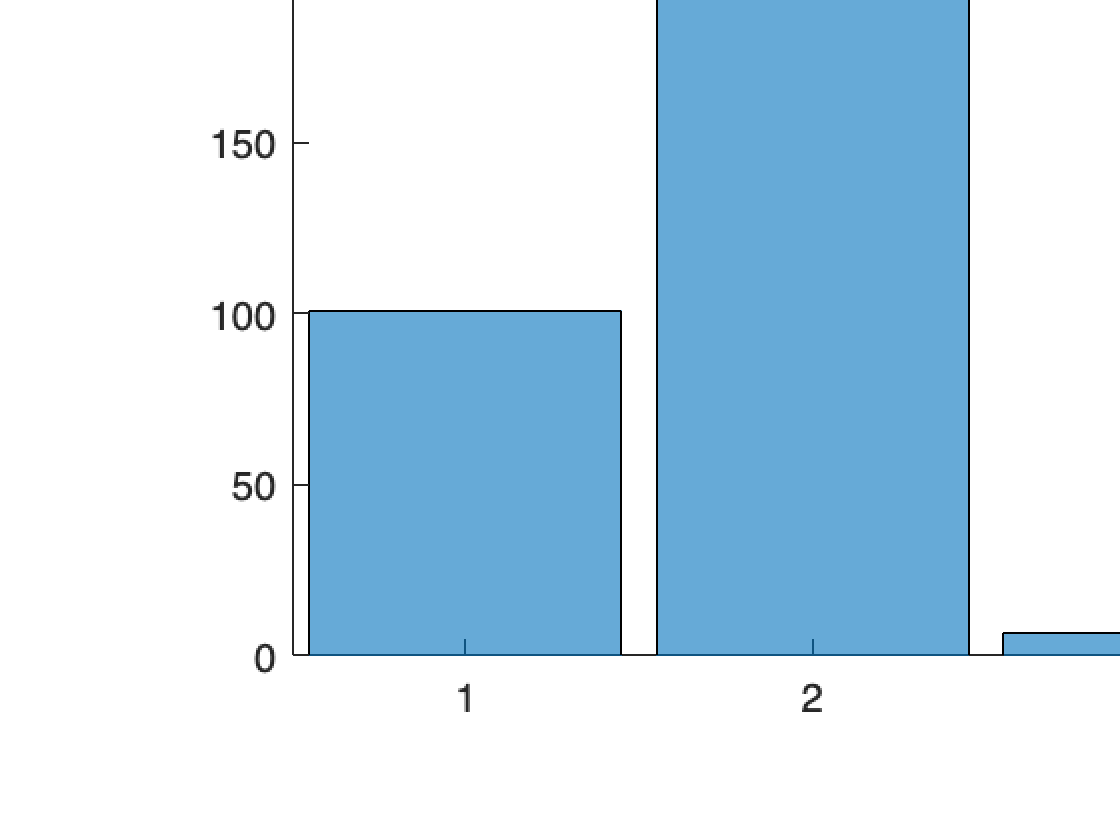

histogram(C5.Job)
title('Job')


summary(C5(:,"CitySize"))

Variables:

    CitySize: 770×1 categorical

        Values:

            1      296   
            2      369   
            3      105   



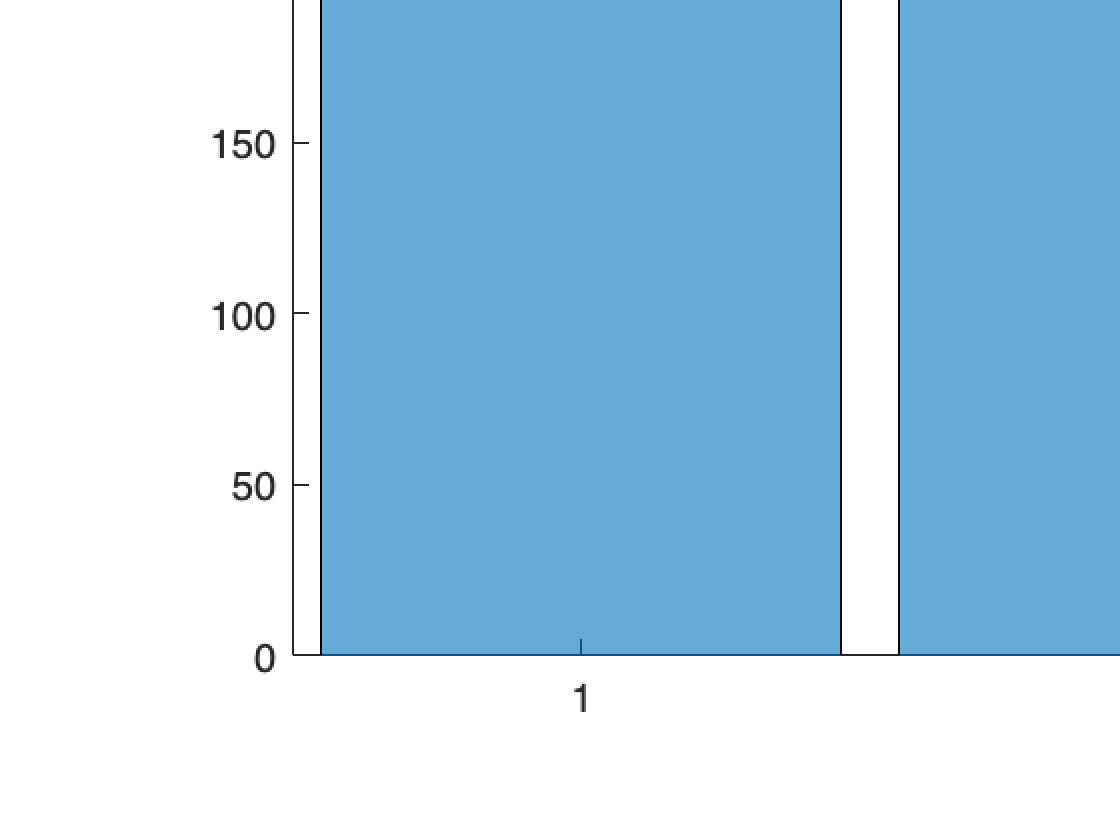

histogram(C5.CitySize)
title('City Size')



summary(C5(:,"Area"))

Variables:

    Area: 770×1 categorical

        Values:

            1      529   
            2      150   
            3       91   



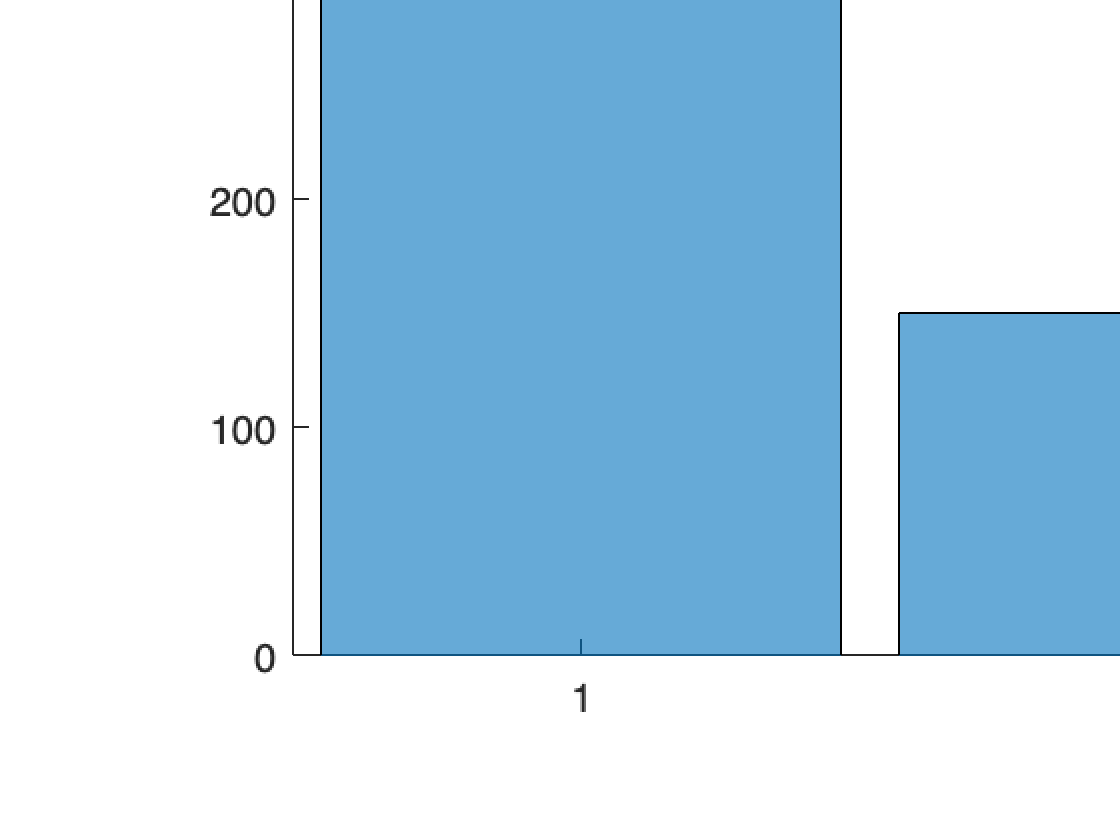

histogram(C5.Area)
title('Area')


summary(C5(:,"Investments"))

Variables:

    Investments: 770×1 categorical

        Values:

            1      770   
            2        0   
            3        0   



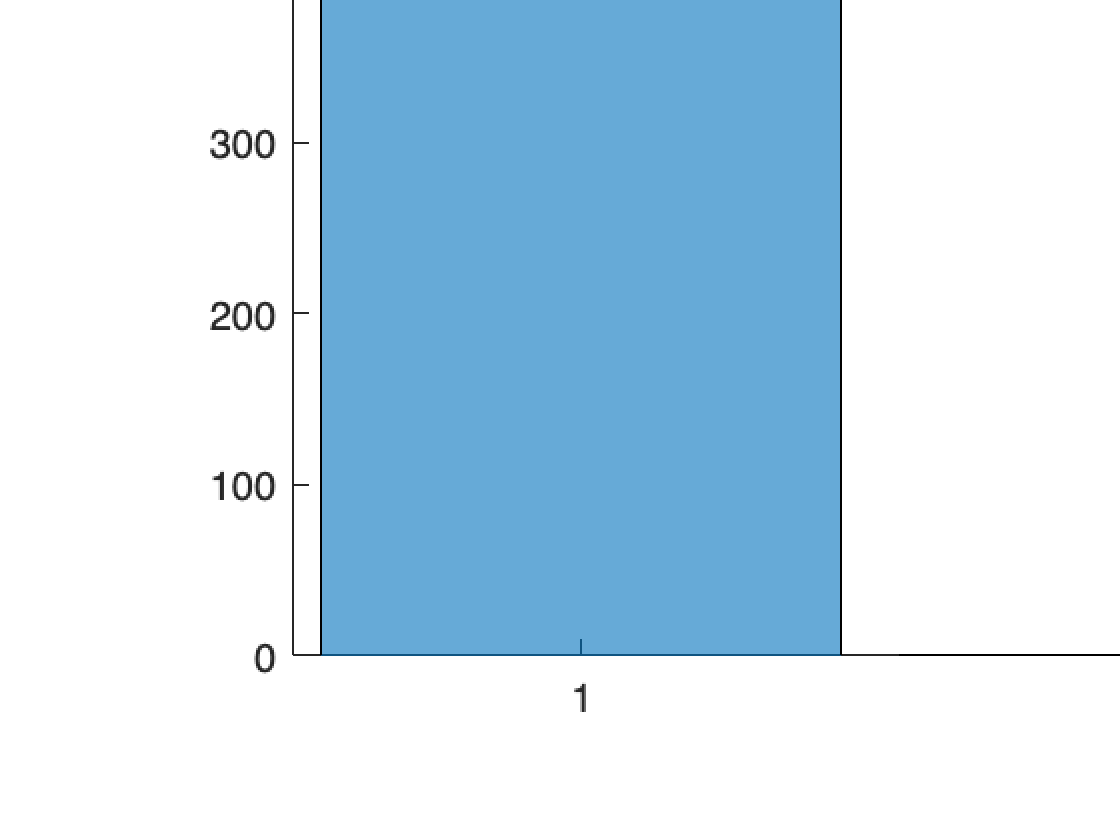

histogram(C5.Investments)
title(['Investments'])


summary(C5(:, "Income"))

Variables:

    Income: 770×1 double

        Values:

            Min             0 
            Median    0.48199 
            Max       0.96484 



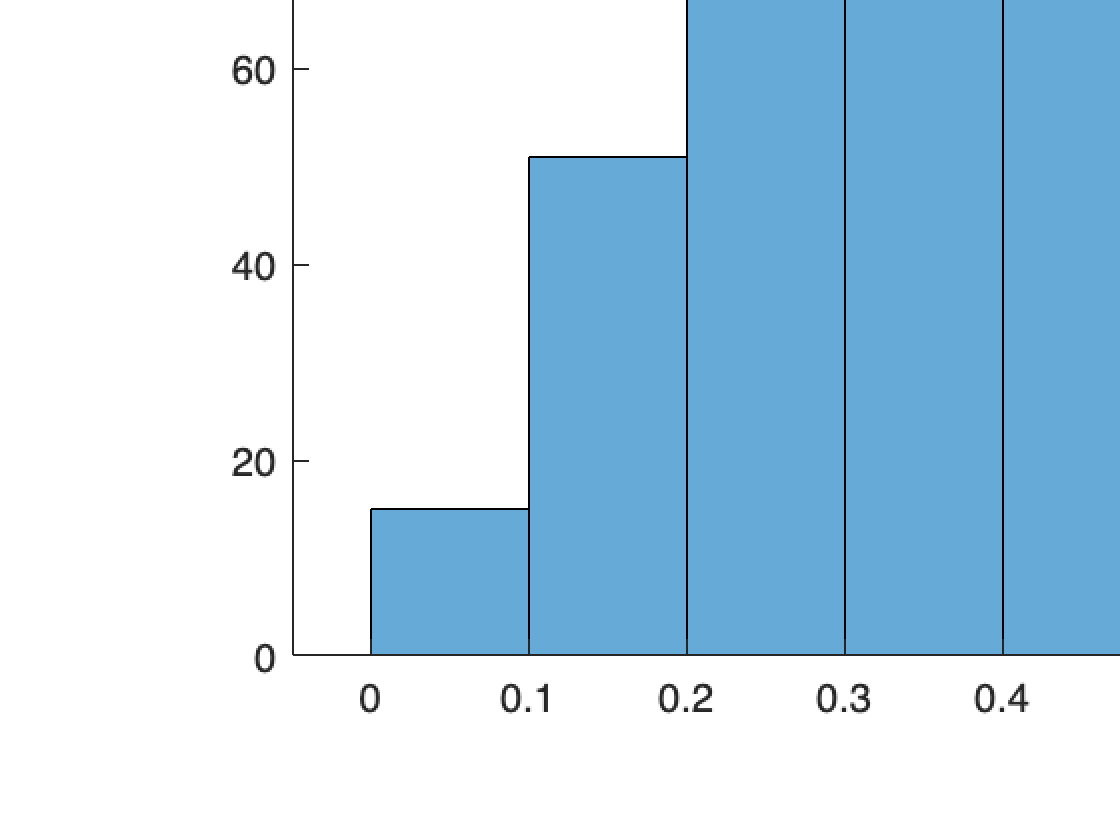

histogram(C5.Income)

mean(C5.Income)

ans = 0.4936


summary(C5(:, "Wealth"))

Variables:

    Wealth: 770×1 double

        Values:

            Min             0 
            Median    0.49217 
            Max        0.9956 



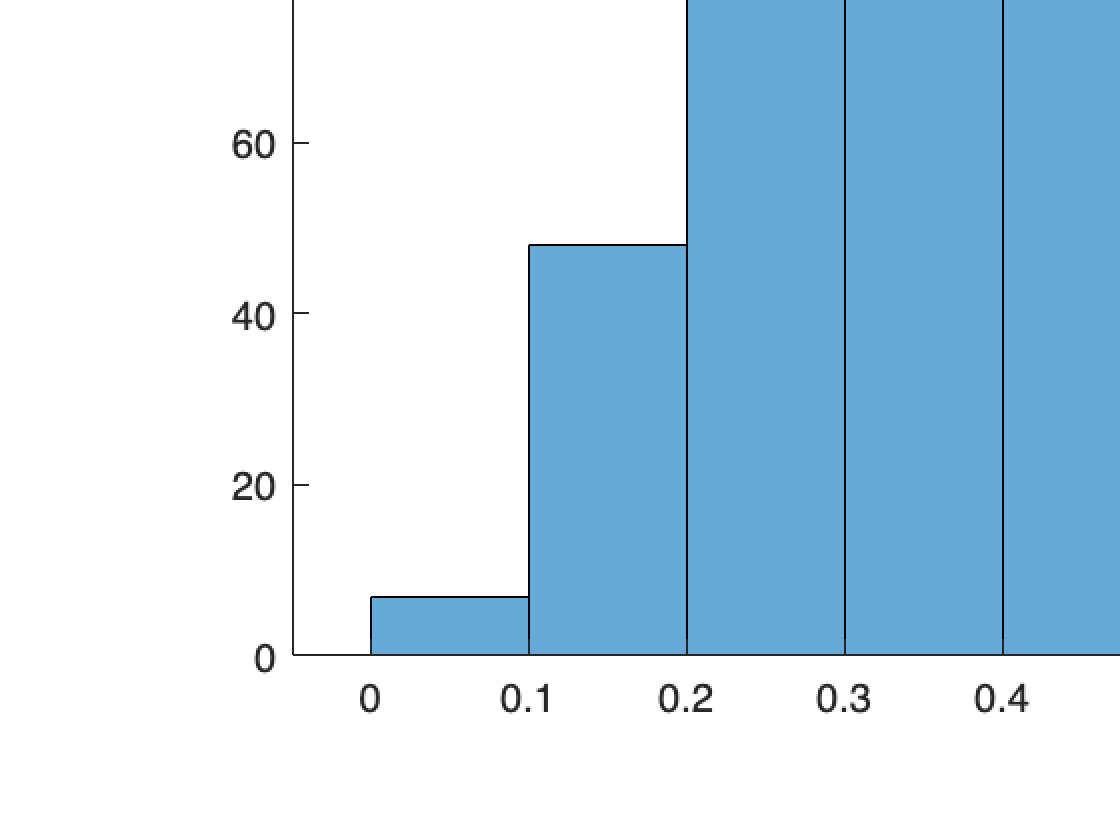

histogram(C5.Wealth)

mean(C5.Wealth)

ans = 0.5030


summary(C5(:, "Debt"))

Variables:

    Debt: 770×1 double

        Values:

            Min             0 
            Median    0.32391 
            Max       0.95661 



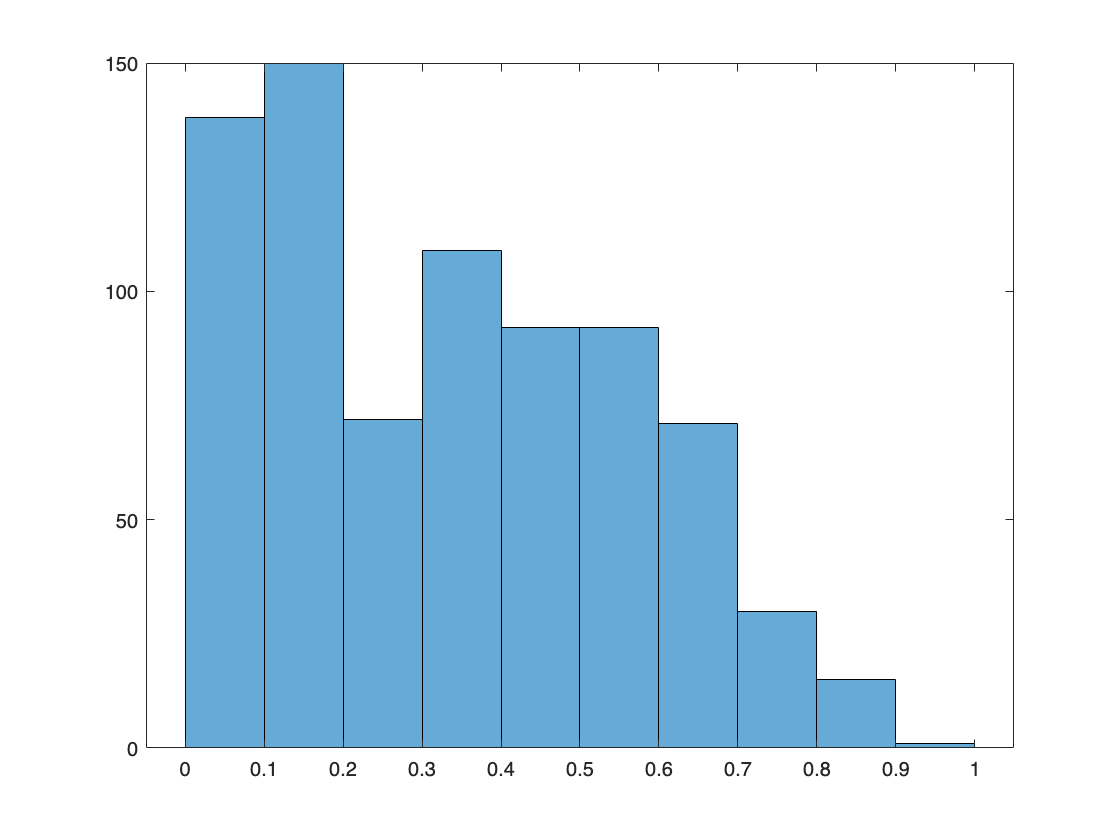

histogram(C5.Debt)

mean(C5.Debt)

ans = 0.3379


summary(C5(:, "FinEdu"))

Variables:

    FinEdu: 770×1 double

        Values:

            Min       0.030162
            Median     0.42715
            Max         0.9494



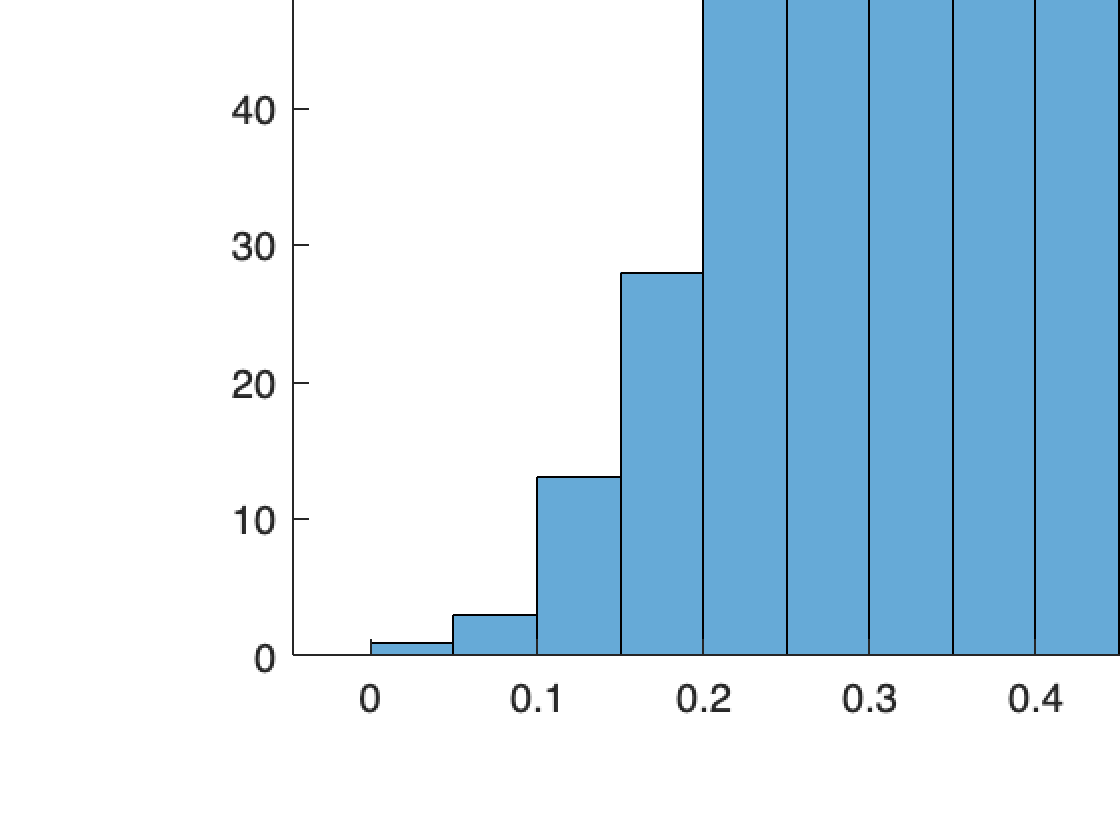

histogram(C5.FinEdu)

mean(C5.FinEdu)

ans = 0.4358


summary(C5(:, "ESG"))

Variables:

    ESG: 770×1 double

        Values:

            Min       0.13347 
            Median    0.58268 
            Max       0.93527 



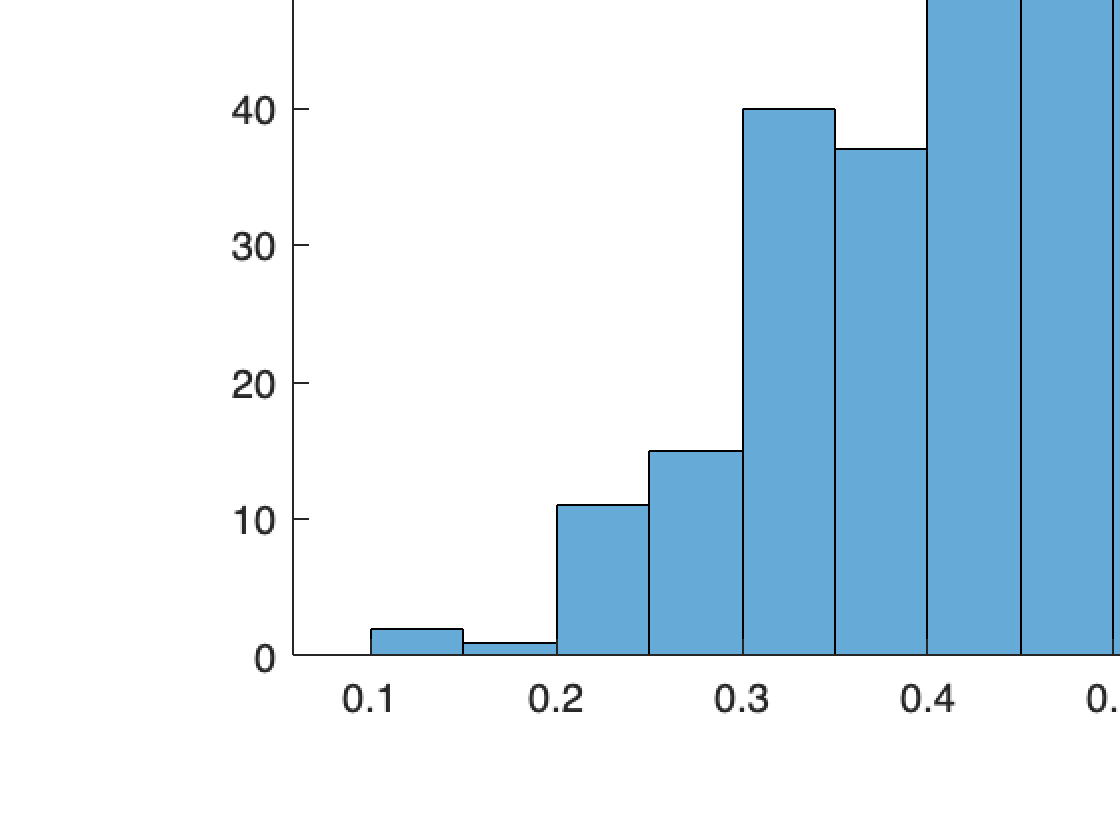

histogram(C5.ESG)

mean(C5.ESG)

ans = 0.5760


summary(C5(:, "Digital"))

Variables:

    Digital: 770×1 double

        Values:

            Min             0 
            Median    0.42729 
            Max        0.9402 



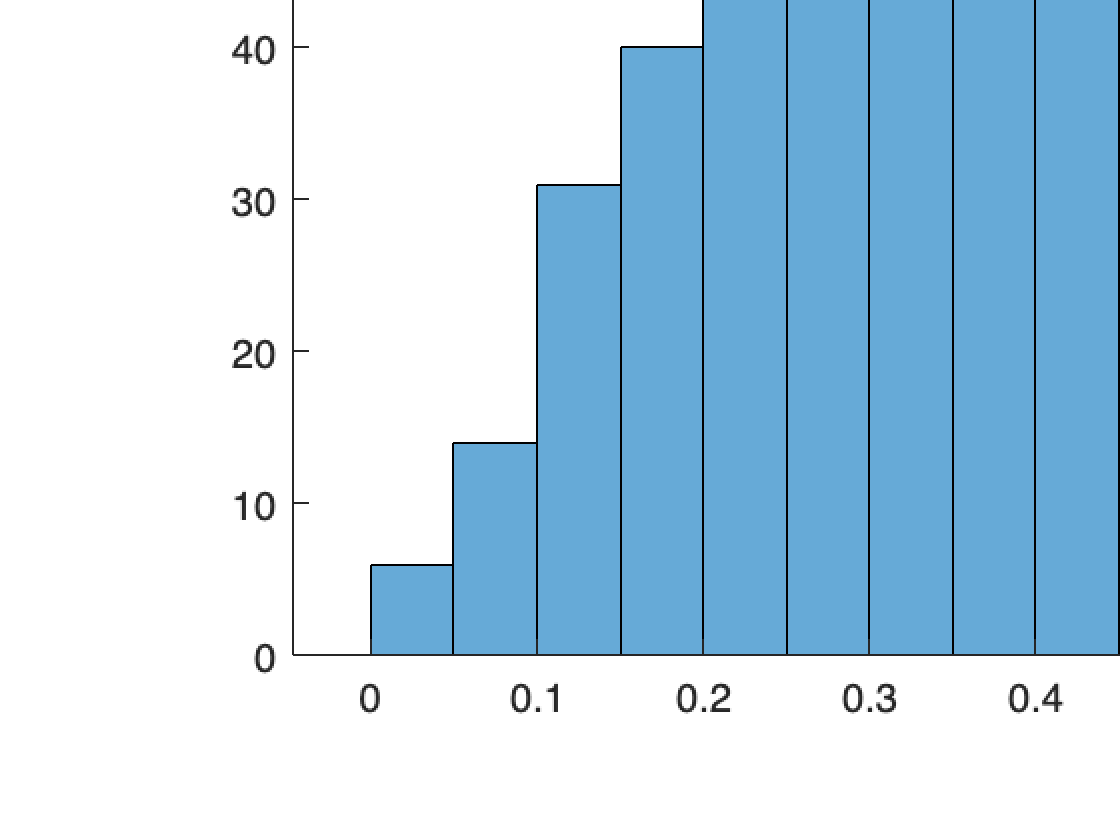

histogram(C5.Digital)

mean(C5.Digital)

ans = 0.4368


summary(C5(:, "BankFriend"))

Variables:

    BankFriend: 770×1 double

        Values:

            Min       0.16676 
            Median    0.60708 
            Max       0.93576 



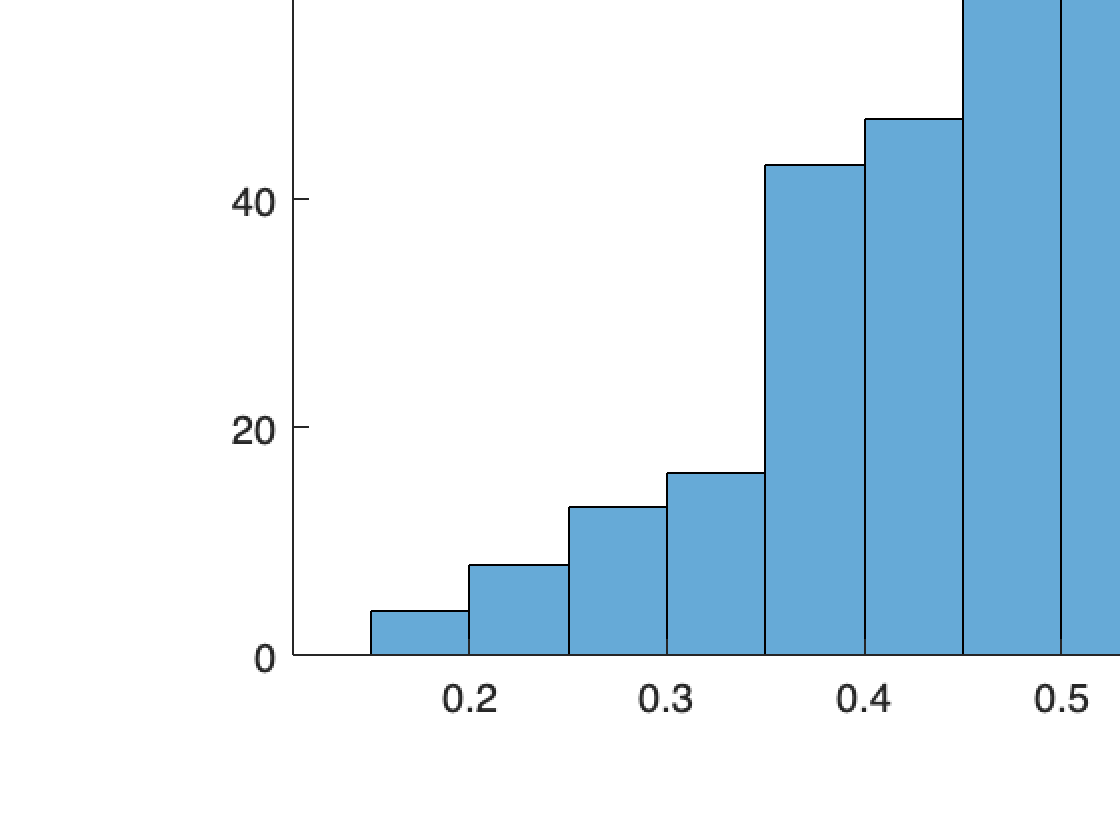

histogram(C5.BankFriend)

mean(C5.BankFriend)

ans = 0.6018


summary(C5(:, "LifeStyle"))

Variables:

    LifeStyle: 770×1 double

        Values:

            Min             0 
            Median    0.33985 
            Max       0.90011 



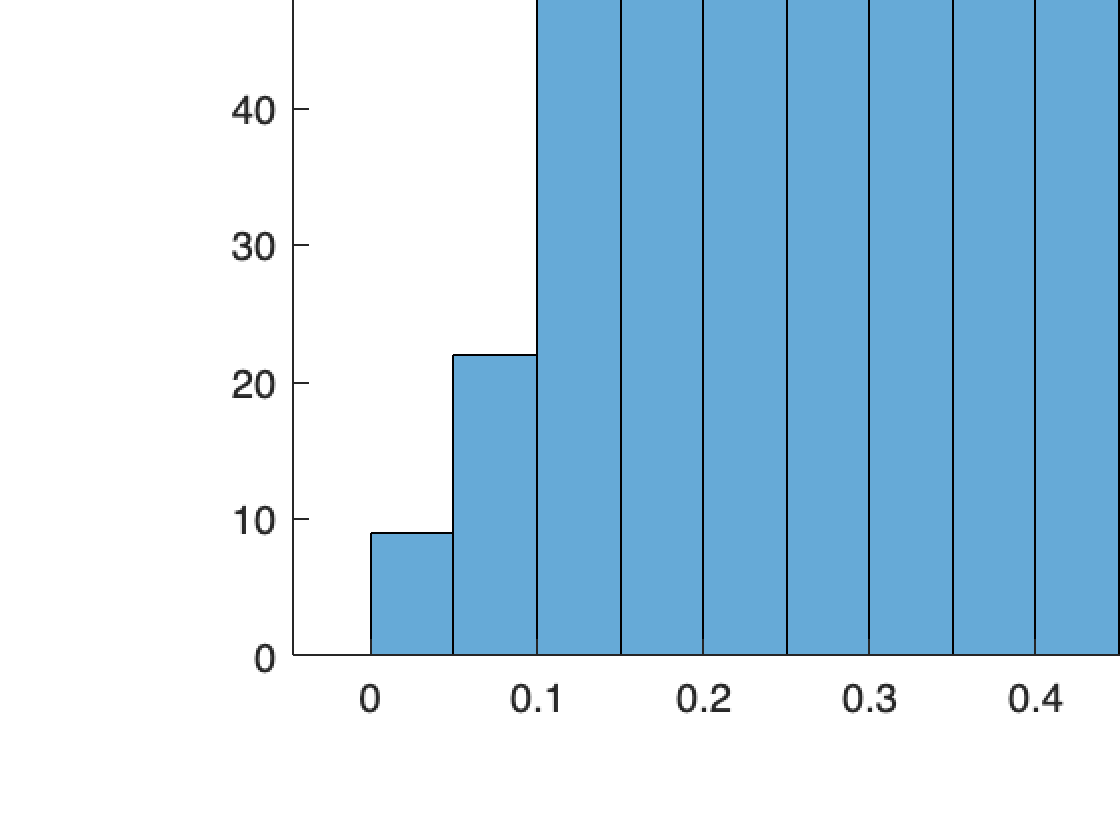

histogram(C5.LifeStyle)

mean(C5.LifeStyle)

ans = 0.3656


summary(C5(:, "Luxury"))

Variables:

    Luxury: 770×1 double

        Values:

            Min             0 
            Median     0.3153 
            Max       0.95478 



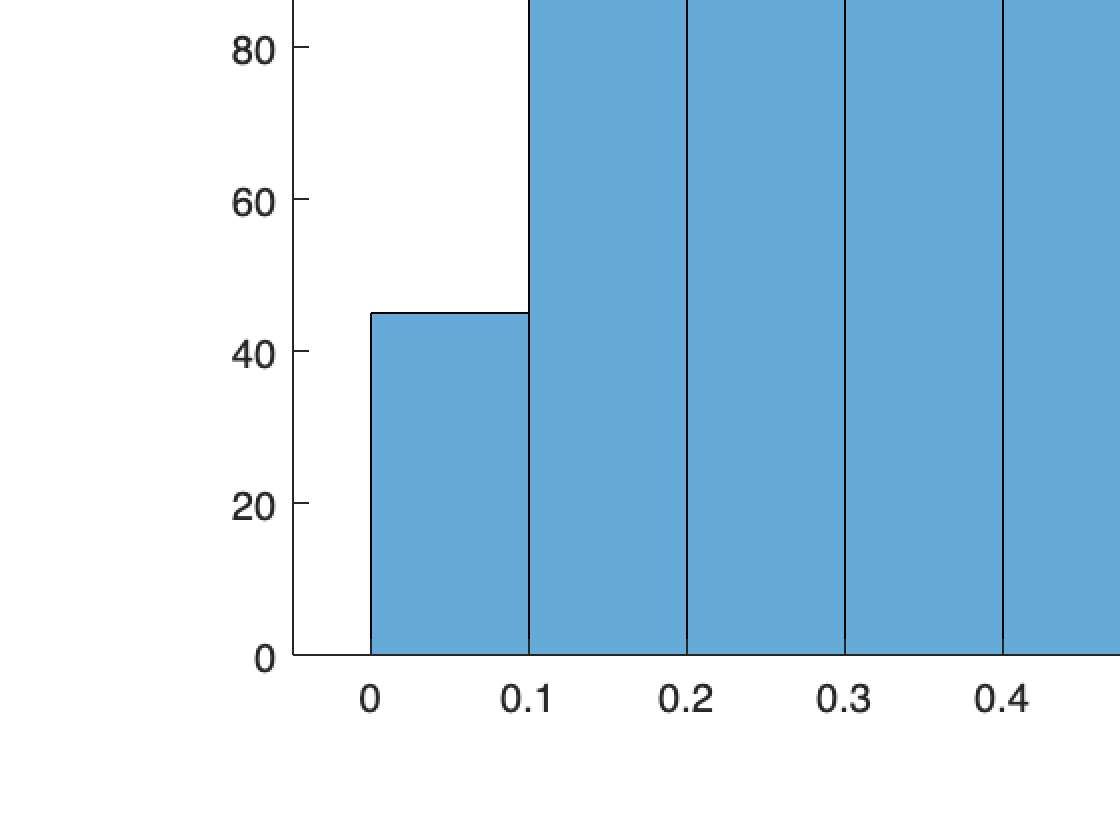

histogram(C5.Luxury)

mean(C5.Luxury)

ans = 0.3617


summary(C5(:, "Saving"))

Variables:

    Saving: 770×1 double

        Values:

            Min             0 
            Median    0.47246 
            Max       0.90273 



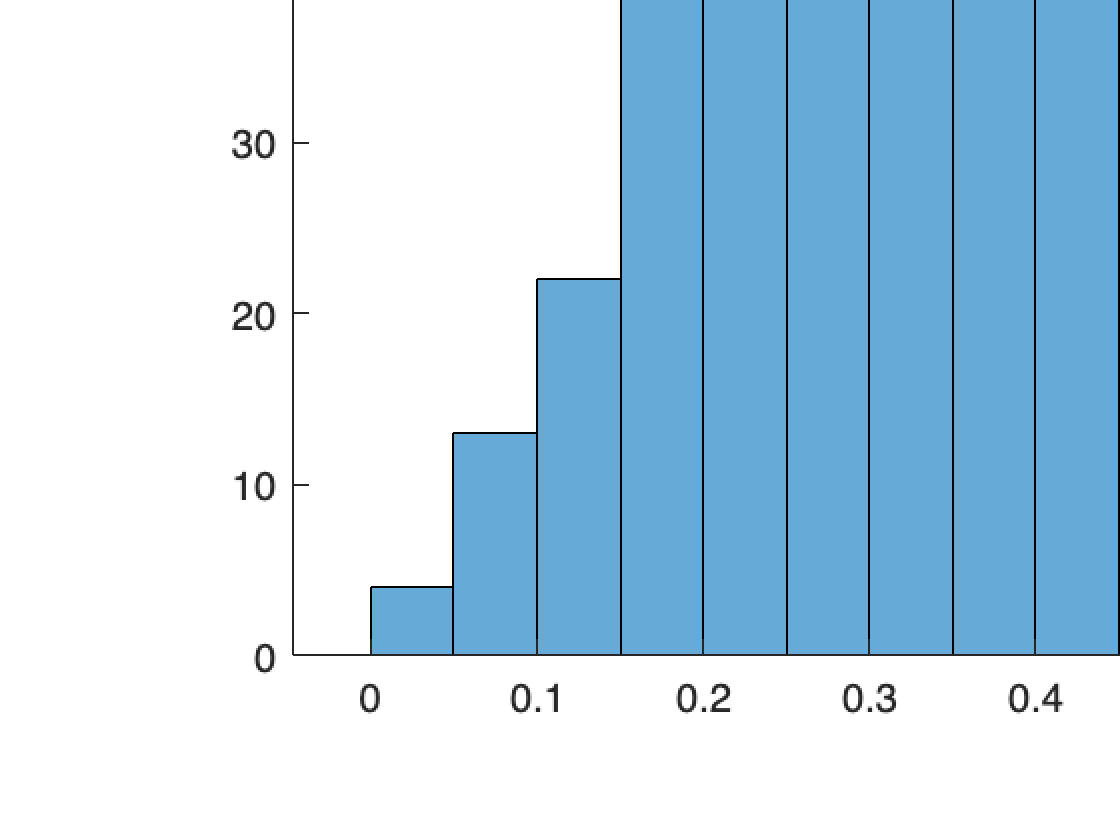

histogram(C5.Saving)

mean(C5.Saving)

ans = 0.4633

C6 = BankClients(T6==6,:);

% Frequency tables
tabulate(C6.Job)

  Value    Count   Percent
      1       85     15.62%
      2      399     73.35%
      3       19      3.49%
      4       18      3.31%
      5       23      4.23%


tabulate(C6.Area)

  Value    Count   Percent
      1      375     68.93%
      2      103     18.93%
      3       66     12.13%


tabulate(C6.CitySize)

  Value    Count   Percent
      1      186     34.19%
      2      214     39.34%
      3      144     26.47%


%% 
tabulate(C1.Investments)

  Value    Count   Percent
      1        0      0.00%
      2      737    100.00%
      3        0      0.00%


tabulate(C2.Investments)

  Value    Count   Percent
      1        0      0.00%
      2      759    100.00%
      3        0      0.00%


tabulate(C3.Investments)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3      804    100.00%


tabulate(C4.Investments)

  Value    Count   Percent
      1        0      0.00%
      2        0      0.00%
      3     1386    100.00%


tabulate(C5.Investments)

  Value    Count   Percent
      1      770    100.00%
      2        0      0.00%
      3        0      0.00%


tabulate(C6.Investments)

  Value    Count   Percent
      1      544    100.00%
      2        0      0.00%
      3        0      0.00%



%%
summary(C6(:,"Age"))

Variables:

    Age: 544×1 double

        Values:

            Min           19  
            Median      36.5  
            Max           57  



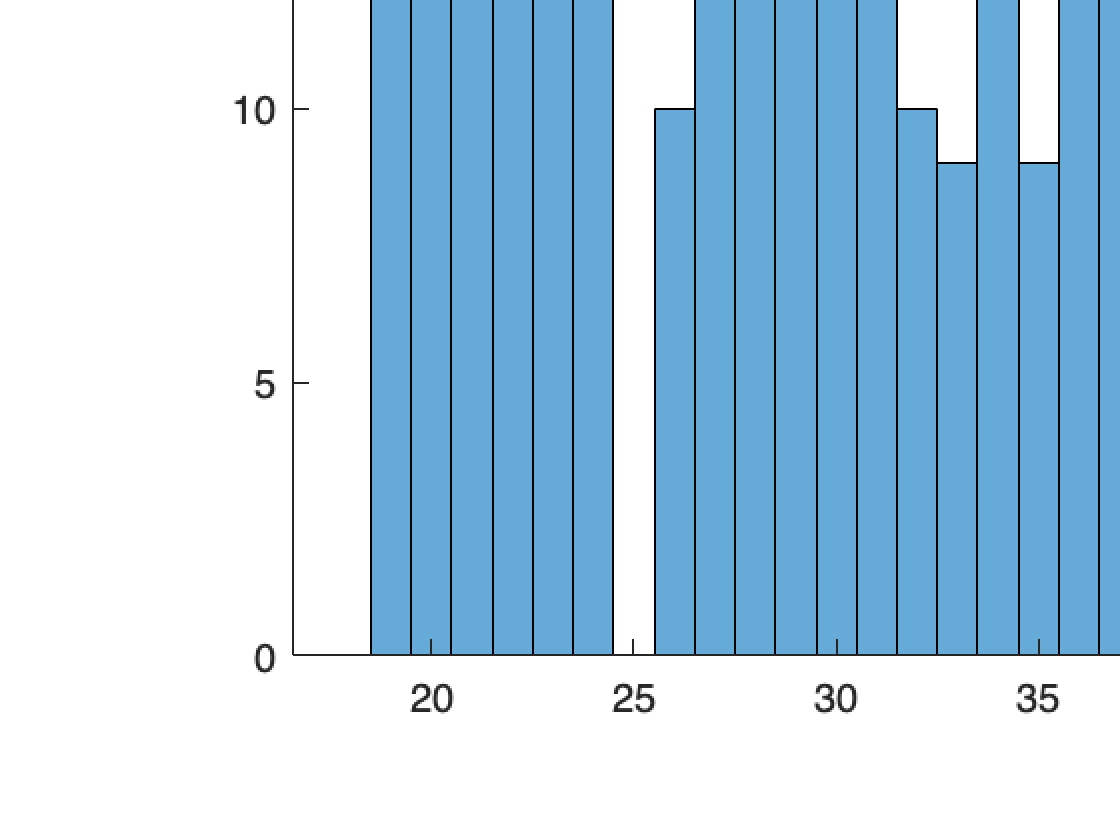

histogram(C6.Age)
title('Age')

mean(C6.Age)

ans = 36.8989


summary(C6(:,"Job"))

Variables:

    Job: 544×1 categorical

        Values:

            1       85   
            2      399   
            3       19   
            4       18   
            5       23   



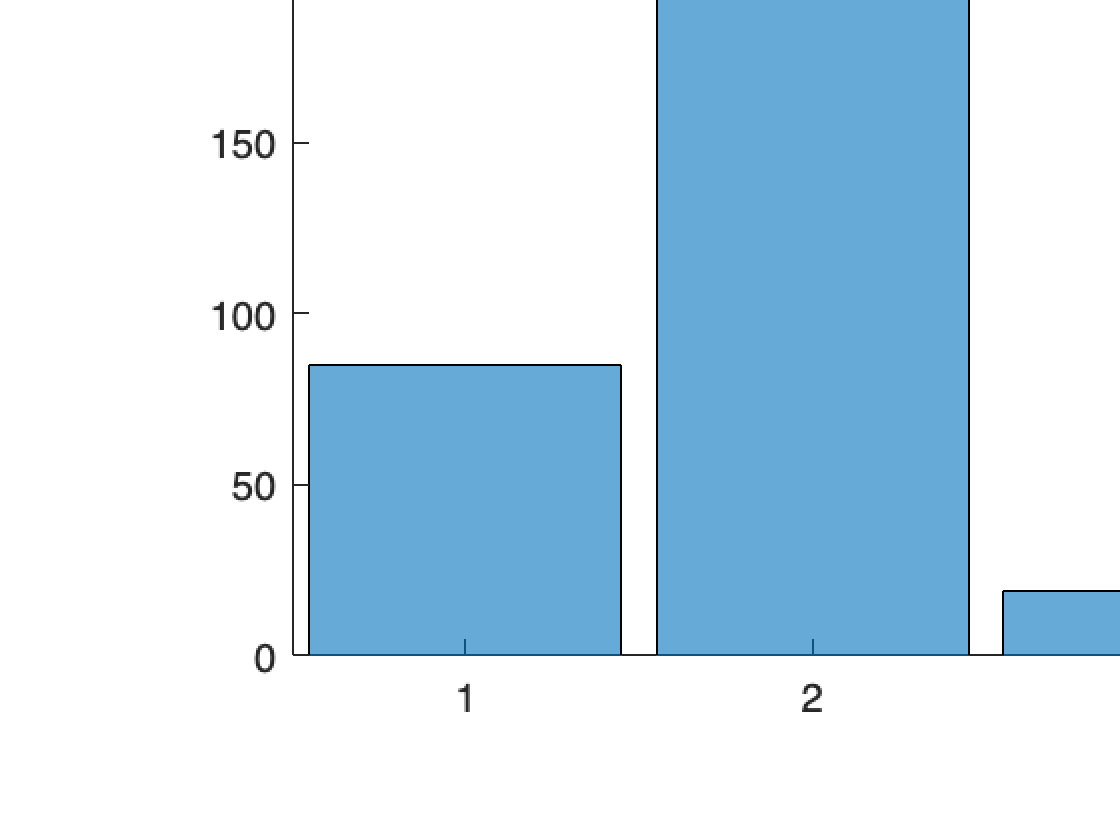

histogram(C6.Job)
title('Job')


summary(C6(:,"CitySize"))

Variables:

    CitySize: 544×1 categorical

        Values:

            1      186   
            2      214   
            3      144   



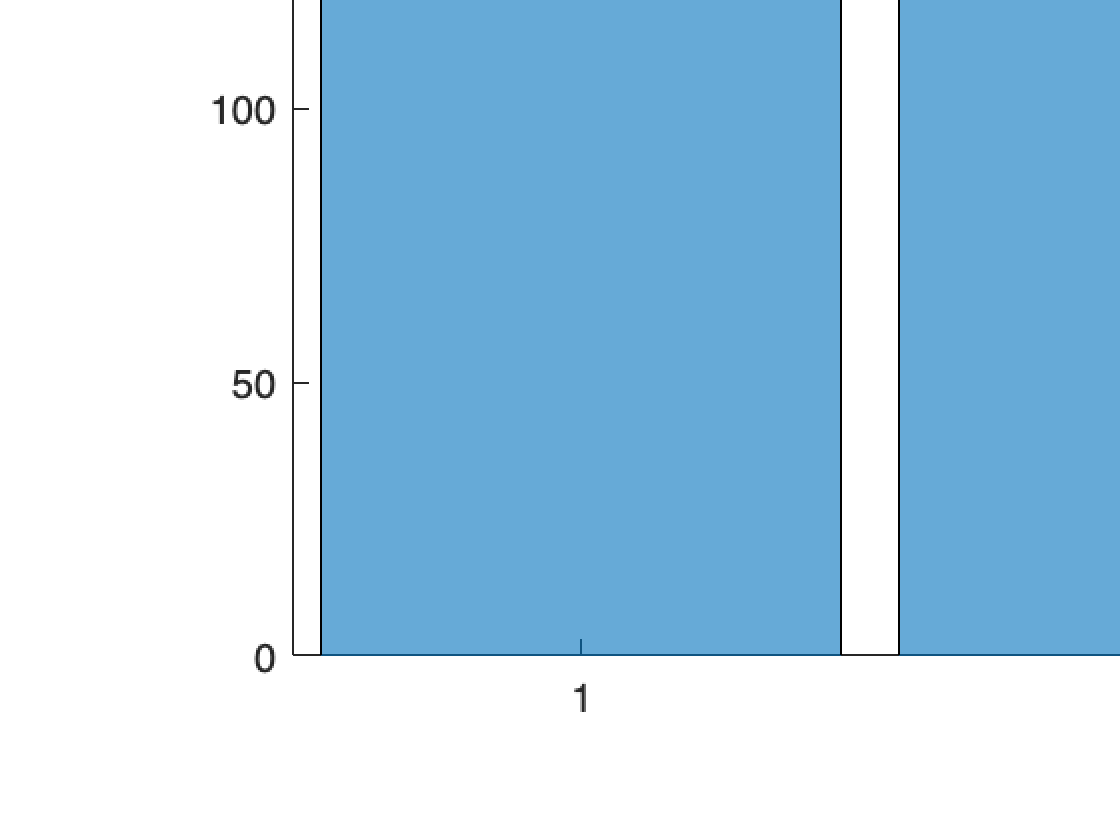

histogram(C6.CitySize)
title('City Size')



summary(C6(:,"Area"))

Variables:

    Area: 544×1 categorical

        Values:

            1      375   
            2      103   
            3       66   



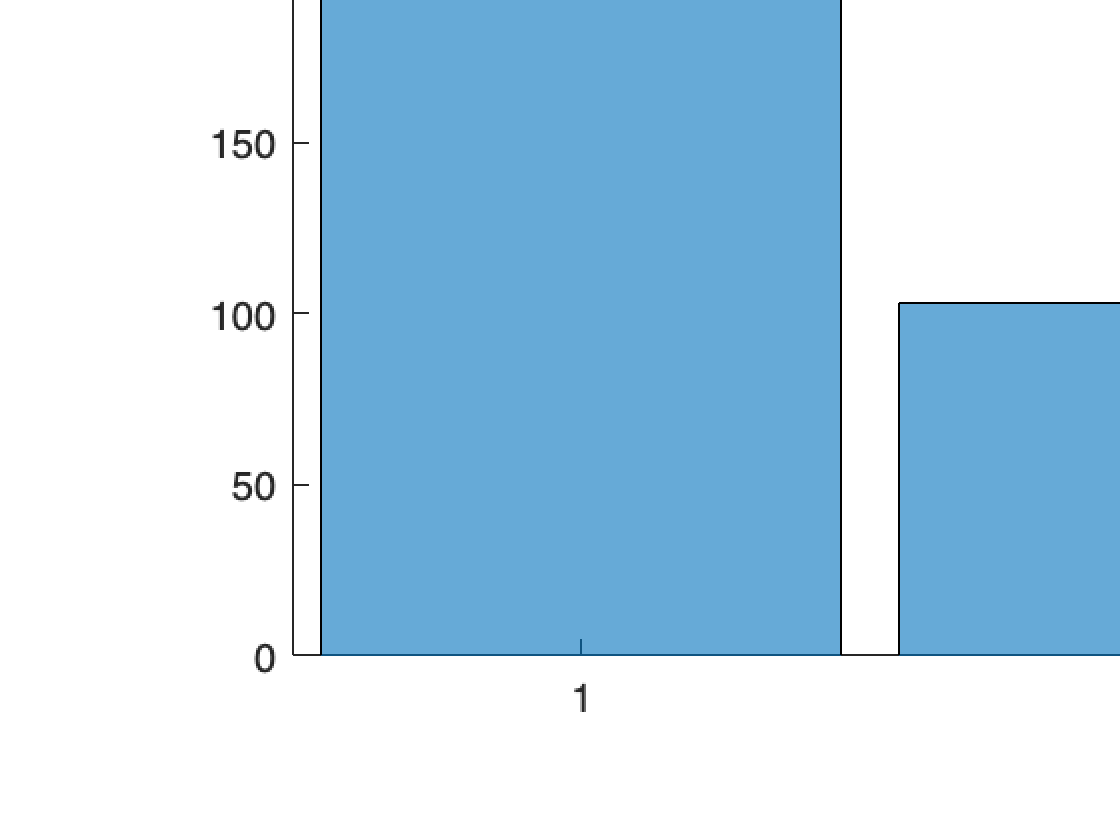

histogram(C6.Area)
title('Area')


summary(C6(:,"Investments"))

Variables:

    Investments: 544×1 categorical

        Values:

            1      544   
            2        0   
            3        0   



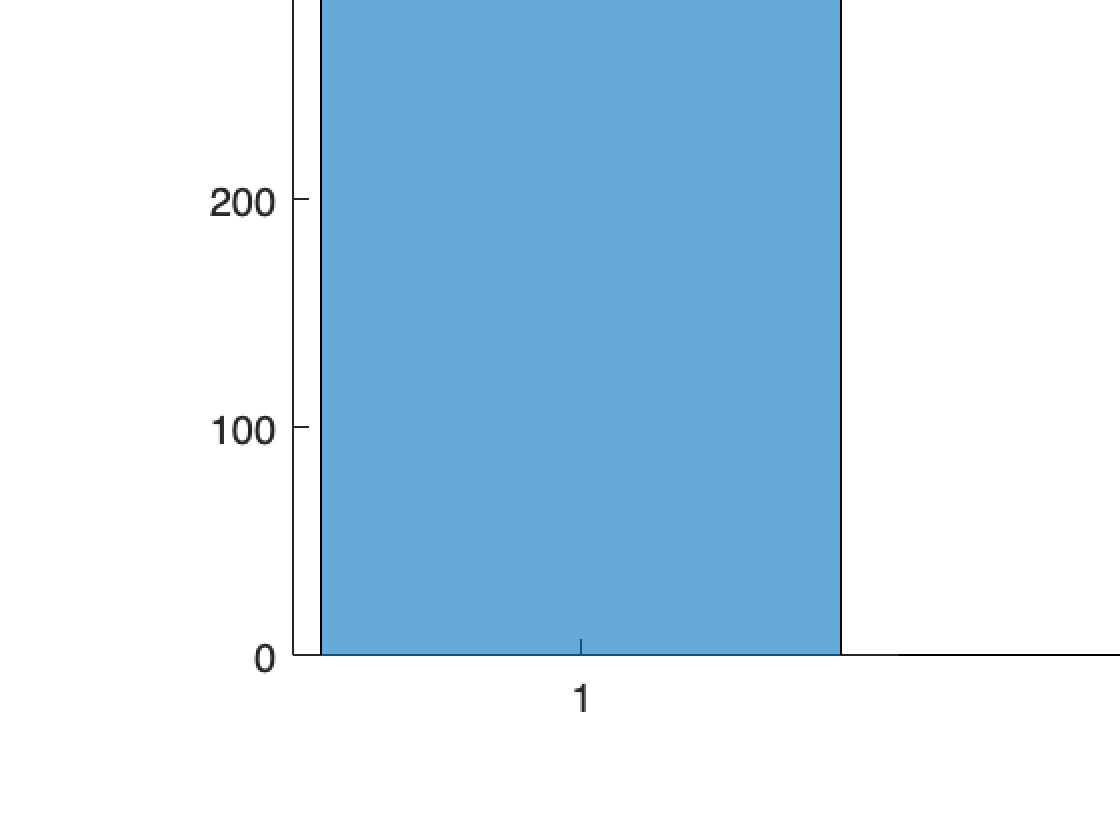

histogram(C6.Investments)
title(['Investments'])



summary(C6(:, "Income"))

Variables:

    Income: 544×1 double

        Values:

            Min       0.084561
            Median     0.59385
            Max          0.983



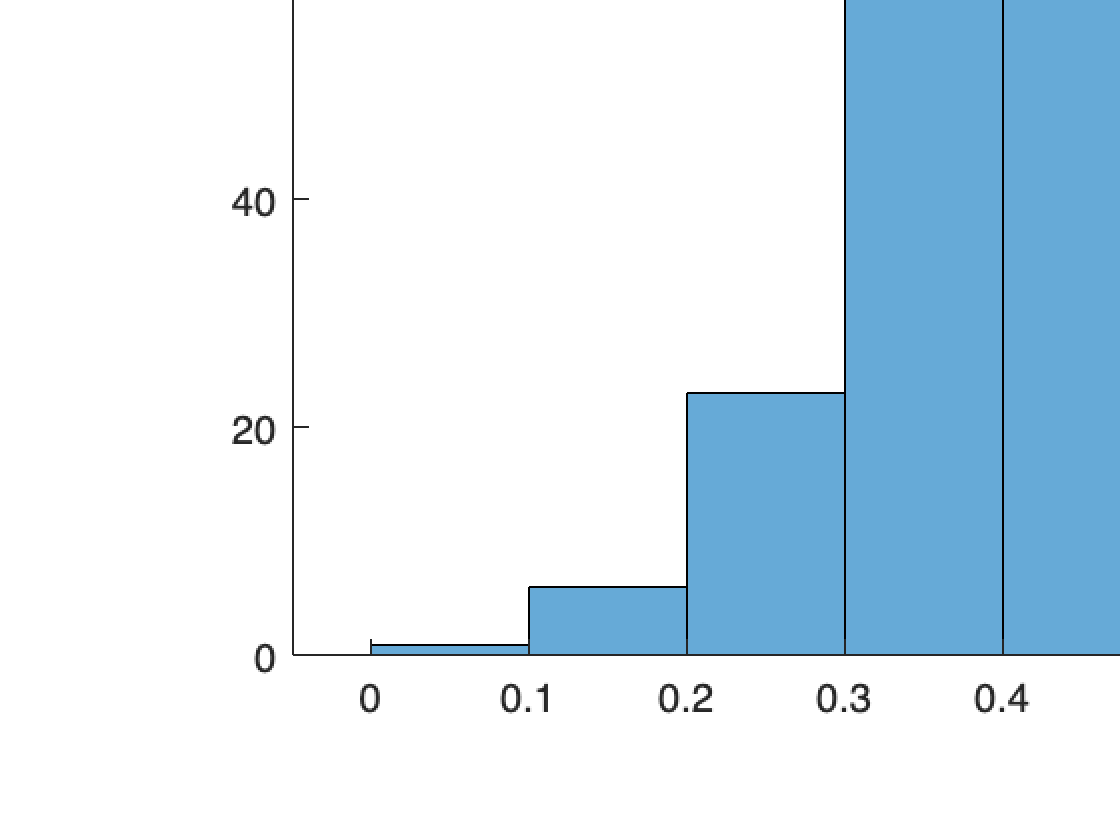

histogram(C6.Income)

mean(C6.Income)

ans = 0.5954


summary(C6(:, "Wealth"))

Variables:

    Wealth: 544×1 double

        Values:

            Min       0.10858 
            Median    0.60084 
            Max       0.96167 



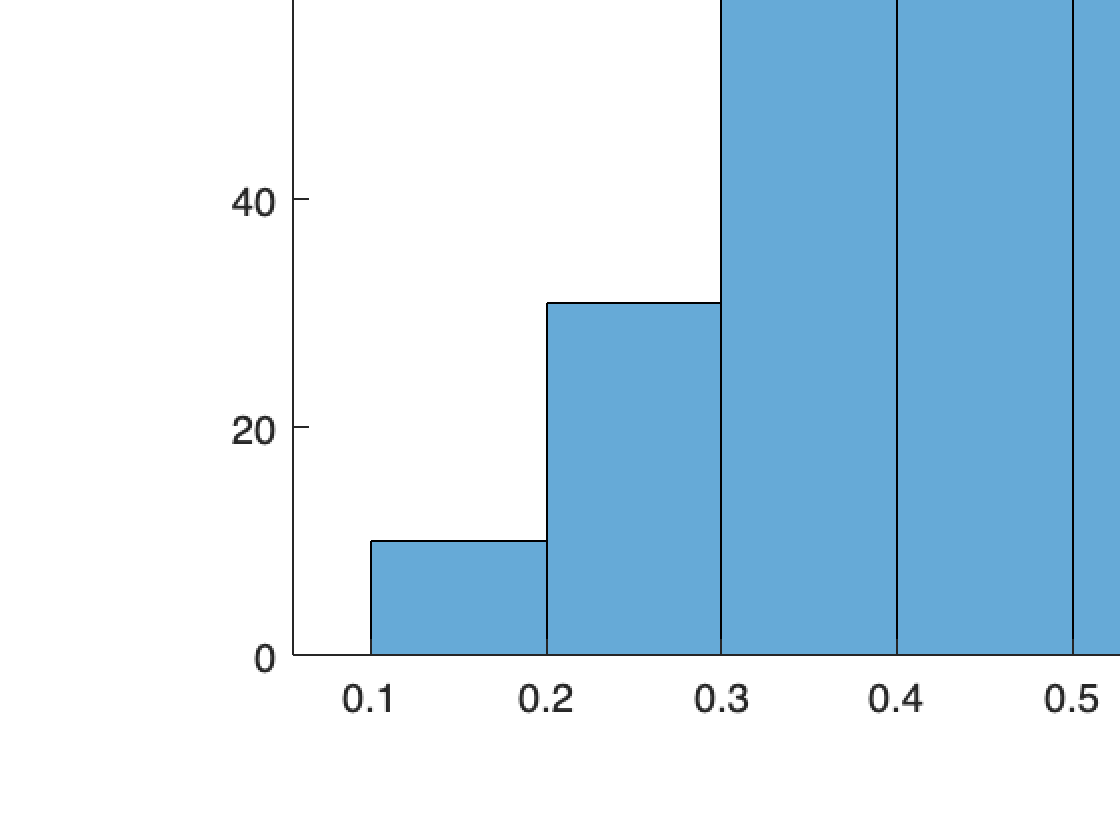

histogram(C6.Wealth)

mean(C6.Wealth)

ans = 0.5848


summary(C6(:, "Debt"))

Variables:

    Debt: 544×1 double

        Values:

            Min             0 
            Median    0.48832 
            Max       0.90866 



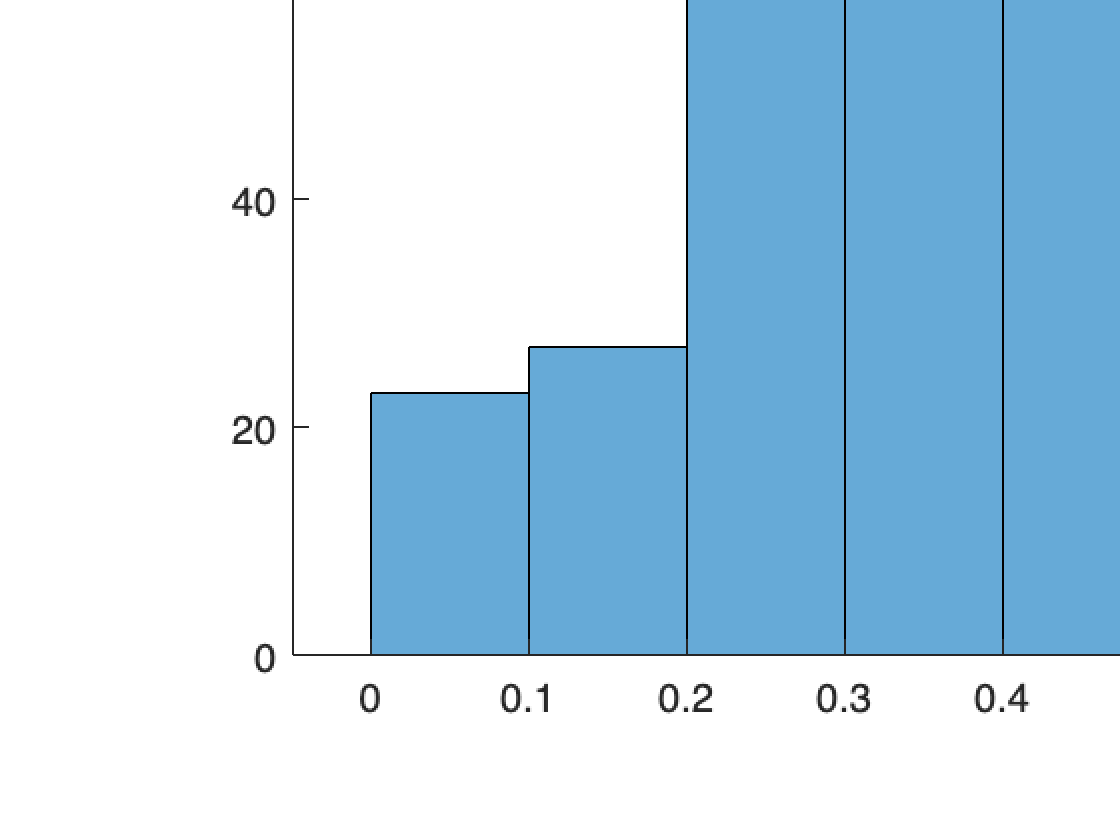

histogram(C6.Debt)

mean(C6.Debt)

ans = 0.4700


summary(C6(:, "FinEdu"))

Variables:

    FinEdu: 544×1 double

        Values:

            Min       0.064101
            Median     0.50851
            Max        0.94075



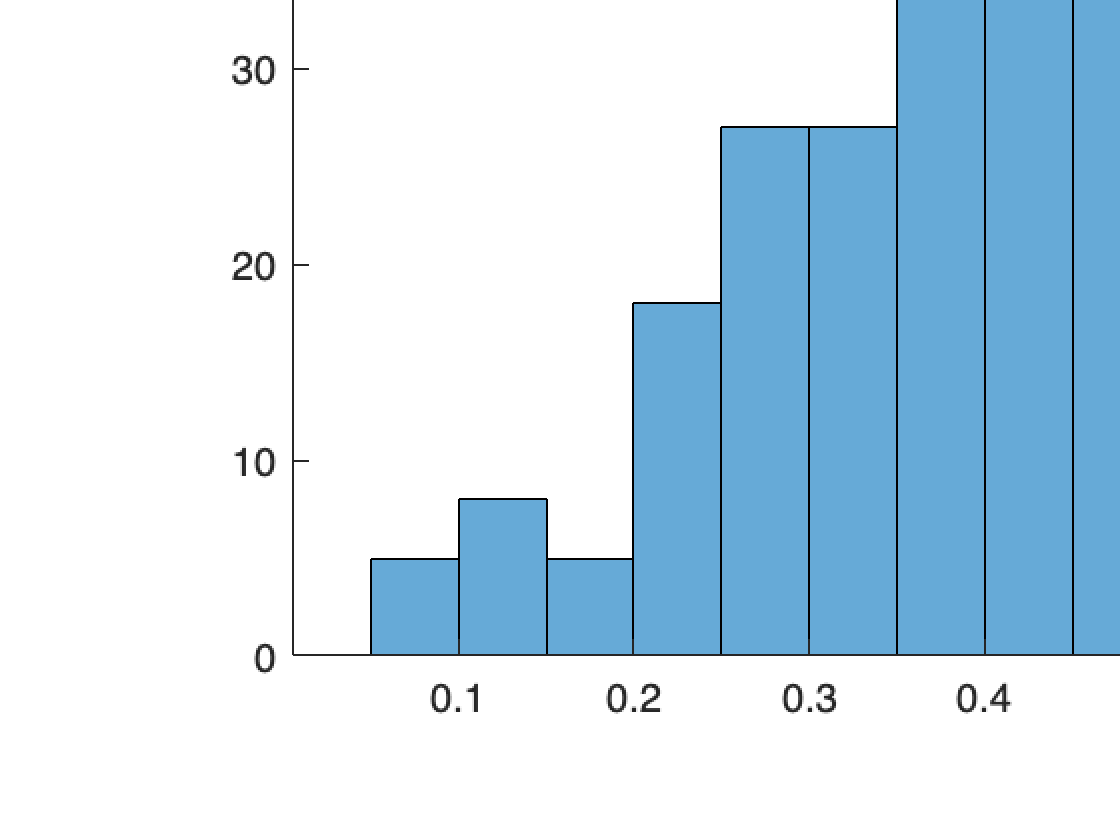

histogram(C6.FinEdu)

mean(C6.FinEdu)

ans = 0.5161


summary(C6(:, "ESG"))

Variables:

    ESG: 544×1 double

        Values:

            Min       0.061924
            Median     0.57235
            Max        0.98085



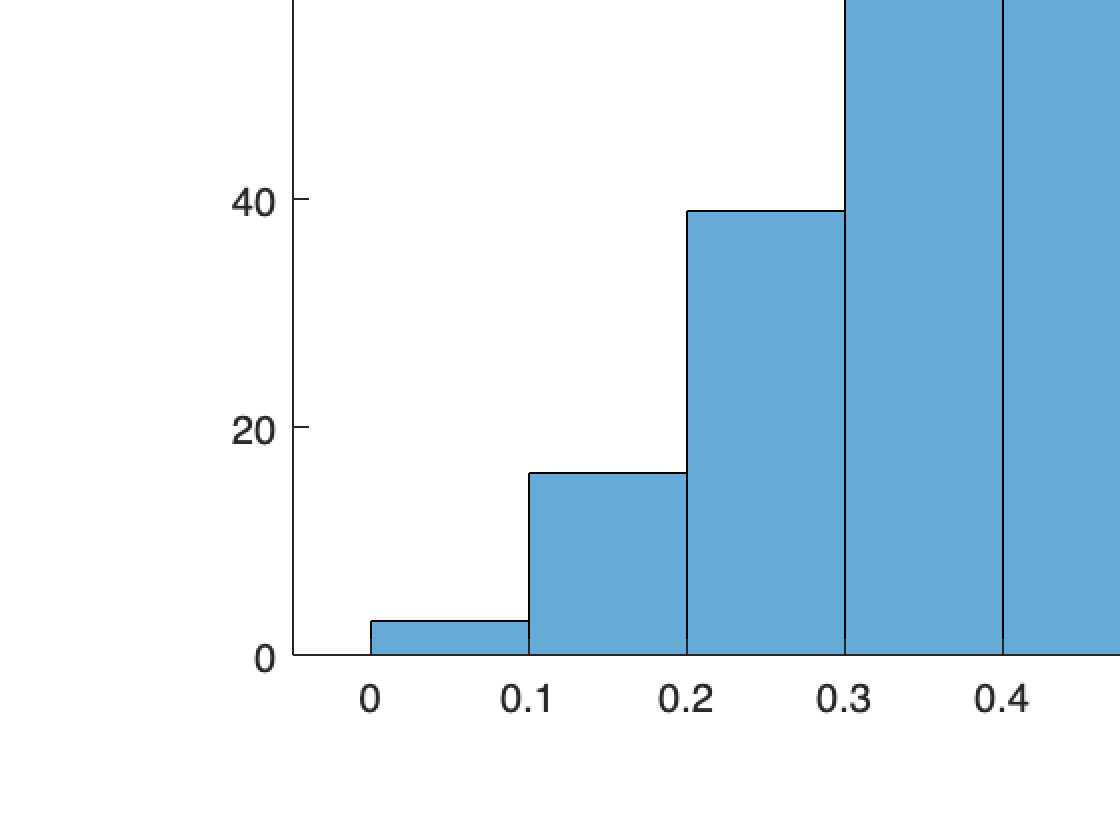

histogram(C6.ESG)

mean(C6.ESG)

ans = 0.5557


summary(C6(:, "Digital"))

Variables:

    Digital: 544×1 double

        Values:

            Min       0.024975
            Median     0.59024
            Max        0.97178



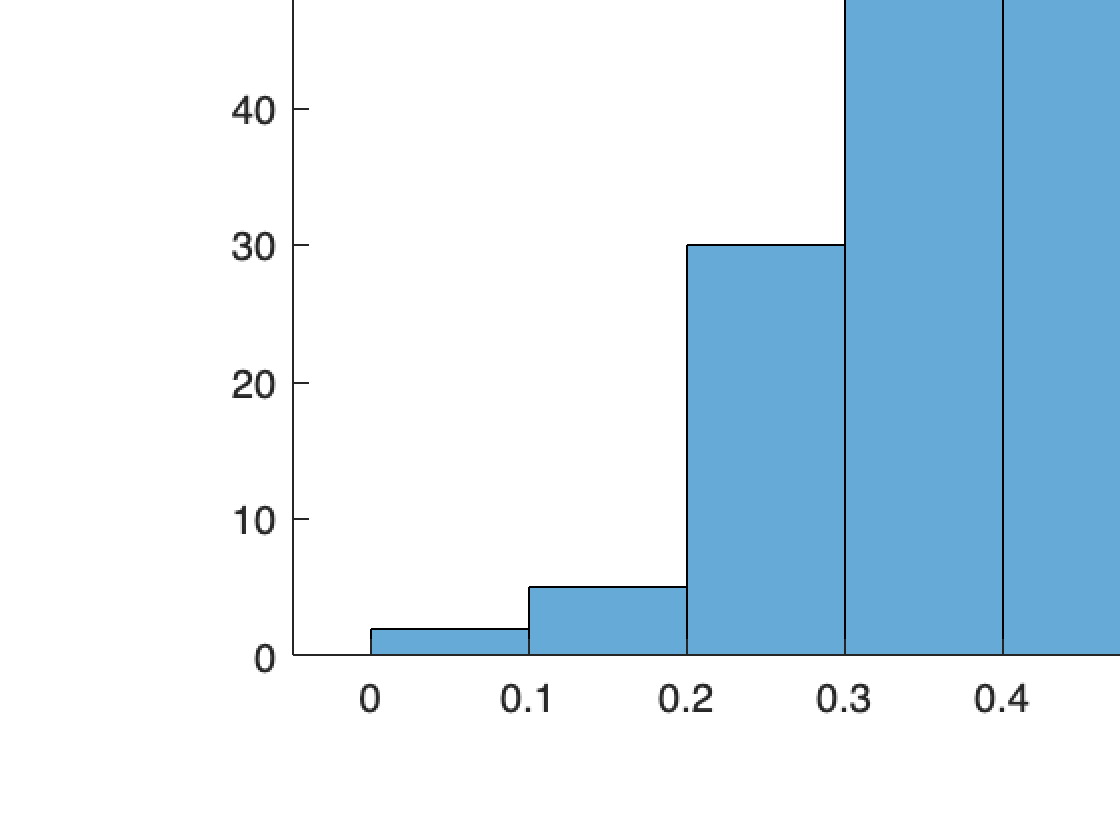

histogram(C6.Digital)

mean(C6.Digital)

ans = 0.5897


summary(C6(:, "BankFriend"))

Variables:

    BankFriend: 544×1 double

        Values:

            Min       0.13776 
            Median    0.59909 
            Max       0.96148 



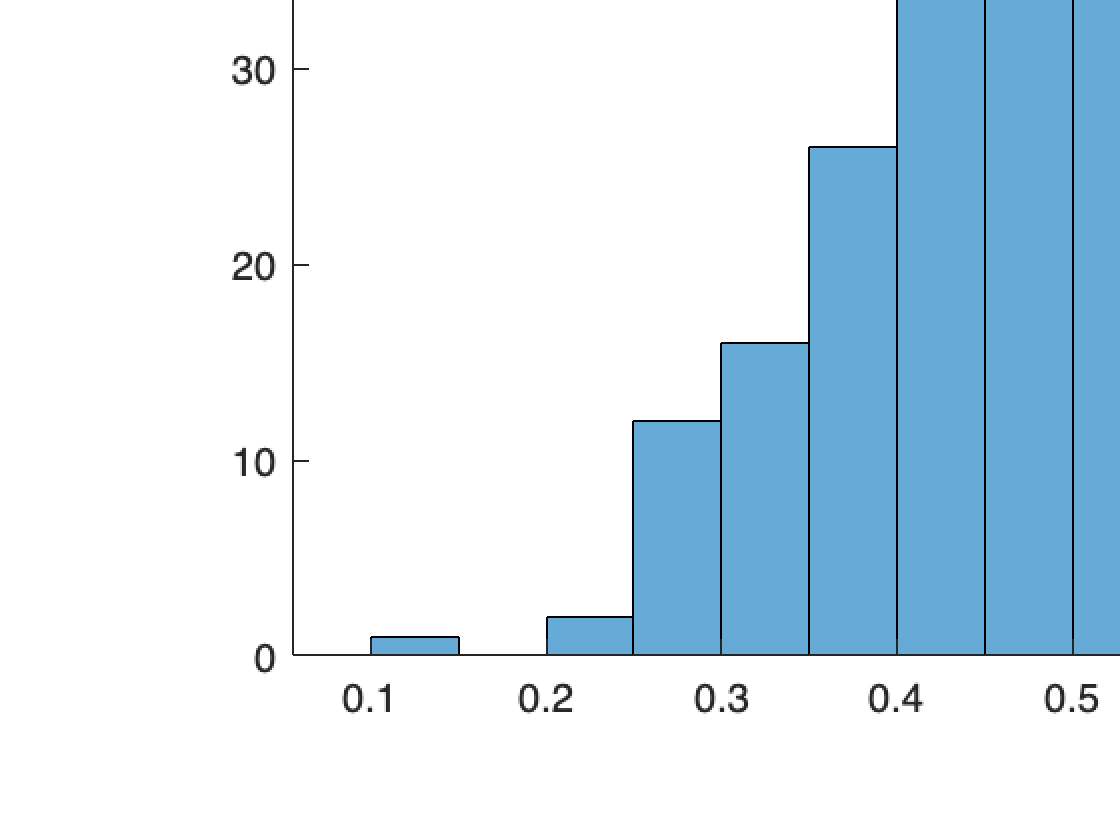

histogram(C6.BankFriend)

mean(C6.BankFriend)

ans = 0.5996


summary(C6(:, "LifeStyle"))

Variables:

    LifeStyle: 544×1 double

        Values:

            Min       0.043522
            Median     0.51597
            Max        0.99228



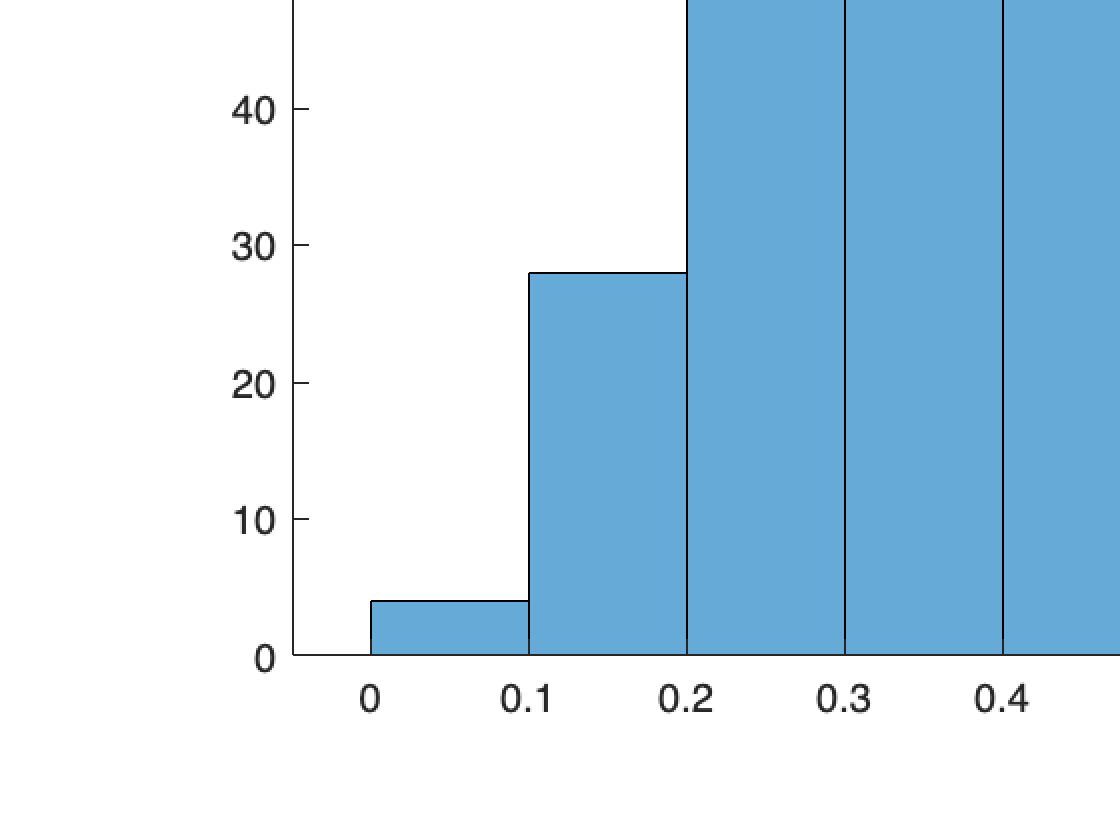

histogram(C6.LifeStyle)

mean(C6.LifeStyle)

ans = 0.5323


summary(C6(:, "Luxury"))

Variables:

    Luxury: 544×1 double

        Values:

            Min       0.013362
            Median       0.511
            Max        0.99319



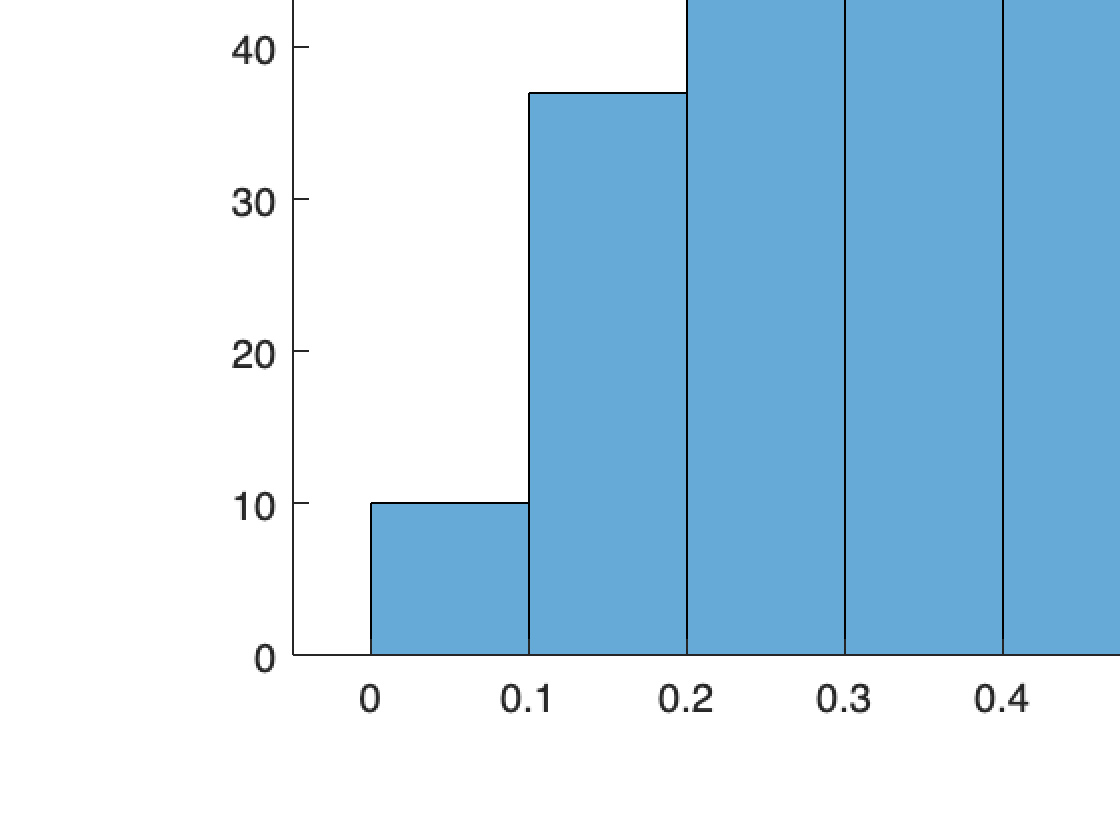

histogram(C6.Luxury)

mean(C6.Luxury)

ans = 0.5169


summary(C6(:, "Saving"))

Variables:

    Saving: 544×1 double

        Values:

            Min             0 
            Median    0.55428 
            Max       0.95029 



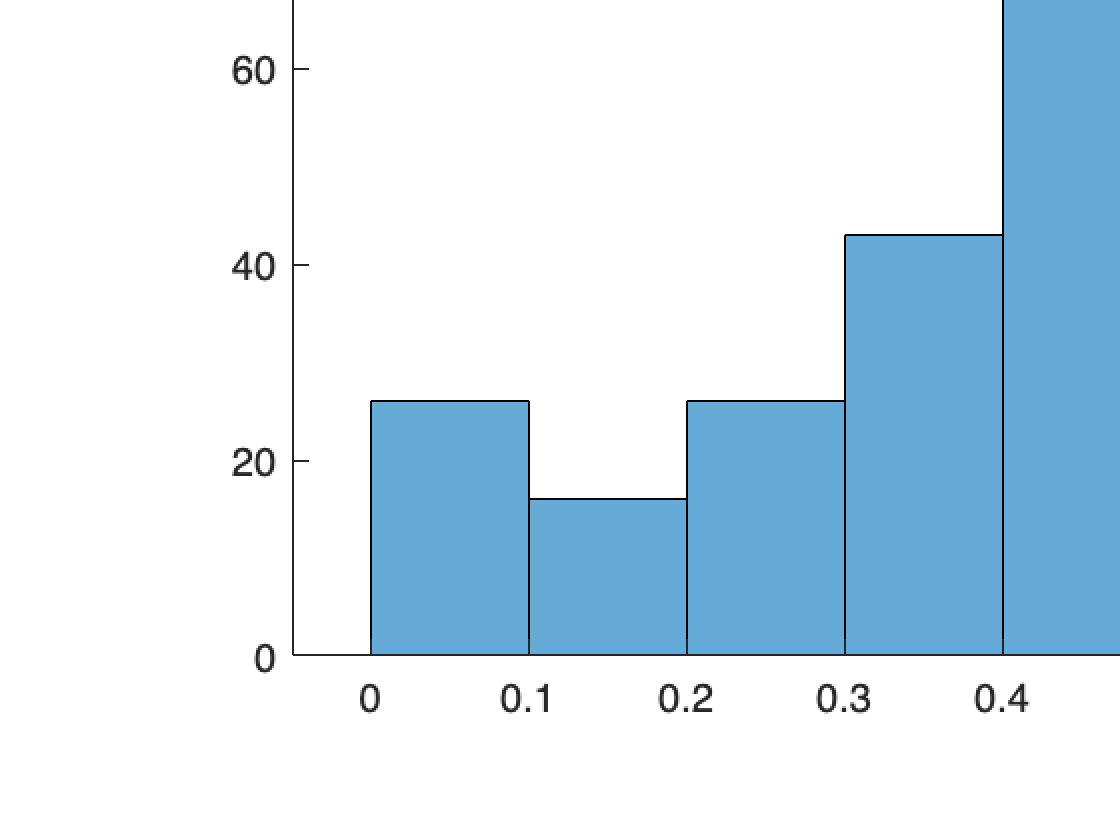

histogram(C6.Saving)

mean(C6.Saving)

ans = 0.5251

%IGNORE

C7 = BankClients(T9==7,:);
C7.ID

ans = 737×1 categorical array
     4 
     8 
     12 
     20 
     30 
     32 
     33 
     34 
     38 
     64 
     70 
     71 
     82 
     87 
     96 
     99 
     112 
     124 
     132 
     135 
     136 
     145 
     150 
     151 
     162 
     170 
     174 
     180 
     183 
     188 


% Frequency tables
tabulate(C7.Job)

  Value    Count   Percent
      1      133     18.05%
      2      245     33.24%
      3        6      0.81%
      4       11      1.49%
      5      342     46.40%


tabulate(C7.Area)

  Value    Count   Percent
      1      500     67.84%
      2      151     20.49%
      3       86     11.67%


tabulate(C7.CitySize)

  Value    Count   Percent
      1      301     40.84%
      2      349     47.35%
      3       87     11.80%


tabulate(C7.Investments)

  Value    Count   Percent
      1        0      0.00%
      2      737    100.00%
      3        0      0.00%



summary(C7(:,"Age"))

Variables:

    Age: 737×1 double

        Values:

            Min          64   
            Median       81   
            Max          95   



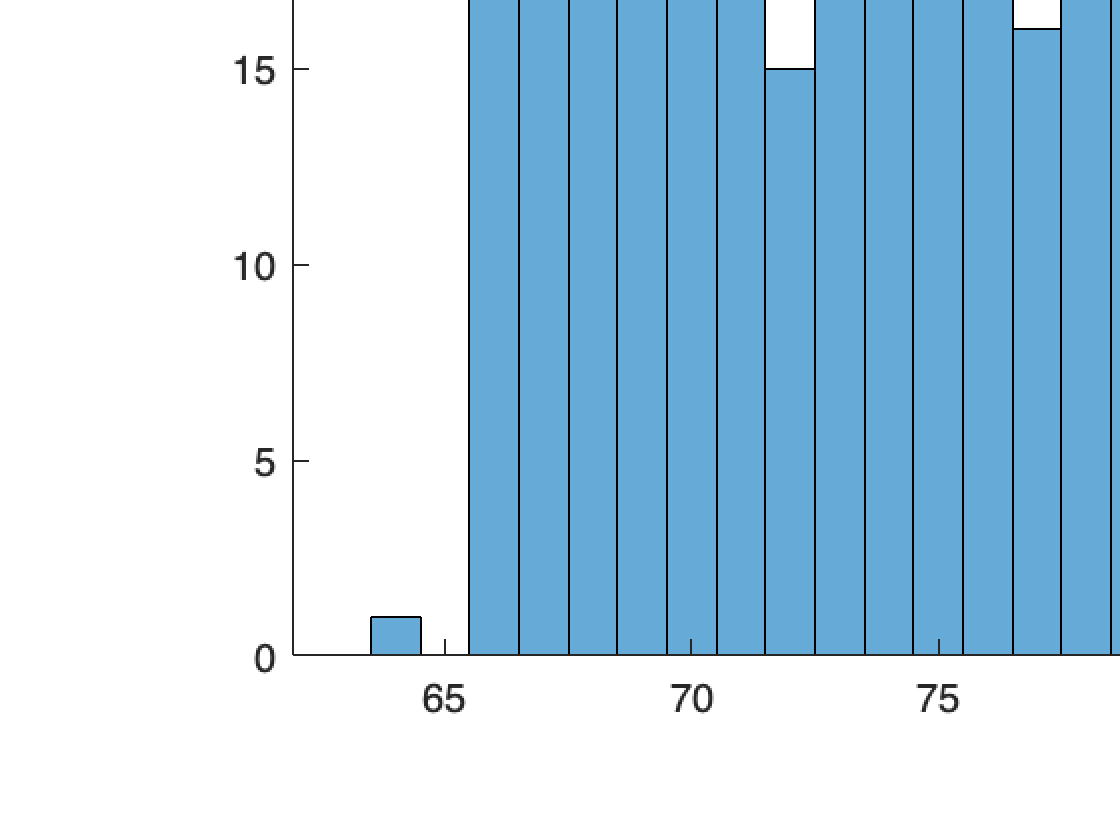

histogram(C7.Age)
title('Age')

mean(C7.Age)

ans = 81.0339


summary(C7(:,"Job"))

Variables:

    Job: 737×1 categorical

        Values:

            1      133   
            2      245   
            3        6   
            4       11   
            5      342   



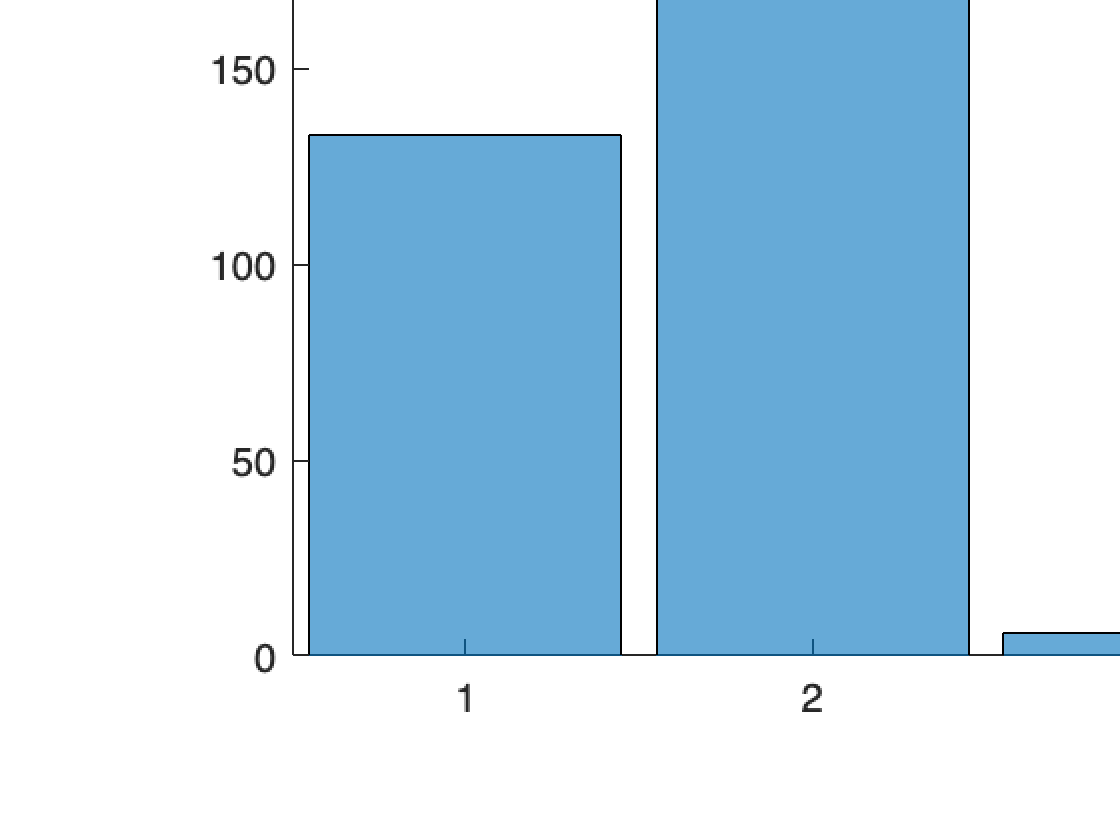

histogram(C7.Job)
title('Job')


summary(C7(:,"CitySize"))

Variables:

    CitySize: 737×1 categorical

        Values:

            1      301   
            2      349   
            3       87   



histogram(C7.CitySize)
title('City Size')



summary(C7(:,"Area"))

Variables:

    Area: 737×1 categorical

        Values:

            1      500   
            2      151   
            3       86   



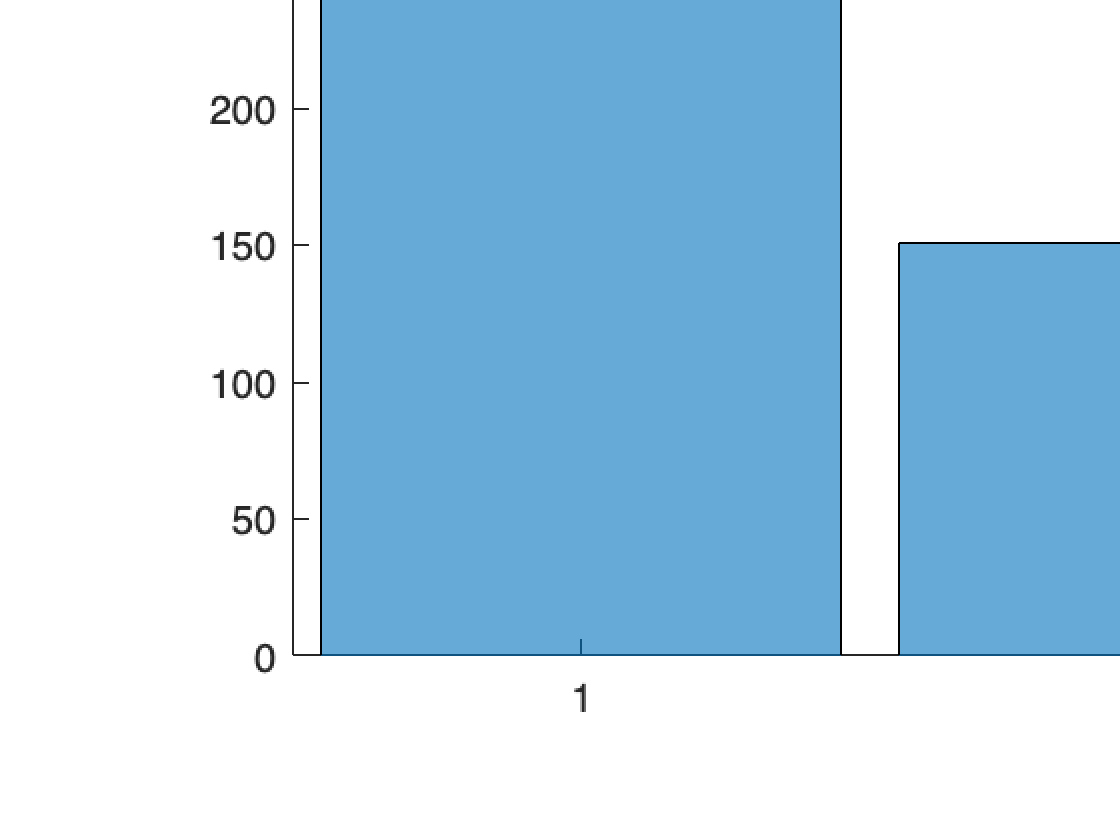

histogram(C7.Area)
title('Area')


summary(C7(:,"Investments"))

Variables:

    Investments: 737×1 categorical

        Values:

            1        0   
            2      737   
            3        0   



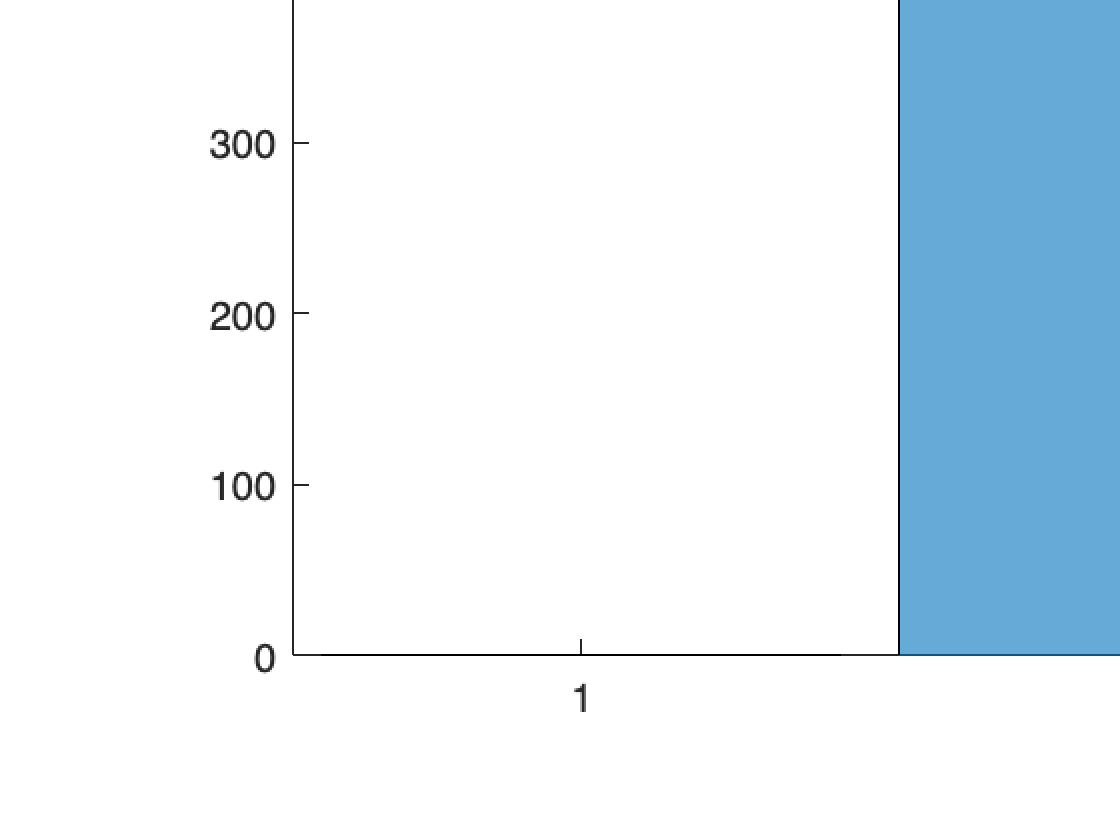

histogram(C7.Investments)
title(['Investments'])



summary(C7(:, "Income"))

Variables:

    Income: 737×1 double

        Values:

            Min             0 
            Median    0.44146 
            Max       0.97428 



histogram(C7.Income)

mean(C7.Income)

ans = 0.4605


summary(C7(:, "Wealth"))

Variables:

    Wealth: 737×1 double

        Values:

            Min             0 
            Median    0.44876 
            Max       0.98962 



histogram(C7.Wealth)

mean(C7.Wealth)

ans = 0.4645


summary(C7(:, "Debt"))

Variables:

    Debt: 737×1 double

        Values:

            Min             0 
            Median    0.17158 
            Max        0.8881 



histogram(C7.Debt)

mean(C7.Debt)

ans = 0.2557


summary(C7(:, "FinEdu"))

Variables:

    FinEdu: 737×1 double

        Values:

            Min             0 
            Median    0.39029 
            Max       0.90561 



histogram(C7.FinEdu)

mean(C7.FinEdu)

ans = 0.4026


summary(C7(:, "ESG"))

Variables:

    ESG: 737×1 double

        Values:

            Min       0.06868 
            Median    0.60912 
            Max       0.92833 



histogram(C7.ESG)

mean(C7.ESG)

ans = 0.5974


summary(C7(:, "Digital"))

Variables:

    Digital: 737×1 double

        Values:

            Min             0 
            Median    0.36057 
            Max       0.95951 



histogram(C7.Digital)

mean(C7.Digital)

ans = 0.3837


summary(C7(:, "BankFriend"))

Variables:

    BankFriend: 737×1 double

        Values:

            Min       0.18609 
            Median    0.62504 
            Max       0.96527 



histogram(C7.BankFriend)

mean(C7.BankFriend)

ans = 0.6175


summary(C7(:, "LifeStyle"))

Variables:

    LifeStyle: 737×1 double

        Values:

            Min             0 
            Median    0.28617 
            Max        0.9018 



histogram(C7.LifeStyle)

mean(C7.LifeStyle)

ans = 0.3217


summary(C7(:, "Luxury"))

Variables:

    Luxury: 737×1 double

        Values:

            Min             0 
            Median    0.27392 
            Max       0.99591 



histogram(C7.Luxury)

mean(C7.Luxury)

ans = 0.3308


summary(C7(:, "Saving"))

Variables:

    Saving: 737×1 double

        Values:

            Min       0.004191
            Median     0.38924
            Max        0.92859



histogram(C7.Saving)

mean(C7.Saving)

ans = 0.4158

%IGNORE
C8 = BankClients(T8==8,:);
C8.ID

ans = 544×1 categorical array
     1 
     7 
     14 
     25 
     27 
     28 
     37 
     47 
     59 
     60 
     69 
     85 
     101 
     113 
     122 
     127 
     130 
     134 
     147 
     159 
     178 
     187 
     206 
     211 
     219 
     223 
     225 
     228 
     232 
     235 


% Frequency tables
tabulate(C8.Job)

  Value    Count   Percent
      1       85     15.62%
      2      399     73.35%
      3       19      3.49%
      4       18      3.31%
      5       23      4.23%


tabulate(C8.Area)

  Value    Count   Percent
      1      375     68.93%
      2      103     18.93%
      3       66     12.13%


tabulate(C8.CitySize)

  Value    Count   Percent
      1      186     34.19%
      2      214     39.34%
      3      144     26.47%


tabulate(C8.Investments)

  Value    Count   Percent
      1      544    100.00%
      2        0      0.00%
      3        0      0.00%



summary(C8(:,"Age"))

Variables:

    Age: 544×1 double

        Values:

            Min           19  
            Median      36.5  
            Max           57  



histogram(C8.Age)
title('Age')

mean(C8.Age)

ans = 36.8989


summary(C8(:,"Job"))

Variables:

    Job: 544×1 categorical

        Values:

            1       85   
            2      399   
            3       19   
            4       18   
            5       23   



histogram(C8.Job)
title('Job')


summary(C8(:,"CitySize"))

Variables:

    CitySize: 544×1 categorical

        Values:

            1      186   
            2      214   
            3      144   



histogram(C8.CitySize)
title('City Size')



summary(C8(:,"Area"))

Variables:

    Area: 544×1 categorical

        Values:

            1      375   
            2      103   
            3       66   



histogram(C8.Area)
title('Area')


summary(C8(:,"Investments"))

Variables:

    Investments: 544×1 categorical

        Values:

            1      544   
            2        0   
            3        0   



histogram(C8.Investments)
title(['Investments'])



summary(C8(:, "Income"))

Variables:

    Income: 544×1 double

        Values:

            Min       0.084561
            Median     0.59385
            Max          0.983



histogram(C8.Income)

mean(C8.Income)

ans = 0.5954


summary(C8(:, "Wealth"))

Variables:

    Wealth: 544×1 double

        Values:

            Min       0.10858 
            Median    0.60084 
            Max       0.96167 



histogram(C8.Wealth)

mean(C8.Wealth)

ans = 0.5848


summary(C8(:, "Debt"))

Variables:

    Debt: 544×1 double

        Values:

            Min             0 
            Median    0.48832 
            Max       0.90866 



histogram(C8.Debt)

mean(C8.Debt)

ans = 0.4700


summary(C8(:, "FinEdu"))

Variables:

    FinEdu: 544×1 double

        Values:

            Min       0.064101
            Median     0.50851
            Max        0.94075



histogram(C8.FinEdu)

mean(C8.FinEdu)

ans = 0.5161


summary(C8(:, "ESG"))

Variables:

    ESG: 544×1 double

        Values:

            Min       0.061924
            Median     0.57235
            Max        0.98085



histogram(C8.ESG)

mean(C8.ESG)

ans = 0.5557


summary(C8(:, "Digital"))

Variables:

    Digital: 544×1 double

        Values:

            Min       0.024975
            Median     0.59024
            Max        0.97178



histogram(C8.Digital)

mean(C8.Digital)

ans = 0.5897


summary(C8(:, "BankFriend"))

Variables:

    BankFriend: 544×1 double

        Values:

            Min       0.13776 
            Median    0.59909 
            Max       0.96148 



histogram(C8.BankFriend)

mean(C8.BankFriend)

ans = 0.5996


summary(C8(:, "LifeStyle"))

Variables:

    LifeStyle: 544×1 double

        Values:

            Min       0.043522
            Median     0.51597
            Max        0.99228



histogram(C8.LifeStyle)

mean(C8.LifeStyle)

ans = 0.5323


summary(C8(:, "Luxury"))

Variables:

    Luxury: 544×1 double

        Values:

            Min       0.013362
            Median       0.511
            Max        0.99319



histogram(C8.Luxury)

mean(C8.Luxury)

ans = 0.5169


summary(C8(:, "Saving"))

Variables:

    Saving: 544×1 double

        Values:

            Min             0 
            Median    0.55428 
            Max       0.95029 



histogram(C8.Saving)

mean(C8.Saving)

ans = 0.5251

% next step tirare fuori l'indice dei 6 negli ultimi due cluster
% provare ad escluderli e rivedere come clusterizza il resto dei dati

%PARTE 2 scelta prodotto




## Next Best Action: recommending products

Now we generate the personalized recommendation for the Accumulation products, that is, Products.Type==1.

I adopt the following rules, for each client:

- **matching product type and client need (predicted using the ensemble model)**;

- **matching product risk and client risk**;

- **suggesting one single product** - alternatively we might suggest **a list of products**, ranked based on their fit to each client profile (the first approach, being "straight", would be preferable for a robo-advisory service or a sales network that needs a lot of support, the latter is more suitable for a network of expert financial consultants who just need a little decision support).

For simplicity and to continue the example, we do that for the clients in the test set (but the rules work for an arbitrary set of clients).

### Retrieving data

Retrieving IDs and risk propensities for the client in the test set, and products (using the variable idxPermutation).

% Define the Excel file path 
%excel_file = 'Products.xlsx';

% Read the data from the Excel file into a table
%Products = readtable(excel_file);

% Read the data from the Excel file
%Products = xlsread(excel_file);

% Define the MAT file name
%Products_file = 'Products.mat';
Products=load('/Users/Lorenzo/Desktop/Tesi/Functions&Data/Products.mat');
Products=Products.Products;
% Save the data into a MAT file
%save(Products_file, 'Products');

% Read the data from the Excel file into a table
%Products = readtable(excel_file);
%Products(5,3)=0.9100
Products = array2table(Products);
new_column_names = {'ID', 'Type', 'Risk'};

% Assign the new column names to the table
Products.Properties.VariableNames = new_column_names;


### Creating the personalized recommandations:

- The suitable products are those with a risk level below the client risk tolerance;

- Among those products, we select the one with the highest risk level (sure, we might do otherwise, it depends on the situation)

%PROVO A CALCOLARE IL PRODOTTO PER TUTTI I CLIENTI INSIEME


%ACCUMULATION CLIENTS
% Retrieving clients IDs
ClientID_full = BankClients.ID
category3=categorical({'3'})
TargetClientID_full = ClientID_full(BankClients.Investments==category3); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities

ClientID_full = 5000×1 categorical array
     1 
     2 
     3 
     4 
     5 
     6 
     7 
     8 
     9 
     10 
     11 
     12 
     13 
     14 
     15 
     16 
     17 
     18 
     19 
     20 
     21 
     22 
     23 
     24 
     25 
     26 
     27 
     28 
     29 
     30 


ClientRiskProp_full=0.2*BankClients.Income+0.2*BankClients.Saving+0.1*BankClients.Wealth+0.2*BankClients.FinEdu+0.1*(BankClients.Age/100)+0.2*(1./BankClients.Debt)

category2 = categorical
     2 


%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

TargetClientRiskPropensity_full = ClientRiskProp_full(BankClients.Investments==category3); 


ClientRiskProp_full = 1.0e+03 *

    0.0012
    0.0009
    0.0010
    0.0008
    0.0008
    0.0008
    0.0026
    0.0009
    0.0007
    0.0009


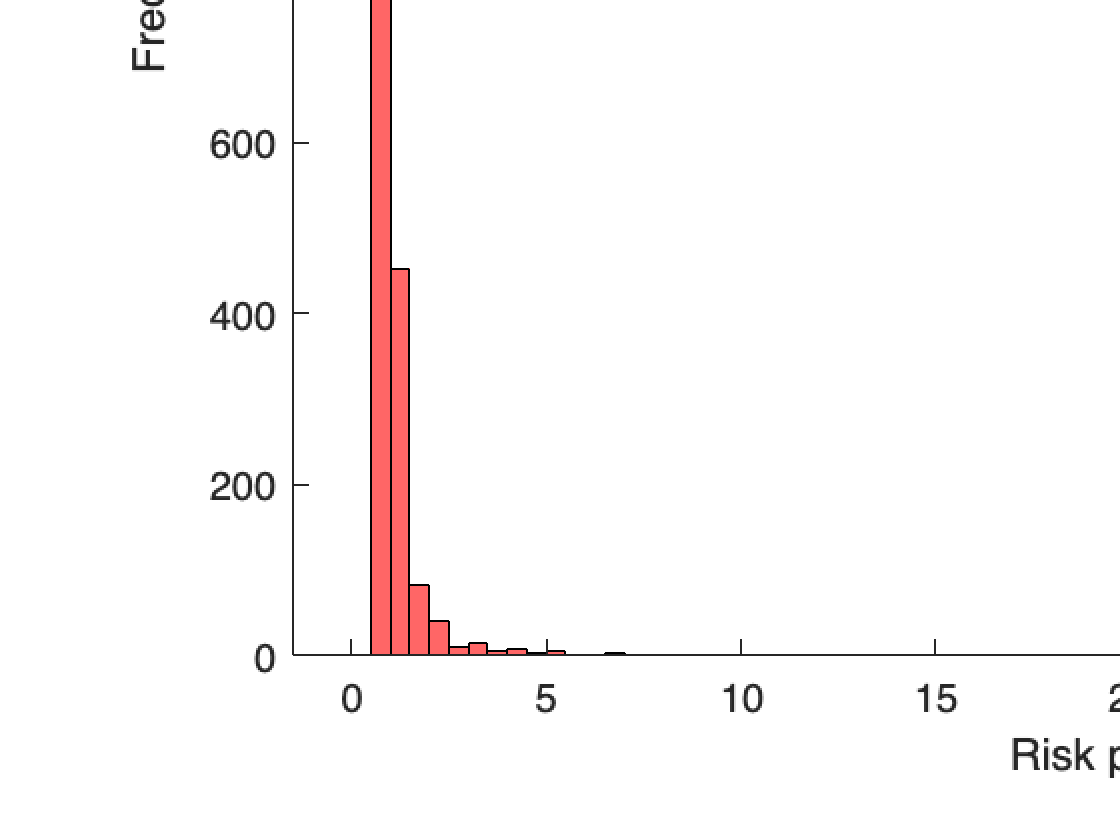

% Let's have a look at these incomes...
figure
histogram(TargetClientRiskPropensity_full, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


AccumulationProducts = Products(Products.Type == 1,:)


NBA_ACProduct_full = double([]);

RecommendedRiskLevel_full = [];

AccumulationProducts = 7×3 table
    ID    Type    Risk
    __    ____    ____

     1     1      0.55
     5     1      0.41
     6     1      0.36
     7     1      0.75
     8     1      0.48
     9     1      0.27
    11     1      0.88


minRisk_full = min(AccumulationProducts.Risk);

for i = 1: size(TargetClientRiskPropensity_full, 1)
    if TargetClientRiskPropensity_full(i)> minRisk_full
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<TargetClientRiskPropensity_full(i)));
        NBA_ACProduct_full = [NBA_ACProduct_full; categorical(AccumulationProducts.ID(AccumulationProducts.Risk== M))];
    else
        % no suitable product in the product range
        NBA_ACProduct_full = [NBA_ACProduct_full; '0'];
        M = 0;
    end
    RecommendedRiskLevel_full = [RecommendedRiskLevel_full; M];
end

% recommendations
CatID_full = categorical(TargetClientID_full);
NBA_full = [CatID_full NBA_ACProduct_full];

figure
c = linspace(0,1,length(TargetClientRiskPropensity_full));
scatter(TargetClientRiskPropensity_full, RecommendedRiskLevel_full, [], c, 'filled')

Error using categorical/horzcat
Dimensions of arrays being concatenated are not consistent.

title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')



%SAME BUT FOR THE ONES WITH INCOME INVESTMENTS

% Retrieving clients IDs
IncomeClientID_full = BankClients.ID
category2=categorical({'2'})
IncomeClientID_full = IncomeClientID_full(BankClients.Investments==category2); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
IncomeClientRiskProp_full=0.2*BankClients.Income+0.2*BankClients.Saving+0.1*BankClients.Wealth+0.2*BankClients.FinEdu+0.1*(BankClients.Age/100)+0.2*(1./BankClients.Debt)

IncomeClientID_full = 5000×1 categorical array
     1 
     2 
     3 
     4 
     5 
     6 
     7 
     8 
     9 
     10 
     11 
     12 
     13 
     14 
     15 
     16 
     17 
     18 
     19 
     20 
     21 
     22 
     23 
     24 
     25 
     26 
     27 
     28 
     29 
     30 


%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

category2 = categorical
     2 



IncomeClientRiskPropensity_full = IncomeClientRiskProp_full(BankClients.Investments==category2); 

% Let's have a look at these incomes...

IncomeClientRiskProp_full = 1.0e+03 *

    0.0012
    0.0009
    0.0010
    0.0008
    0.0008
    0.0008
    0.0026
    0.0009
    0.0007
    0.0009


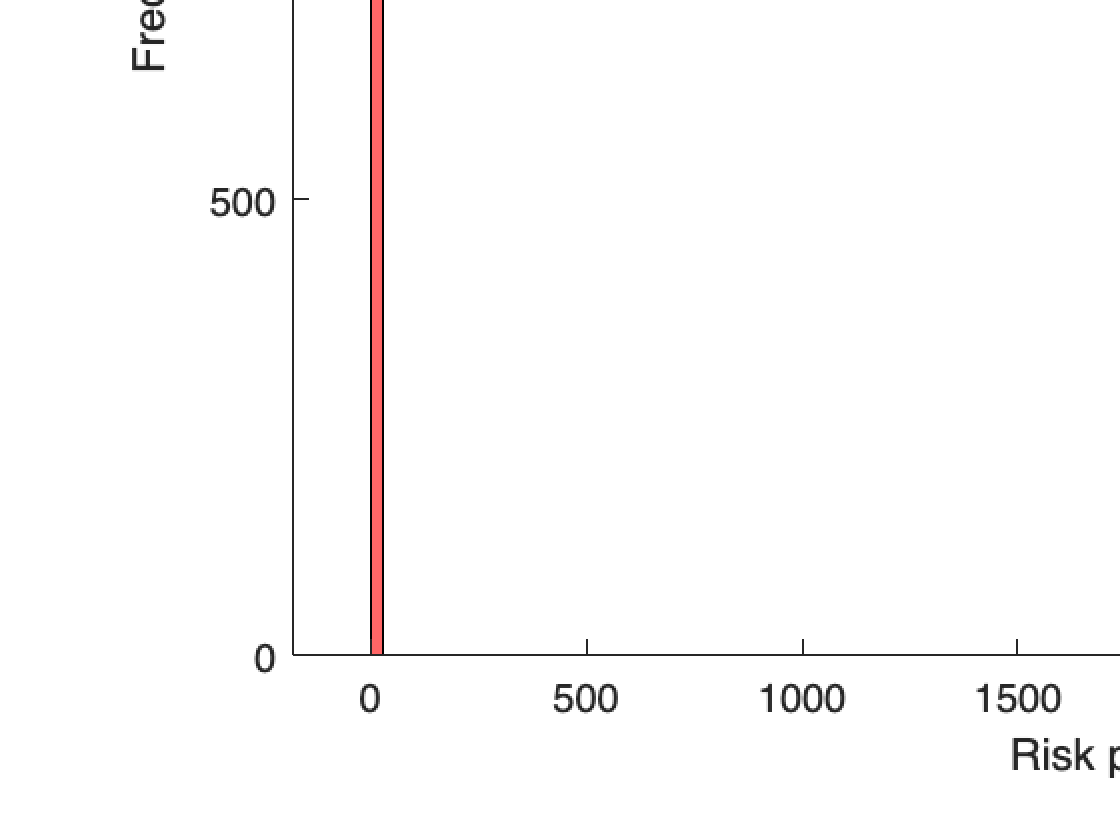

figure
histogram(IncomeClientRiskPropensity_full, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


IncomeProducts = Products(Products.Type == 0,:)

NBA_IProduct_full = [];

RecommendedRiskLevelIN_full = [];
minRiskIN_full = min(IncomeProducts.Risk);


IncomeProducts = 4×3 table
    ID    Type    Risk
    __    ____    ____

     2     0       0.3
     3     0      0.12
     4     0      0.44
    10     0      0.13


for i = 1: size(IncomeClientRiskPropensity_full, 1)
    if IncomeClientRiskPropensity_full(i)> minRiskIN_full
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<IncomeClientRiskPropensity_full(i)));
        NBA_IProduct_full = [NBA_IProduct_full; categorical(IncomeProducts.ID(IncomeProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_IProduct_full = [NBA_IProduct_full; '0'];
        M = 0;
    end
    RecommendedRiskLevelIN_full = [RecommendedRiskLevelIN_full; M];
end

% recommendations
IncomeCatID_full = categorical(IncomeClientID_full);
NBAIncome_full = [IncomeCatID_full NBA_IProduct_full];

figure
c = linspace(0,1,length(IncomeClientRiskPropensity_full));
scatter(IncomeClientRiskPropensity_full, RecommendedRiskLevelIN_full, [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')

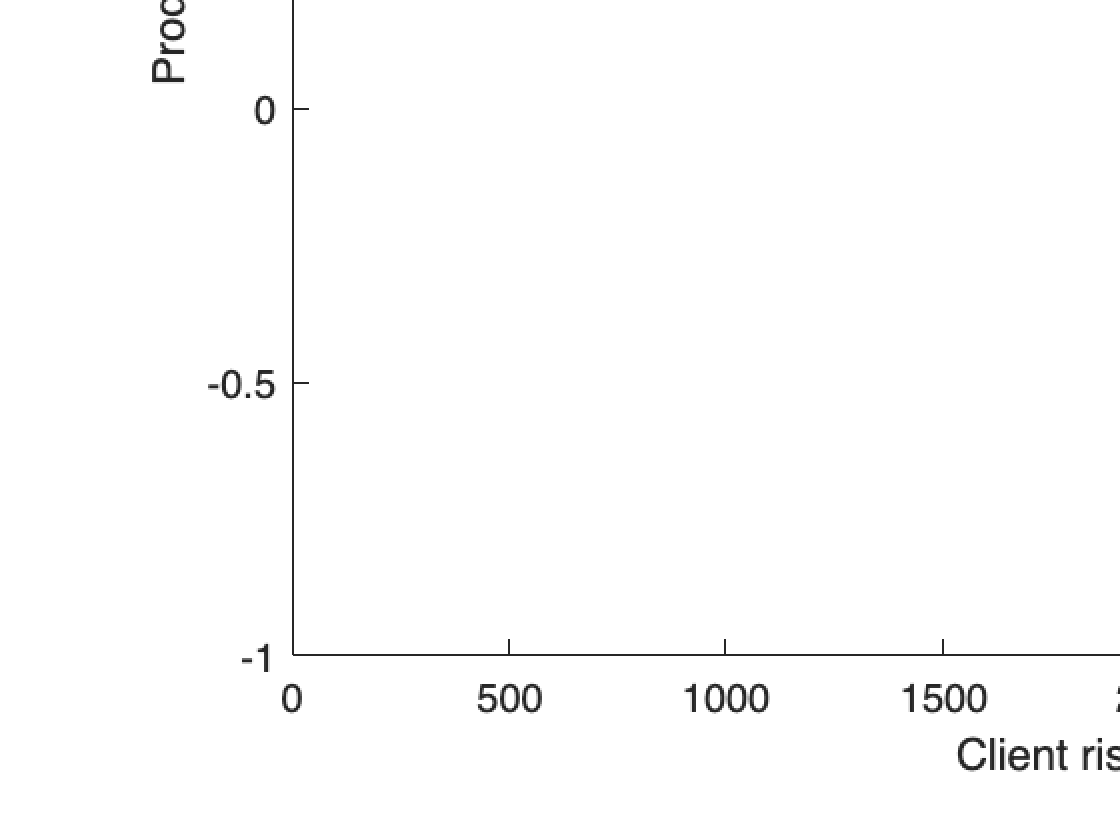

%can avoid running
%can be done better

%diagramma risk index
labels = {'Income', 'Wealth', 'Savings', 'Debt', 'Financial Education', 'Age'};

sizes = [20, 10, 20, 20, 20, 10];

% Creare il diagramma a torta
pie(sizes, labels);

% Aggiungere un titolo
title('Composition of the risk index');

% Aggiungere una legenda
legend(labels, 'Location', 'best')

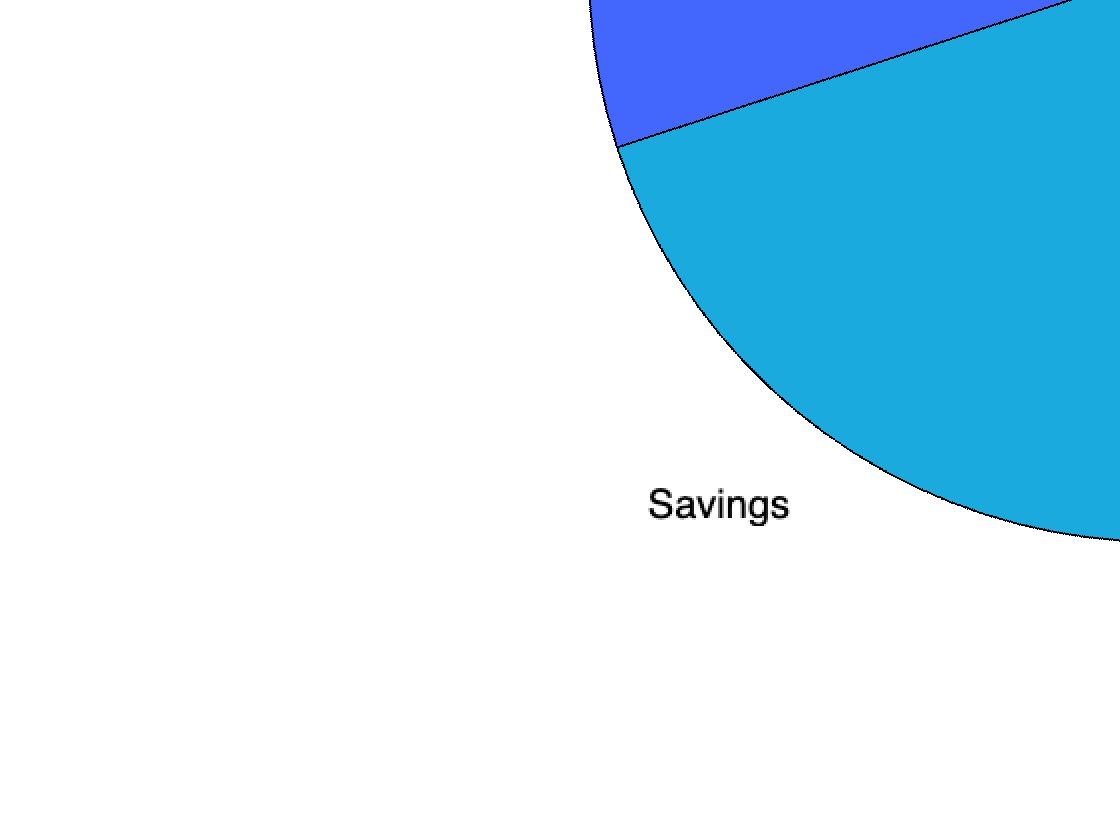

%SAME BUT ONLY FOR EACH CLUSTER CLIENTS

%CLUSTER 1 ACCUMULATION

ClientID_C1 = C1.ID


category2=categorical({'2'})
C1ClientID = ClientID_C1(C1.Investments==category2); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
C1RiskProp_full=0.2*C1.Income+0.2*C1.Saving+0.1*C1.Wealth+0.2*C1.FinEdu+0.1*(C1.Age/100)+0.2*(1./C1.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

ClientID_C1 = 737×1 categorical array
     4 
     8 
     12 
     20 
     30 
     32 
     33 
     34 
     38 
     64 
     70 
     71 
     82 
     87 
     96 
     99 
     112 
     124 
     132 
     135 
     136 
     145 
     150 
     151 
     162 
     170 
     174 
     180 
     183 
     188 



C1ClientRiskPropensity = C1RiskProp_full(C1.Investments==category2); 

category2 = categorical
     2 



% Let's have a look at these incomes...
figure
histogram(C1ClientRiskPropensity, 'FaceColor', 'r')

C1RiskProp_full = 1.0e+03 *

    0.0008
    0.0009
    0.0006
    0.0076
    0.0013
    0.0009
    0.0014
    0.0017
    0.0017
    0.0016


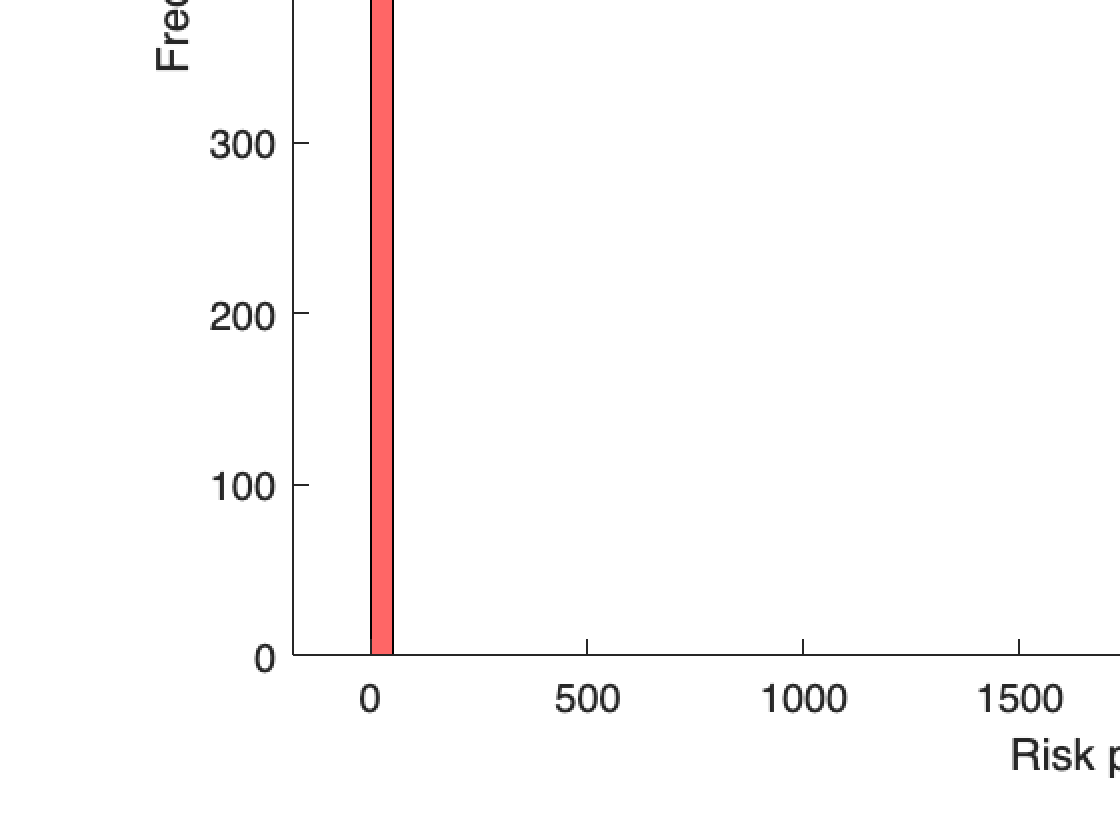

title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


AccumulationProducts = Products(Products.Type == 1,:)

NBA_C1P = [];
NBA_C1Product= double(NBA_C1P);
RecommendedRiskLevel_C1 = [];

minRisk_C1 = min(AccumulationProducts.Risk);

for i = 1: size(C1ClientRiskPropensity, 1)

AccumulationProducts = 7×3 table
    ID    Type    Risk
    __    ____    ____

     1     1      0.55
     5     1      0.41
     6     1      0.36
     7     1      0.75
     8     1      0.48
     9     1      0.27
    11     1      0.88


    if C1ClientRiskPropensity(i)> minRisk_C1
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<C1ClientRiskPropensity(i)));
        NBA_C1P= [NBA_C1P; categorical(AccumulationProducts.ID(AccumulationProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C1P= [NBA_C1P; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C1 = [RecommendedRiskLevel_C1; M];
end

% recommendations
CatID_C1 = categorical(C1ClientID);
NBA_C1= [CatID_C1 NBA_C1P];


histogram(NBA_C1P, 'FaceColor', 'blue')
title('Accumulation Products of Cluster 1')
xlabel('Product ID')
ylabel('Frequency')


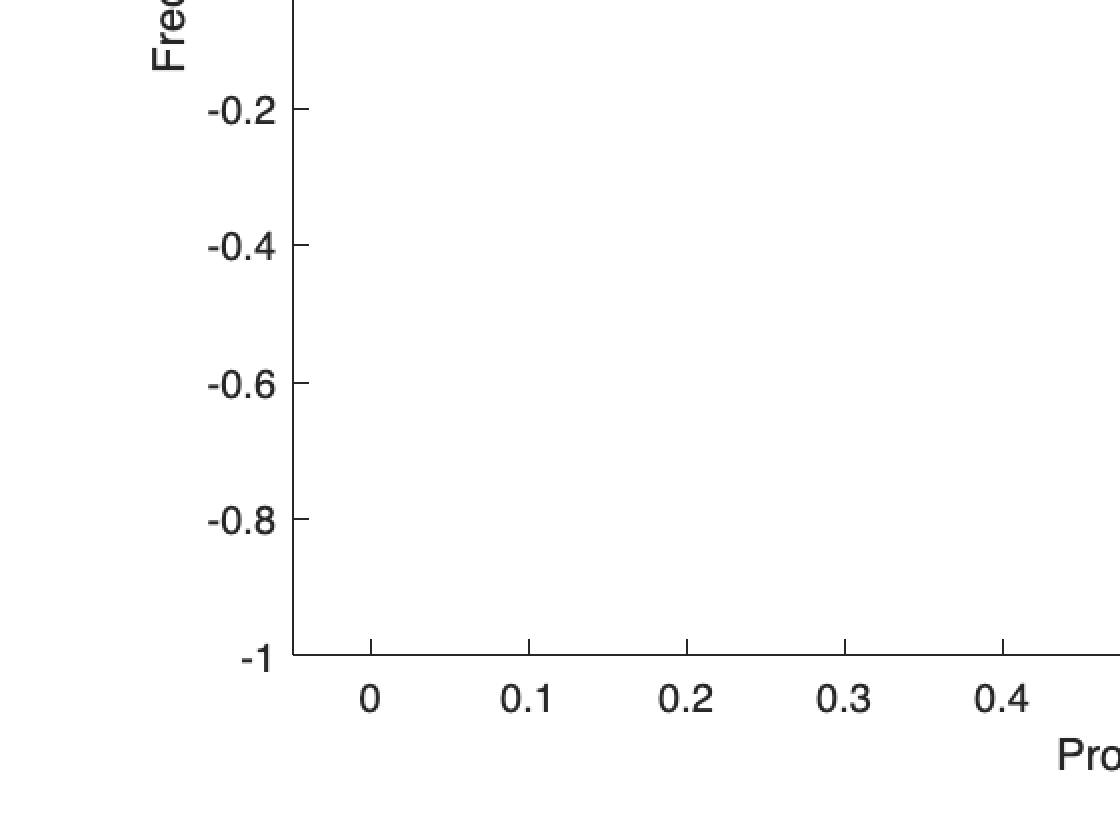

%same per income 
%CLUSTER 1 INCOME



category2=categorical({'2'});
C1ClientID_Inc = ClientID_C1(C1.Investments==category2); %i keep only the ones interested in income inv


C1ClientRiskPropensity_Inc = C1RiskProp_full(C1.Investments==category2); 

% Let's have a look at these incomes...
figure
histogram(C1ClientRiskPropensity_Inc, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


IncomeProducts = Products(Products.Type == 0,:)

NBA_C1_Income = [];

RecommendedRiskLevel_C1I = [];
minRisk_C1I = min(IncomeProducts.Risk);


IncomeProducts = 4×3 table
    ID    Type    Risk
    __    ____    ____

     2     0       0.3
     3     0      0.12
     4     0      0.44
    10     0      0.13


for i = 1: size(C1ClientRiskPropensity_Inc, 1)
    if C1ClientRiskPropensity_Inc(i)> minRisk_C1I
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<C1ClientRiskPropensity_Inc(i)));
        NBA_C1_Income= [NBA_C1_Income; categorical(IncomeProducts.ID(IncomeProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C1_Income= [NBA_C1_Income; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C1I = [RecommendedRiskLevel_C1I; M];
end

% recommendations
CatID_C1I = categorical(C1ClientID_Inc);
NBA_C1_Income= [CatID_C1I NBA_C1_Income];

%capire perche' non va 
histogram(NBA_C1_Income, 'FaceColor', 'blue')
title('Income Products of Cluster 1')
xlabel('Product ID')
ylabel('Frequency')

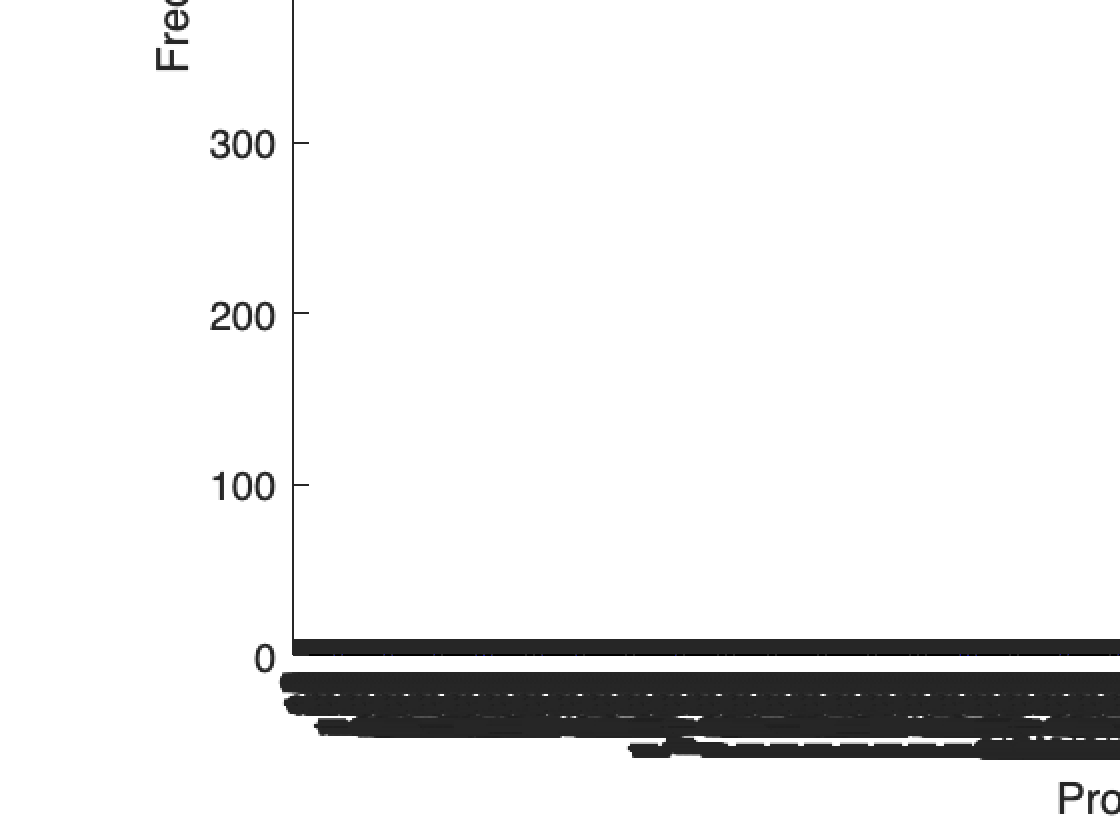

%concateno i due vettori coi risultati quello accumulation e quello income 
NBA_C1_total=[];
NBA_C1_total=vertcat(NBA_C1,NBA_C1_Income );


%capire perche' non va 
histogram(NBA_C1_total, 'FaceColor', 'blue')
title('Products of Cluster 1')
xlabel('Product ID')
ylabel('Frequency')

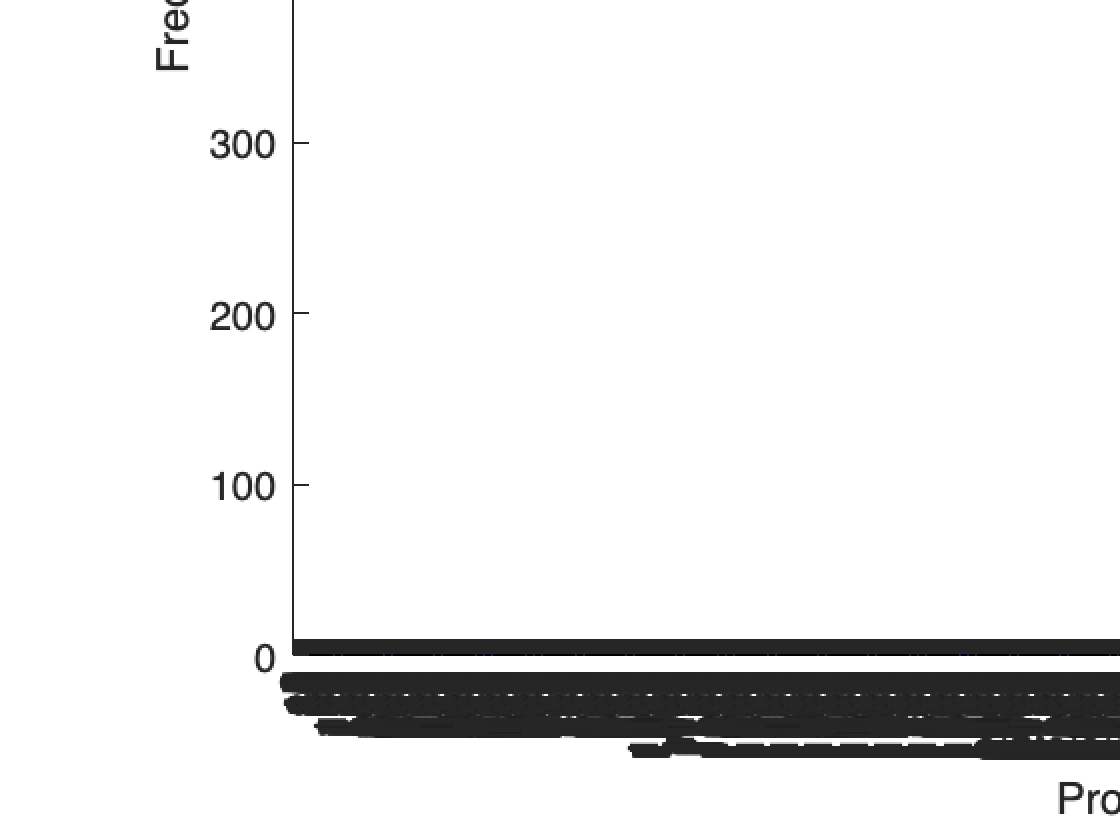

%CLUSTER 2 ACCUMULATION

ClientID_C2 = C2.ID

category3=categorical({'3'})

C2ClientID = ClientID_C2(C2.Investments==category3); %i keep only the ones interested in accumulation inv

% Retrieving clients' risk propensities
C2RiskProp_full=0.2*C2.Income+0.2*C2.Saving+0.1*C2.Wealth+0.2*C2.FinEdu+0.1*(C2.Age/100)+0.2*(1./C2.Debt)

ClientID_C2 = 759×1 categorical array
     5 
     9 
     10 
     21 
     29 
     31 
     35 
     43 
     48 
     52 
     62 
     67 
     68 
     72 
     74 
     83 
     88 
     102 
     103 
     104 
     105 
     108 
     110 
     117 
     123 
     129 
     144 
     153 
     155 
     164 


%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)


category3 = categorical
     3 


C2ClientRiskPropensity = C2RiskProp_full(C2.Investments==category3); 

% Let's have a look at these incomes...
figure

C2RiskProp_full =     0.8025
    0.7292
    0.8598
    1.0460
    0.8300
    0.8536
    0.9852
    1.0161
    0.7853
    0.8287


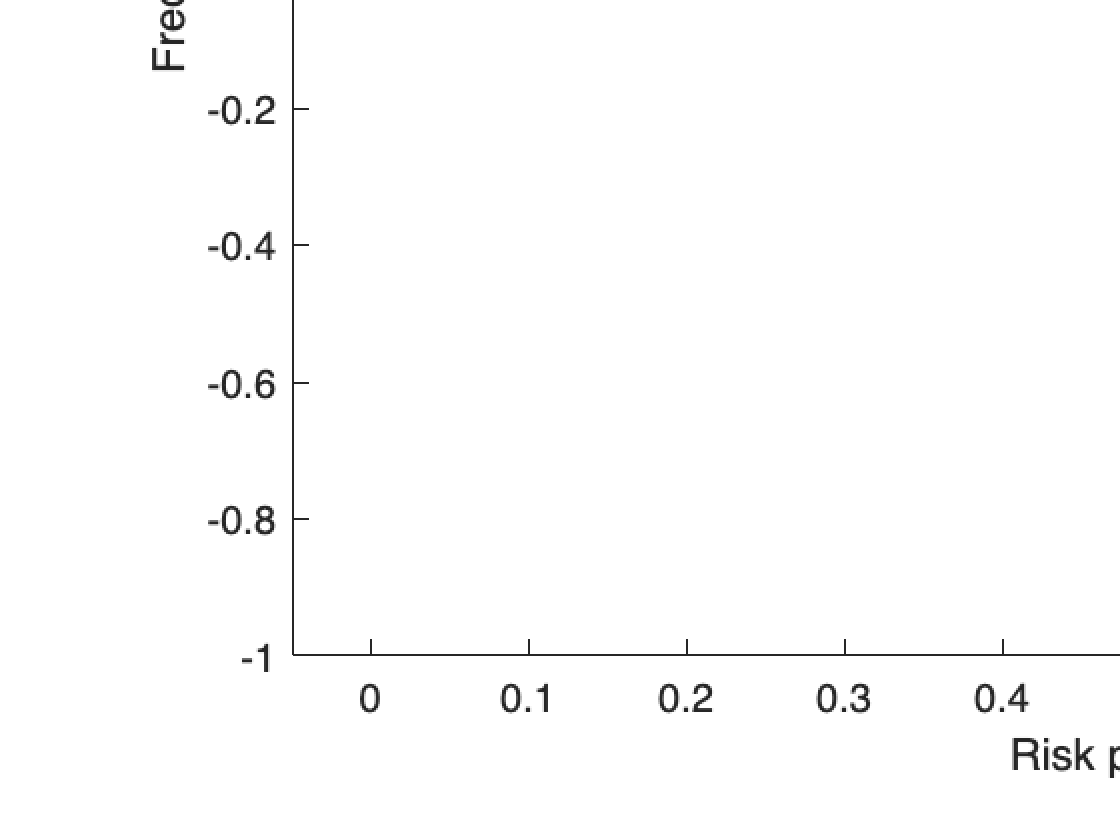

histogram(C2ClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C2P = [];
NBA_C2Product= double(NBA_C2P);
RecommendedRiskLevel_C2 = [];
minRisk_C2 = min(AccumulationProducts.Risk);


for i = 1: size(C2ClientRiskPropensity, 1)
    if C2ClientRiskPropensity(i)> minRisk_C2
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<C2ClientRiskPropensity(i)));
        NBA_C2P= [NBA_C2P; categorical(AccumulationProducts.ID(AccumulationProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C2P= [NBA_C2P; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C2 = [RecommendedRiskLevel_C2; M];
end

% recommendations
CatID_C2 = categorical(C2ClientID);
NBA_C2= [CatID_C2 NBA_C2P];


histogram(NBA_C2P, 'FaceColor', 'blue')
title('Acc Products of Cluster 2')
xlabel('Product ID')
ylabel('Frequency')


%same per income 
%CLUSTER 2 INCOME


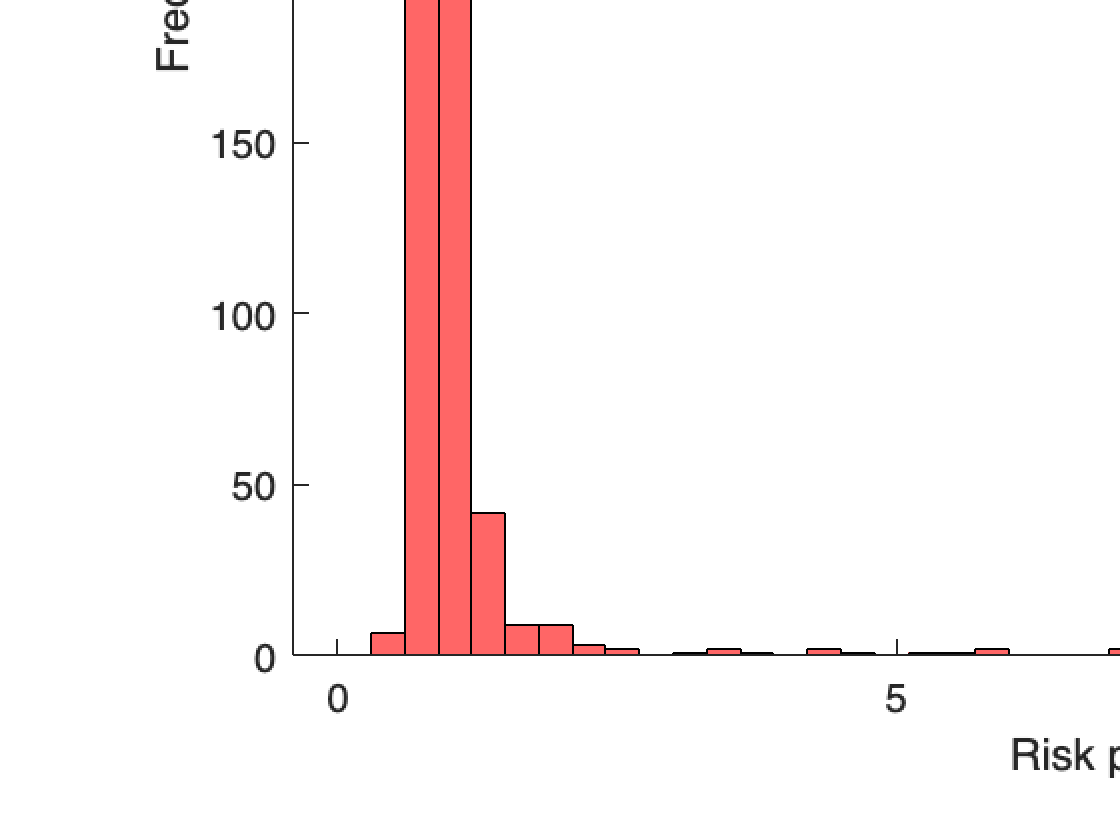


category2=categorical({'2'});
C2ClientID_Inc = ClientID_C2(C2.Investments==category2); %i keep only the ones interested in income inv


C2ClientRiskPropensity_Inc = C2RiskProp_full(C2.Investments==category2); 

% Let's have a look at these incomes...
figure
histogram(C2ClientRiskPropensity_Inc, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C2_Income = [];
RecommendedRiskLevel_C2I = [];
minRisk_C2I = min(IncomeProducts.Risk);


for i = 1: size(C2ClientRiskPropensity_Inc, 1)
    if C2ClientRiskPropensity_Inc(i)> minRisk_C2I
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<C2ClientRiskPropensity_Inc(i)));
        NBA_C2_Income= [NBA_C2_Income; categorical(IncomeProducts.ID(IncomeProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C2_Income= [NBA_C2_Income; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C2I = [RecommendedRiskLevel_C2I; M];
end

% recommendations
CatID_C2I = categorical(C2ClientID_Inc);
NBA_C2_Income= [CatID_C2I NBA_C2_Income];

%capire perche' non va 
histogram(NBA_C2_Income, 'FaceColor', 'blue')
title('Income Products of Cluster 2')
xlabel('Product ID')
ylabel('Frequency')

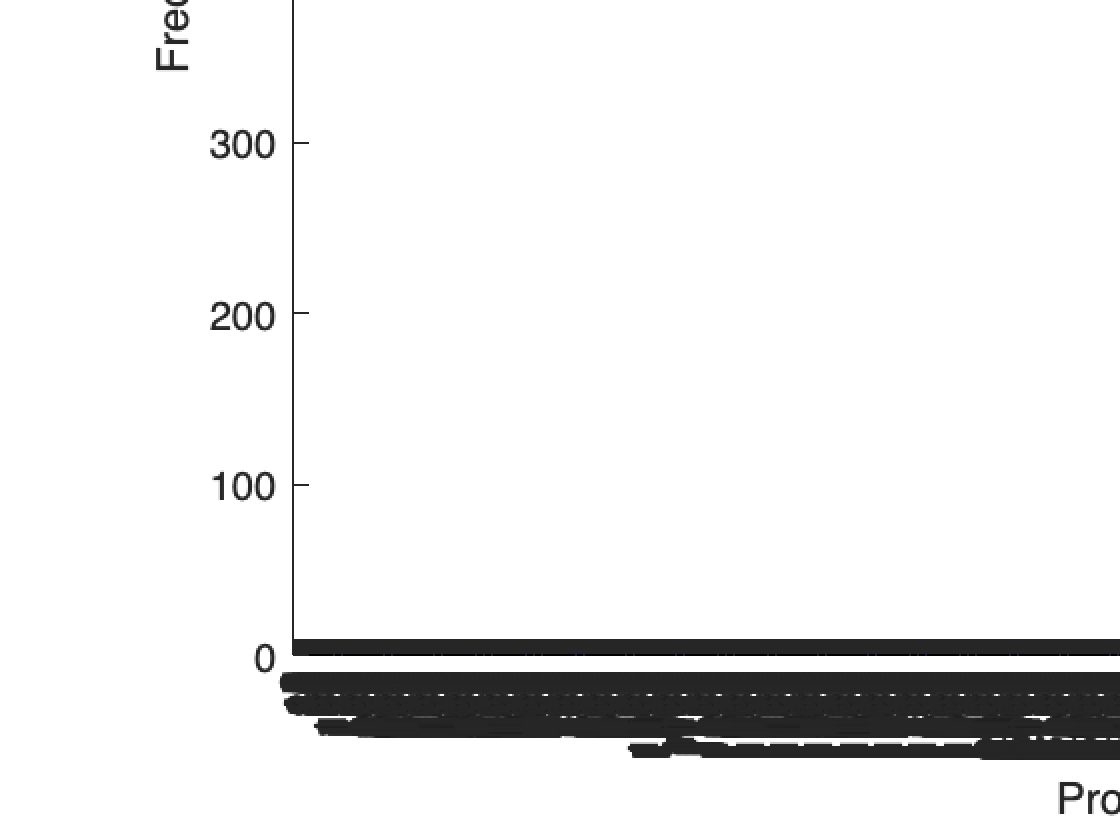

%concateno i due vettori coi risultati quello accumulation e quello income 
NBA_C2_total=[];
NBA_C2_total=vertcat(NBA_C2,NBA_C2_Income );


%capire perche' non va 
histogram(NBA_C2_total, 'FaceColor', 'blue')
title('Products of Cluster 2')
xlabel('Product ID')
ylabel('Frequency')

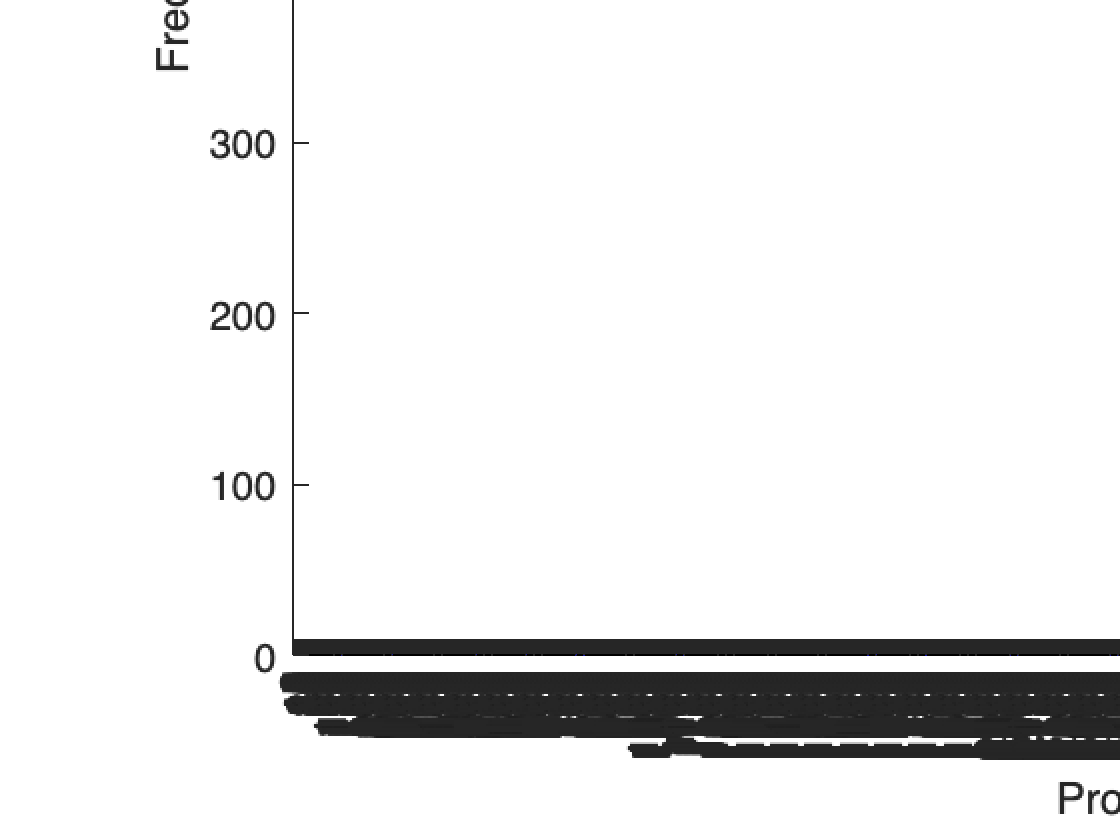

%CLUSTER 3 ACCUMULATION

ClientID_C3 = C3.ID

C3ClientID = ClientID_C3(C3.Investments==category3); %i keep only the ones interested in accumulation inv


% Retrieving clients' risk propensities
C3RiskProp_full=0.2*C3.Income+0.2*C3.Saving+0.1*C3.Wealth+0.2*C3.FinEdu+0.1*(C3.Age/100)+0.2*(1./C3.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

ClientID_C3 = 804×1 categorical array
     6 
     11 
     16 
     19 
     23 
     24 
     26 
     36 
     40 
     41 
     45 
     54 
     57 
     58 
     63 
     75 
     76 
     77 
     84 
     86 
     90 
     114 
     116 
     119 
     121 
     131 
     133 
     138 
     146 
     158 



C3ClientRiskPropensity = C3RiskProp_full(C3.Investments==category3); 

% Let's have a look at these incomes...
figure

C3RiskProp_full =     0.7560
    1.2395
    1.8559
    0.9786
    0.8014
    0.9788
    1.0593
    0.8750
    0.8316
    0.8974


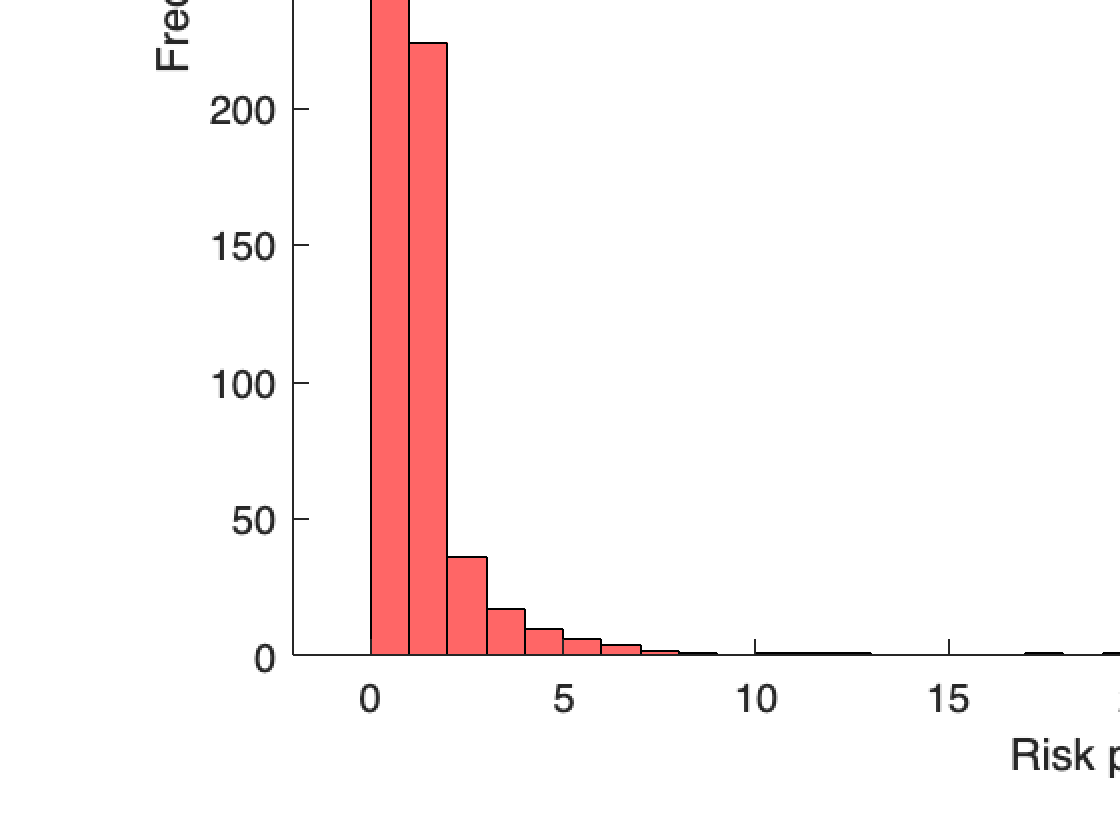

histogram(C3ClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C3P = [];
NBA_C3Product= double(NBA_C3P);
RecommendedRiskLevel_C3 = [];
minRisk_C3 = min(AccumulationProducts.Risk);


for i = 1: size(C3ClientRiskPropensity, 1)
    if C3ClientRiskPropensity(i)> minRisk_C3
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<C3ClientRiskPropensity(i)));
        NBA_C3P= [NBA_C3P; categorical(AccumulationProducts.ID(AccumulationProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C3P= [NBA_C3P; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C3 = [RecommendedRiskLevel_C3; M];
end

% recommendations
CatID_C3 = categorical(C3ClientID);
NBA_C3= [CatID_C3 NBA_C3P];


histogram(NBA_C3P, 'FaceColor', 'blue')
title('Acc Products of Cluster 3')
xlabel('Product ID')
ylabel('Frequency')


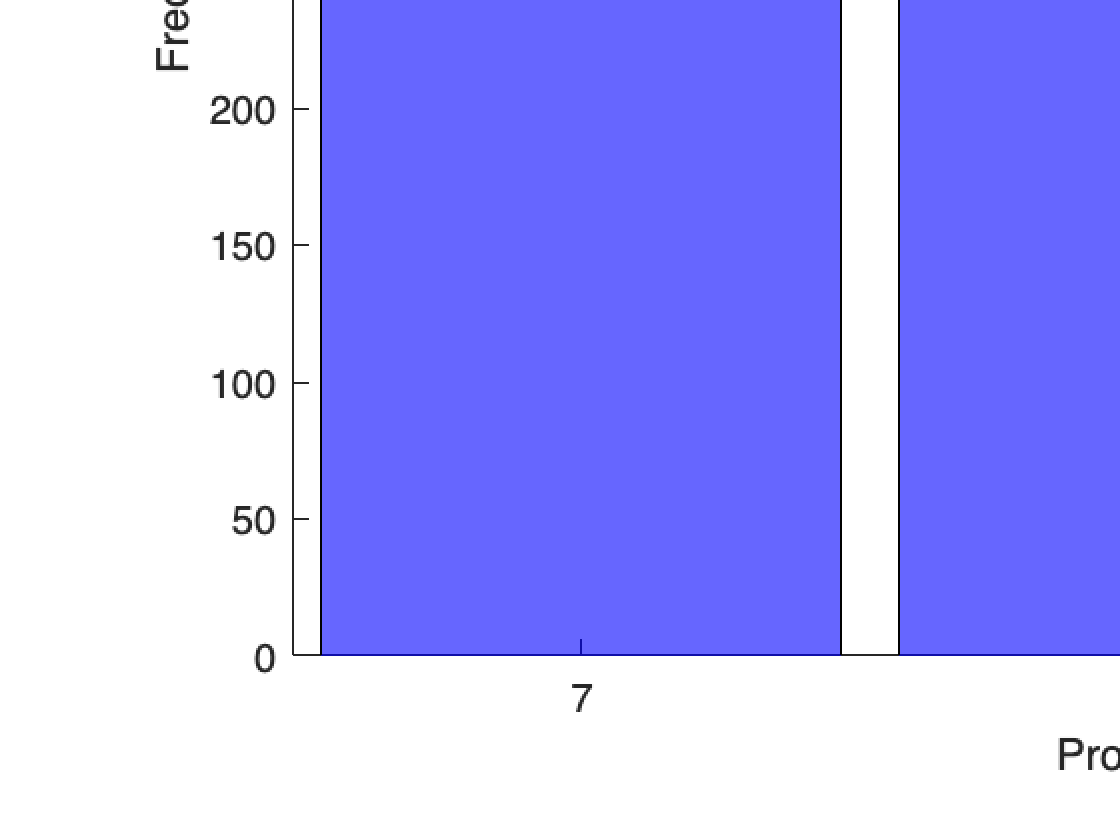

%same per income 
%CLUSTER 3 INCOME



C3ClientID_Inc = ClientID_C3(C3.Investments==category2); %i keep only the ones interested in income inv


C3ClientRiskPropensity_Inc = C3RiskProp_full(C3.Investments==category2); 

% Let's have a look at these incomes...
figure
histogram(C3ClientRiskPropensity_Inc, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C3_Income = [];
RecommendedRiskLevel_C3I = [];
minRisk_C3I = min(IncomeProducts.Risk);


for i = 1: size(C3ClientRiskPropensity_Inc, 1)
    if C3ClientRiskPropensity_Inc(i)> minRisk_C3I
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<C3ClientRiskPropensity_Inc(i)));
        NBA_C3_Income= [NBA_C3_Income; categorical(IncomeProducts.ID(IncomeProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C3_Income= [NBA_C3_Income; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C3I = [RecommendedRiskLevel_C3I; M];
end

% recommendations
CatID_C3I = categorical(C3ClientID_Inc);
NBA_C3_Income= [CatID_C3I NBA_C3_Income];

%capire perche' non va 
histogram(NBA_C3_Income, 'FaceColor', 'blue')
title('Income Products of Cluster 3')
xlabel('Product ID')
ylabel('Frequency')

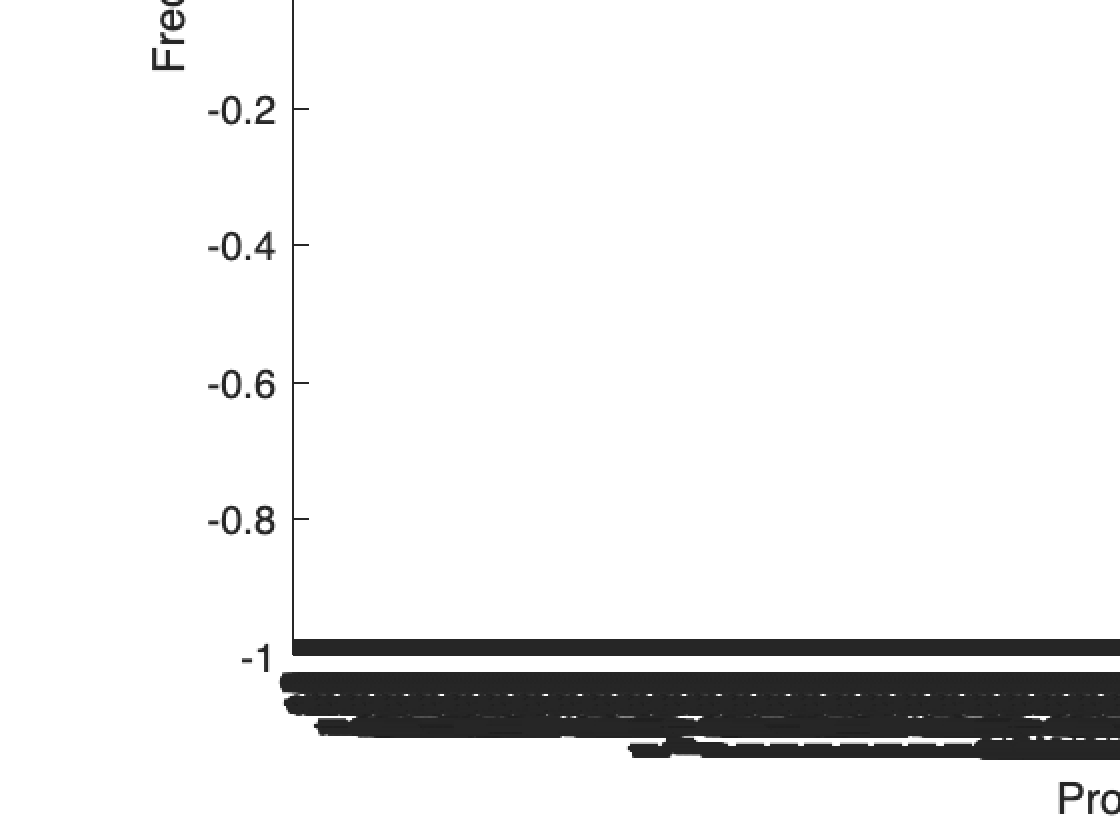

%concateno i due vettori coi risultati quello accumulation e quello income 
NBA_C3_total=[];
NBA_C3_total=vertcat(NBA_C3,NBA_C3_Income );


%capire perche' non va 
histogram(NBA_C3_total, 'FaceColor', 'blue')
title('Products of Cluster 3')
xlabel('Product ID')
ylabel('Frequency')

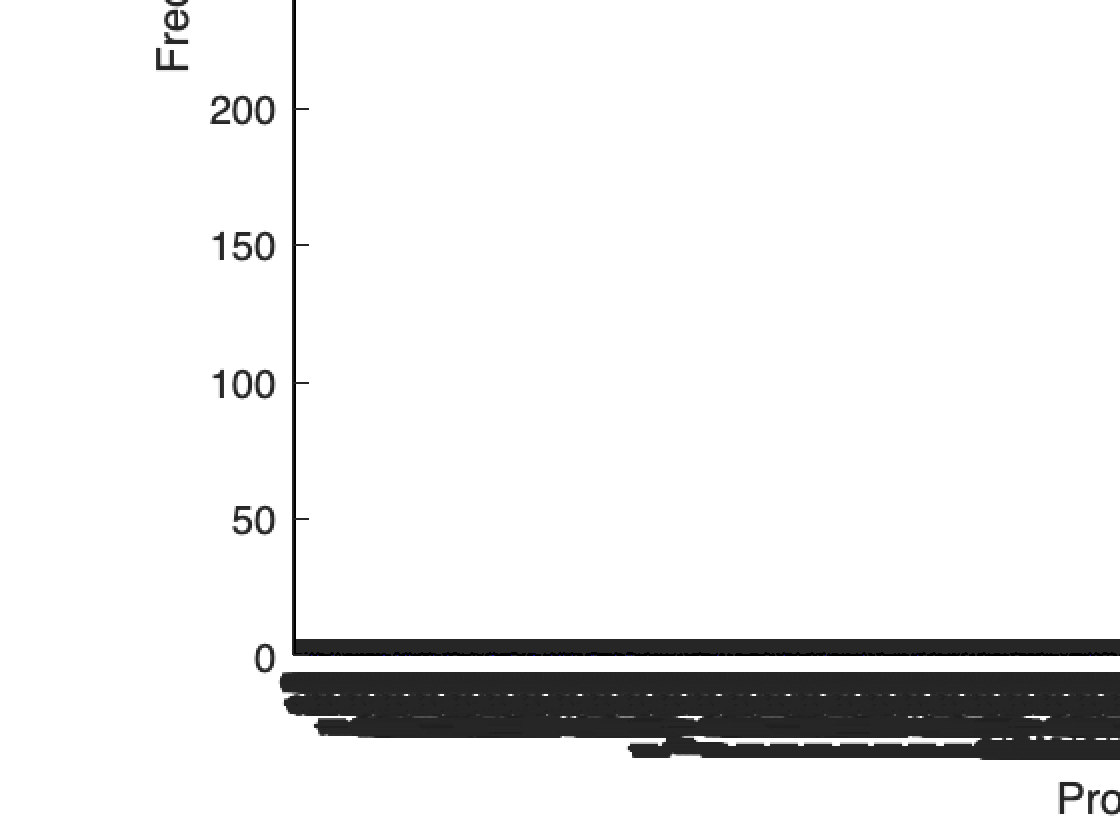

%CLUSTER 4 ACCUMULATION

ClientID_C4 = C4.ID

C4ClientID = ClientID_C4(C4.Investments==category3); %i keep only the ones interested in accumulation inv


% Retrieving clients' risk propensities
C4RiskProp_full=0.2*C4.Income+0.2*C4.Saving+0.1*C4.Wealth+0.2*C4.FinEdu+0.1*(C4.Age/100)+0.2*(1./C4.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

ClientID_C4 = 1386×1 categorical array
     2 
     3 
     15 
     22 
     44 
     46 
     51 
     55 
     61 
     65 
     73 
     78 
     89 
     91 
     92 
     93 
     95 
     97 
     98 
     100 
     107 
     109 
     111 
     115 
     118 
     125 
     126 
     128 
     137 
     139 



C4ClientRiskPropensity = C4RiskProp_full(C4.Investments==category3); 

% Let's have a look at these incomes...
figure

C4RiskProp_full =     0.9202
    0.9644
    0.9908
    0.7413
    1.0962
    0.9255
    0.8317
    0.8020
    0.9636
    0.7694


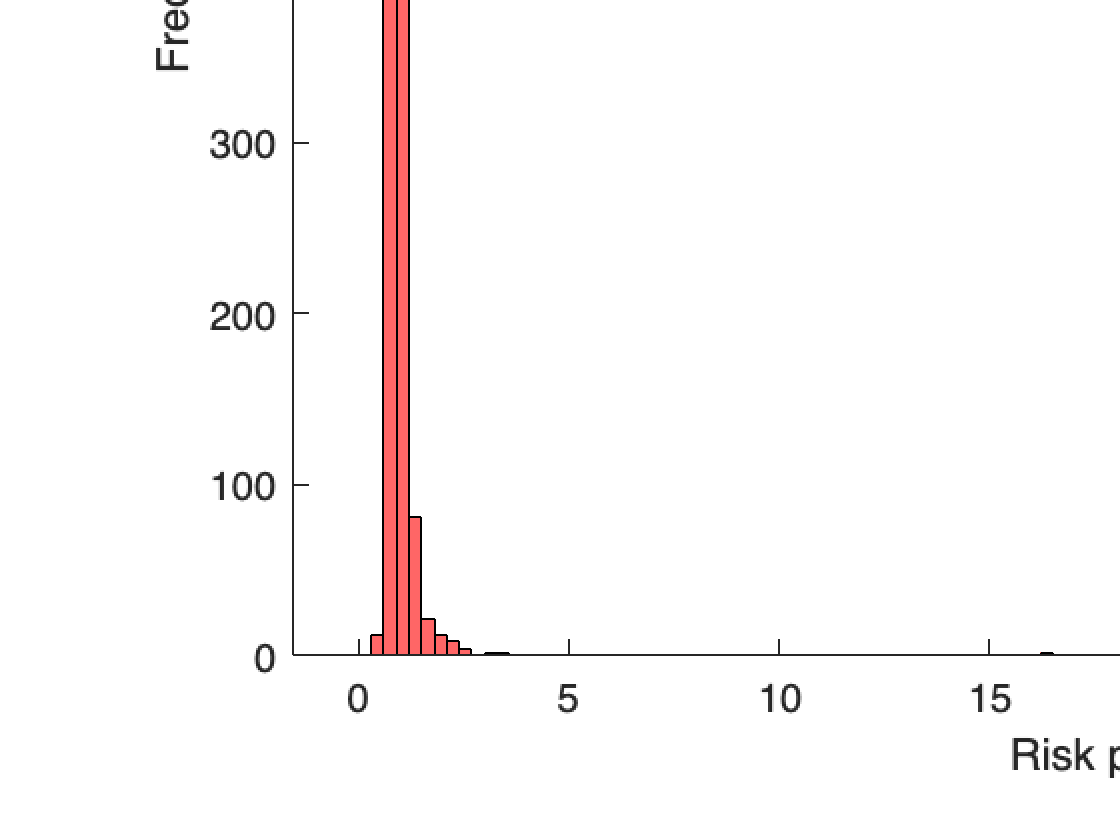

histogram(C4ClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C4P = [];
NBA_C4Product= double(NBA_C4P);
RecommendedRiskLevel_C4 = [];
minRisk_C4 = min(AccumulationProducts.Risk);


for i = 1: size(C4ClientRiskPropensity, 1)
    if C4ClientRiskPropensity(i)> minRisk_C4
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<C4ClientRiskPropensity(i)));
        NBA_C4P= [NBA_C4P; categorical(AccumulationProducts.ID(AccumulationProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C4P= [NBA_C4P; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C4 = [RecommendedRiskLevel_C4; M];
end

% recommendations
CatID_C4 = categorical(C4ClientID);
NBA_C4= [CatID_C4 NBA_C4P];


histogram(NBA_C4P, 'FaceColor', 'blue')
title('Acc Products of Cluster 4')
xlabel('Product ID')
ylabel('Frequency')


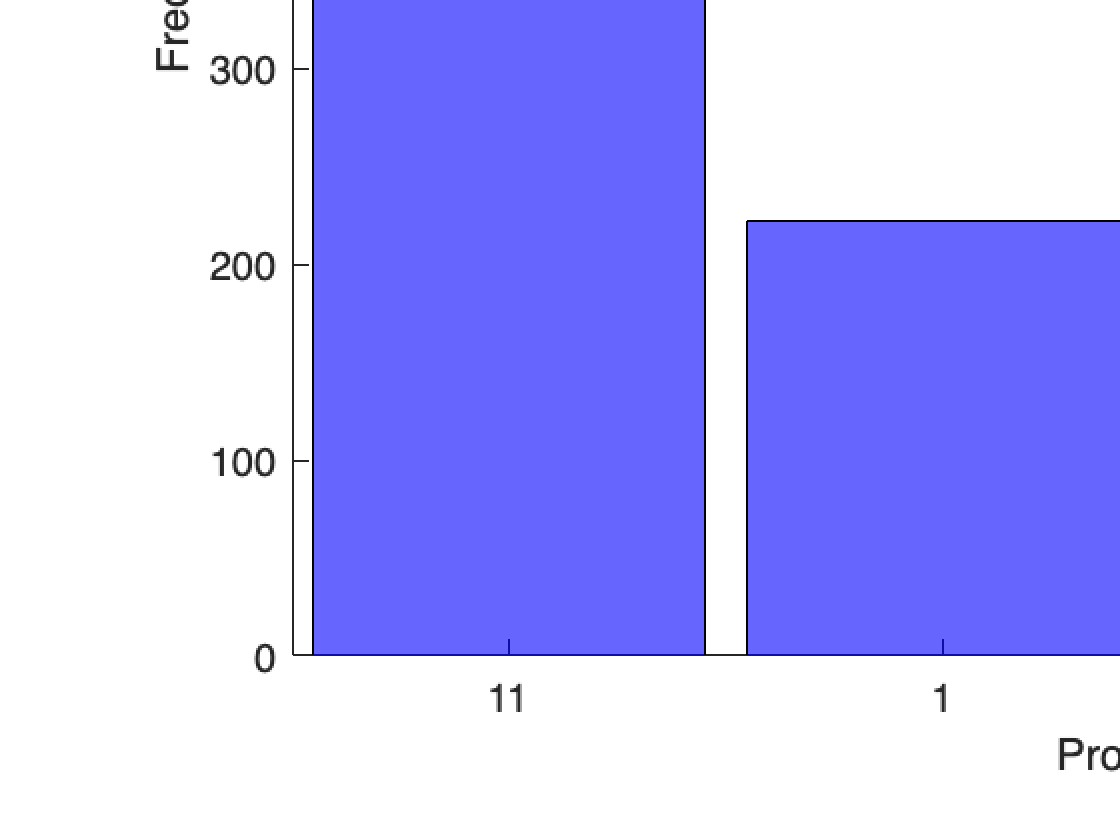

%same per income 
%CLUSTER 4 INCOME



C4ClientID_Inc = ClientID_C4(C4.Investments==category2); %i keep only the ones interested in income inv


C4ClientRiskPropensity_Inc = C4RiskProp_full(C4.Investments==category2); 

% Let's have a look at these incomes...
figure
histogram(C4ClientRiskPropensity_Inc, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C4_Income = [];
RecommendedRiskLevel_C4I = [];
minRisk_C4I = min(IncomeProducts.Risk);


for i = 1: size(C4ClientRiskPropensity_Inc, 1)
    if C4ClientRiskPropensity_Inc(i)> minRisk_C4I
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<C4ClientRiskPropensity_Inc(i)));
        NBA_C4_Income= [NBA_C4_Income; categorical(IncomeProducts.ID(IncomeProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C4_Income= [NBA_C4_Income; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C4I = [RecommendedRiskLevel_C4I; M];
end

% recommendations
CatID_C4I = categorical(C4ClientID_Inc);
NBA_C4_Income= [CatID_C4I NBA_C4_Income];

%capire perche' non va 
histogram(NBA_C4_Income, 'FaceColor', 'blue')
title('Income Products of Cluster 4')
xlabel('Product ID')
ylabel('Frequency')

%concateno i due vettori coi risultati quello accumulation e quello income 
NBA_C4_total=[];
NBA_C4_total=vertcat(NBA_C4,NBA_C4_Income );


%capire perche' non va 
histogram(NBA_C4_total, 'FaceColor', 'blue')
title('Products of Cluster 4')
xlabel('Product ID')
ylabel('Frequency')

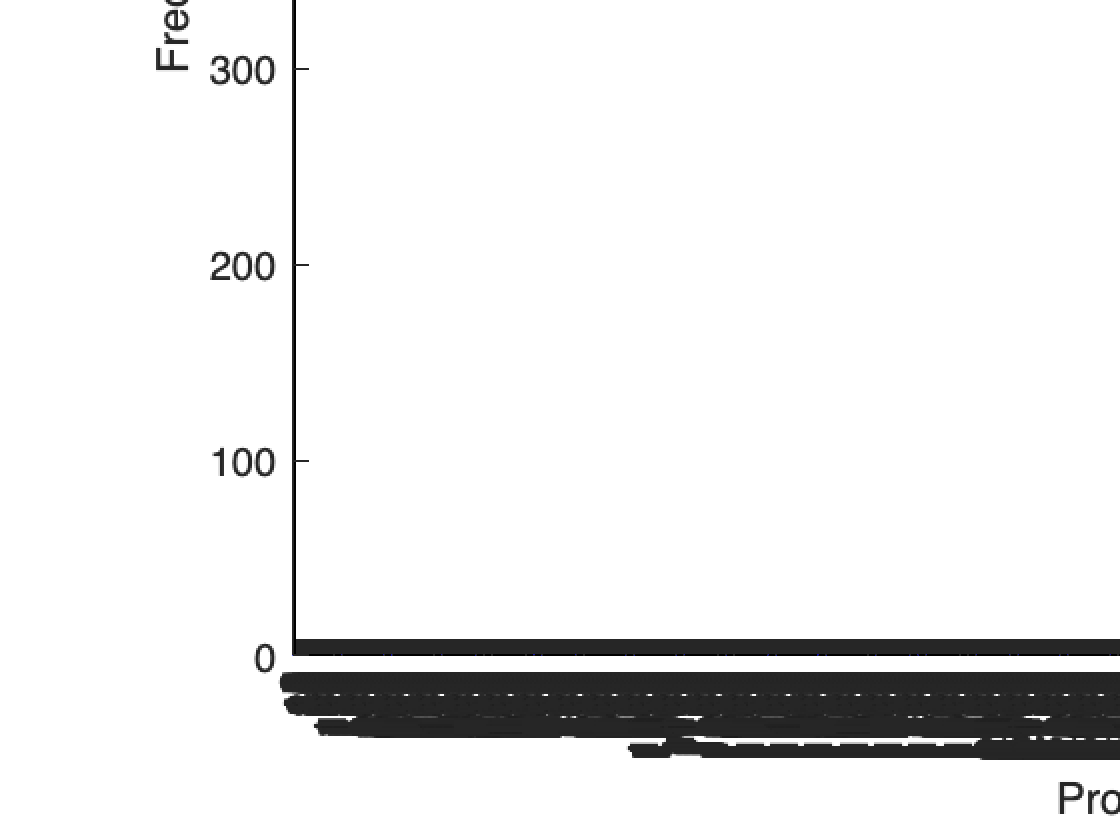

%CLUSTER 5 ACCUMULATION

ClientID_C5 = C5.ID

C5ClientID = ClientID_C5(C5.Investments==category3); %i keep only the ones interested in accumulation inv


% Retrieving clients' risk propensities
C5RiskProp_full=0.2*C5.Income+0.2*C5.Saving+0.1*C5.Wealth+0.2*C5.FinEdu+0.1*(C5.Age/100)+0.2*(1./C5.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

ClientID_C5 = 770×1 categorical array
     13 
     17 
     18 
     39 
     42 
     49 
     50 
     53 
     56 
     66 
     79 
     80 
     81 
     94 
     106 
     120 
     141 
     143 
     148 
     156 
     165 
     166 
     167 
     168 
     172 
     195 
     197 
     198 
     199 
     203 



C5ClientRiskPropensity = C5RiskProp_full(C5.Investments==category3); 

% Let's have a look at these incomes...
figure

C5RiskProp_full =     0.7872
    0.7520
    0.9053
    1.9357
    1.6357
    0.6363
    3.0874
    1.2534
    1.0032
    3.7451


histogram(C5ClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C5P = [];
NBA_C5Product= double(NBA_C5P);
RecommendedRiskLevel_C5 = [];
minRisk_C5 = min(AccumulationProducts.Risk);


for i = 1: size(C5ClientRiskPropensity, 1)
    if C5ClientRiskPropensity(i)> minRisk_C5
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<C5ClientRiskPropensity(i)));
        NBA_C5P= [NBA_C5P; categorical(AccumulationProducts.ID(AccumulationProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C5P= [NBA_C5P; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C5 = [RecommendedRiskLevel_C5; M];
end

% recommendations
CatID_C5 = categorical(C5ClientID);
NBA_C5= [CatID_C5 NBA_C5P];


histogram(NBA_C5P, 'FaceColor', 'blue')
title('Acc Products of Cluster 5')
xlabel('Product ID')
ylabel('Frequency')


%same per income 
%CLUSTER 5 INCOME



C5ClientID_Inc = ClientID_C5(C5.Investments==category2); %i keep only the ones interested in income inv


C5ClientRiskPropensity_Inc = C5RiskProp_full(C5.Investments==category2); 

% Let's have a look at these incomes...
figure
histogram(C5ClientRiskPropensity_Inc, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C5_Income = [];
RecommendedRiskLevel_C5I = [];
minRisk_C5I = min(IncomeProducts.Risk);


for i = 1: size(C5ClientRiskPropensity_Inc, 1)
    if C5ClientRiskPropensity_Inc(i)> minRisk_C5I
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<C5ClientRiskPropensity_Inc(i)));
        NBA_C5_Income= [NBA_C5_Income; categorical(IncomeProducts.ID(IncomeProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C5_Income= [NBA_C5_Income; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C5I = [RecommendedRiskLevel_C5I; M];
end

% recommendations
CatID_C5I = categorical(C5ClientID_Inc);
NBA_C5_Income= [CatID_C5I NBA_C5_Income];

%capire perche' non va 
histogram(NBA_C5_Income, 'FaceColor', 'blue')
title('Income Products of Cluster 5')
xlabel('Product ID')
ylabel('Frequency')


%concateno i due vettori coi risultati quello accumulation e quello income 
NBA_C5_total=[];
NBA_C5_total=vertcat(NBA_C5,NBA_C5_Income );


%capire perche' non va 
histogram(NBA_C5_total, 'FaceColor', 'blue')
title('Products of Cluster 5')
xlabel('Product ID')
ylabel('Frequency')

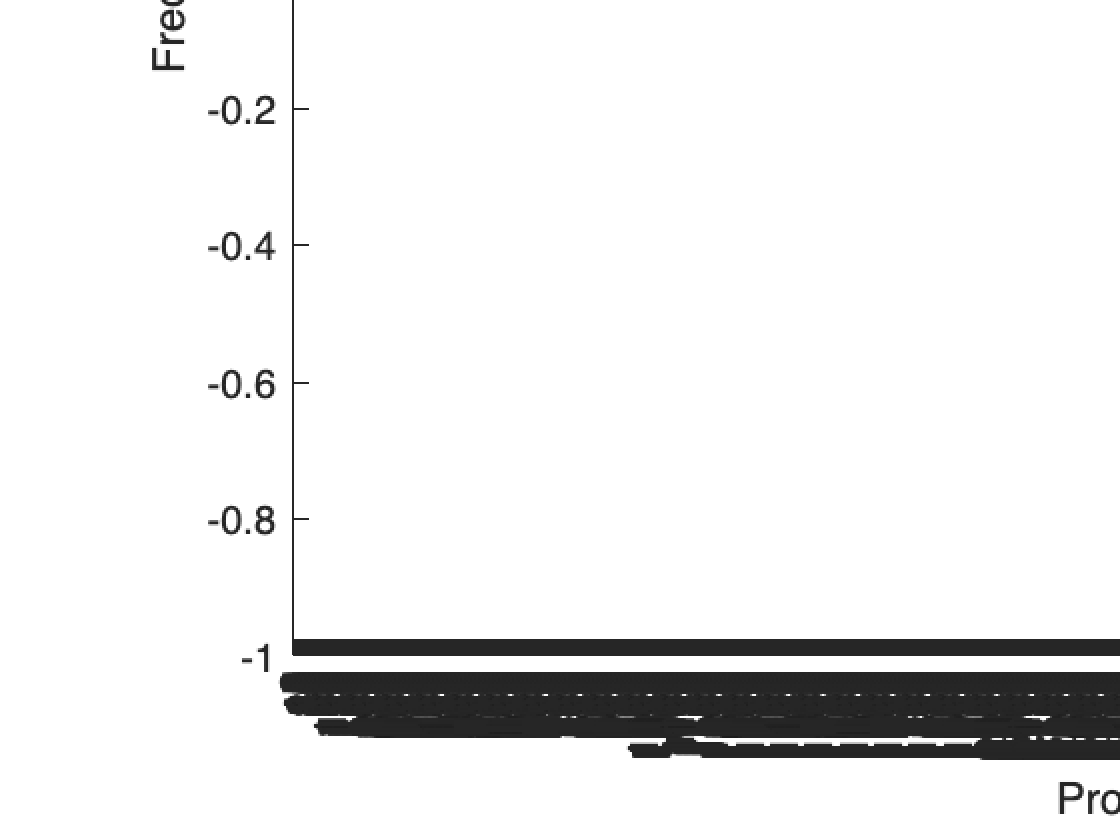

%CLUSTER 6 ACCUMULATION

ClientID_C6 = C6.ID

C6ClientID = ClientID_C6(C6.Investments==category3); %i keep only the ones interested in accumulation inv


% Retrieving clients' risk propensities
C6RiskProp_full=0.2*C6.Income+0.2*C6.Saving+0.1*C6.Wealth+0.2*C6.FinEdu+0.1*(C6.Age/100)+0.2*(1./C6.Debt)
%RiskProp=0.2*income + 0.2*saving + 0.1*wealth + 0.2*FinEdu + 0.1*Age + 0.2*(-Debt)

ClientID_C6 = 544×1 categorical array
     1 
     7 
     14 
     25 
     27 
     28 
     37 
     47 
     59 
     60 
     69 
     85 
     101 
     113 
     122 
     127 
     130 
     134 
     147 
     159 
     178 
     187 
     206 
     211 
     219 
     223 
     225 
     228 
     232 
     235 



% Let's have a look at these incomes...
figure
histogram(C6RiskProp_full, 'FaceColor', 'blue')
title('Risk Propensity of target clients')

C6RiskProp_full =     1.1961
    2.6390
    0.6760
    1.1019
    0.7760
    0.7706
    1.1123
    0.8239
    1.3036
    1.6115


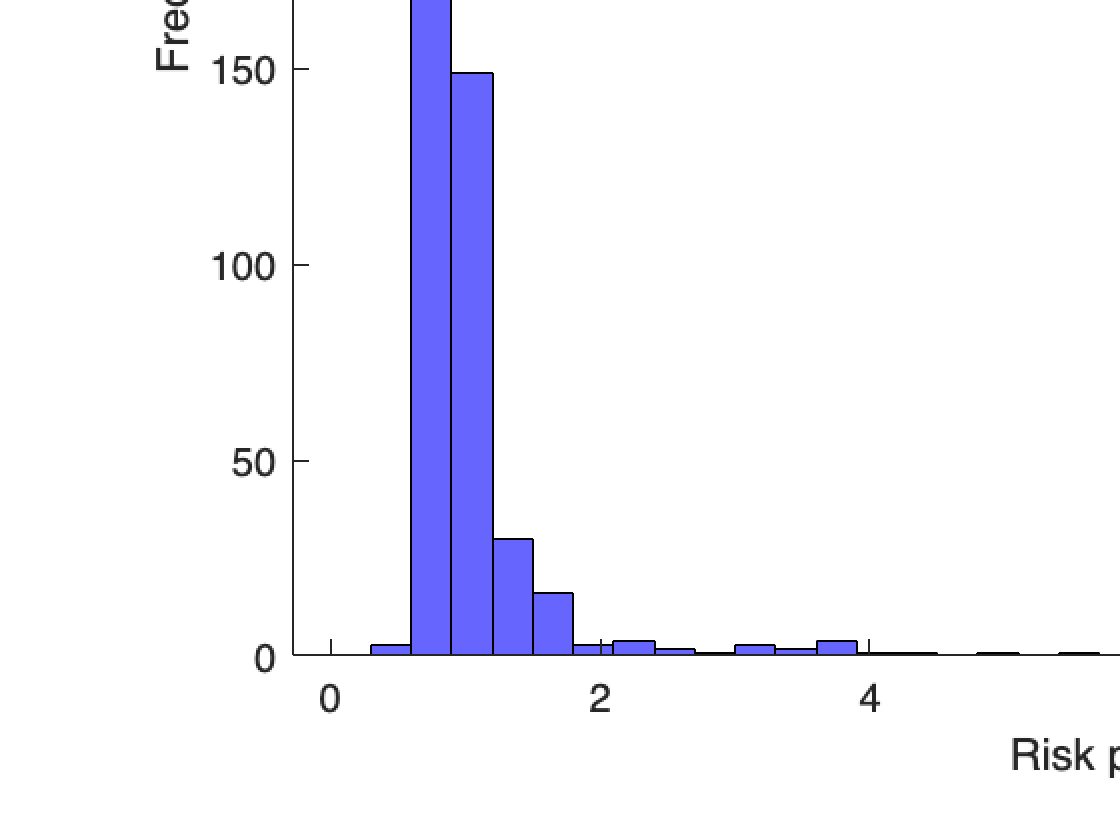

xlabel('Risk propensity')
ylabel('Frequency')


C6ClientRiskPropensity = C6RiskProp_full(C6.Investments==category3); 

% Let's have a look at these incomes...
figure

histogram(C6ClientRiskPropensity, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C6P = [];
NBA_C6Product= double(NBA_C6P);
RecommendedRiskLevel_C6 = [];
minRisk_C6 = min(AccumulationProducts.Risk);


for i = 1: size(C6ClientRiskPropensity, 1)
    if C6ClientRiskPropensity(i)> minRisk_C6
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<C6ClientRiskPropensity(i)));
        NBA_C6P= [NBA_C6P; categorical(AccumulationProducts.ID(AccumulationProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C6P= [NBA_C6P; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C6 = [RecommendedRiskLevel_C6; M];
end

% recommendations
CatID_C6 = categorical(C6ClientID);
NBA_C6= [CatID_C6 NBA_C6P];


histogram(NBA_C6P, 'FaceColor', 'blue')
title('Acc Products of Cluster 6')
xlabel('Product ID')
ylabel('Frequency')


%same per income 
%CLUSTER 6 INCOME



C6ClientID_Inc = ClientID_C6(C6.Investments==category2); %i keep only the ones interested in income inv


C6ClientRiskPropensity_Inc = C6RiskProp_full(C6.Investments==category2); 

% Let's have a look at these incomes...
figure
histogram(C6ClientRiskPropensity_Inc, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')


NBA_C6_Income = [];
RecommendedRiskLevel_C6I = [];
minRisk_C6I = min(IncomeProducts.Risk);


for i = 1: size(C6ClientRiskPropensity_Inc, 1)
    if C6ClientRiskPropensity_Inc(i)> minRisk_C6I
        % find the suitable product with the highest acceptable risk
        M = max(IncomeProducts.Risk(IncomeProducts.Risk<C6ClientRiskPropensity_Inc(i)));
        NBA_C6_Income= [NBA_C6_Income; categorical(IncomeProducts.ID(IncomeProducts.Risk == M))];
    else
        % no suitable product in the product range
        NBA_C6_Income= [NBA_C6_Income; '0'];
        M = 0;
    end
    RecommendedRiskLevel_C6I = [RecommendedRiskLevel_C6I; M];
end

% recommendations
CatID_C6I = categorical(C6ClientID_Inc);
NBA_C6_Income= [CatID_C6I NBA_C6_Income];

%capire perche' non va 
histogram(NBA_C6_Income, 'FaceColor', 'blue')
title('Income Products of Cluster 6')
xlabel('Product ID')
ylabel('Frequency')


%concateno i due vettori coi risultati quello accumulation e quello income 
NBA_C6_total=[];
NBA_C6_total=vertcat(NBA_C6,NBA_C6_Income );


%capire perche' non va 
histogram(NBA_C6_total, 'FaceColor', 'blue')
title('Products of Cluster 6')
xlabel('Product ID')
ylabel('Frequency')


%DA QUI IN POI E' LA PARTE DELL'ALGORITMO PREDITTIVO CHE NON SO BENE A COSA SERVA

### Dividing our data

For the sake of time scarcity/brevity (...here we are doing an exercise, and I'm just giving you a hint of a solution), I'll go for the first approach, but whwnever is possible I strongly suggest and practice the second approach.

I partion data directly, splitting features and responses, but you might find useful this function, `cvpartition`, that defines random partitions on a data set: [https://it.mathworks.com/help/stats/cvpartition.html](https://it.mathworks.com/help/stats/cvpartition.html).

% Create two new columns filled with zeros
newColumn1 = zeros(size(dati, 1), 1);
newColumn2 = zeros(size(dati, 1), 1);


% Assuming the categorical variable is stored in the first column of 'data'
categoricalVariable = dati.Investments;
%categoricalVariableNumeric = grp2idx(categoricalVariable);

% Update the new columns based on the values of the categorical variable

% If categorical variable is 1, set the corresponding entry in newColumn1 to 1
category2=categorical({'2'});
for i=1:size(dati,1)
    if categoricalVariable(i,1) == 2;

Unrecognized function or variable 'dati'.

        newColumn1(i,1) = 1;
    end
end
% If categorical variable is 2, set the corresponding entry in newColumn2 to 1
newColumn2(categoricalVariable = 3) = 1;

% Add the new columns to the dataset
extendedData = [data newColumn1 newColumn2];


% Numerical
N = vartype('numeric');
Data = BankClients(:,2:end); % Exclude 1st col = ID
% Removing the gender and the family size
%Data(:, "Gender") = [];
%Data(:, "FamilySize") = [];
NumFeatures = Data(:,N); % subtable of numerical features
XNum = NumFeatures.Variables; % create a matrix 
XNum = rescale(XNum); % normalize in [0, 1]
% Categorical
C = vartype('categorical');
CatFeatures = Data(:,C); % subtable of categorical features
% Encoding (ie create dummy variables)
%grp2idx create a vector of integer values from 1 up to the number K of distinct groups.
XCat = [];
for i = 1:size(CatFeatures, 2)
    XCat_i = dummyvar(grp2idx(CatFeatures{:,i}));
    XCat = [XCat XCat_i(:,1:end)];% To use the dummy variables in a model, we must delete a column
end
X = [XCat XNum];% se voglio usare le dummy (colonna 14 no inv,
% colonna 15 e' lump sum, col16 e' capital
% accumulation)
dati = Data; % se voglio usare dataset originario
firstcolumns=BankClients(:,1:end);
lastcolumn1=zeros(5000,1);
lastcolumn2=zeros(5000,1);
dataset=firstcolumns;
dataset.IncomeInvestment=lastcolumn1;
dataset.AccumulationInvestment=lastcolumn2;
invest=BankClients.Investments;
categ2=categorical({'2'});
categ3=categorical({'3'});
dataset.IncomeInvestment(invest == categ2) =1;
dataset.AccumulationInvestment(invest == categ3) =1;



nObs = size(X, 1);
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
nObsTrain = round(0.75*nObs);

XTrain = X(1:nObsTrain,:);
XTest = X(nObsTrain+1:end,:);

yInvIncTrain = X(1:nObsTrain,15);
yInvIncTest = X(nObsTrain+1:end,15);

yInvAccTrain = X(1:nObsTrain,16);
yInvAccTest = X(nObsTrain+1:end,16);

varNames = {'Gen','Gen2','job','job1','job2','job3','job4','area','area1','area2','size','size1','size2','noinv','lumpsum','capacc','Age', 'familysize','Income', 'Wealth','debt','finedu','esg','digital','bankfrienly','lifestyle','luxury','saving'};
XTrainTable=table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4), XTrain(:,5), XTrain(:,6),XTrain(:,7),XTrain(:,8),XTrain(:,9),XTrain(:,10),XTrain(:,11),XTrain(:,12),XTrain(:,13),XTrain(:,14),XTrain(:,15),XTrain(:,16),XTrain(:,17),XTrain(:,18),XTrain(:,19),XTrain(:,20),XTrain(:,21),XTrain(:,22),XTrain(:,23),XTrain(:,24),XTrain(:,25),XTrain(:,26),XTrain(:,27),XTrain(:,28), 'VariableNames',varNames);

### Using the classification learner

Most of the time you need quick results. So let's use the classification learner, speeding up the modeling process, as it (is not exceptional but) allows for rapid model training/validation, then it generates the code (see an example here: [https://it.mathworks.com/help/stats/code-generation-and-classification-learner-app.html).](https://it.mathworks.com/help/stats/code-generation-and-classification-learner-app.html).) If you need a tool for rapid prototyping, you might also try [https://www.dataiku.com/product/get-started/](https://www.dataiku.com/product/get-started/) (the free trial doesn't expire, and it's enough for doing some fast model/data understanding - it's especially good if you have a Mac).

**NOTE**: my suggestion is, when you are researching the model that will be best for the type of data use the fastest programming language or platform FOR YOU (R/SPSS, Matlab/Octave, Python, SAS, Stan, Julia, whatever you like/you are proficient in). If you want to build a large scale deployment of a learning algorithm, first do fast prototyping (incidentally Matlab is a great prototyping language). So you can sort of getting your learning algorithms working quickly. Only then spend your time re-implementing the algorithm in the production language. If you can get your learning algorithms to work more quickly in your preferred language, then you have huge overall time savings.

### Doing some feature engineering using domain knowledge

I try using some financial know-how to refine the process. It's ususally a very good idea, a key advantage.

In this case, following the financial advisory best practice, my idea is:

- accumulation investment products are mainly (though not only) intended for relatively young people, say workers, who have more income than accumulated wealth;

- the "income" investment products are mostly intended for a public that has already accumulated a wealth, and is often older (often they are retired);

- since the Y's derive from the behavior of financial advisors who hopefully follow this practice, an interesting variable is the ratio income / wealth ratio (eliminating the subjects with too low wealth, otherwise the ratio would explode, and besides that they are not too important in terms of business);

- in order to have a cleaner picture I try to eliminate family size and gender, which are perhaps not so decisive (in principle, from a financial advisory perspective they shouldn't be so important). Even risk propensity shouldn't be so important in order to estimate financial needs (it's important in order to choose the right risk level given the product).

*HINT*: try to engineer your features (maybe you can find a rationale for the number of family members, the gender, maybe it's linked to the client's life-cycle or whatever).%%

%%prova senza lognormale %non va
IncomeWealthRatio = zeros(nObs,1); 
IncomeWealthRatio(Data.Wealth) = log(Data.Income)./log(Data.Wealth);  
Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinEdu) Income Wealth ];

xnames = {'IncomeWratio','Age', 'Financial Education', 'Income', 'Wealth'};
logWealth = log(Data.Wealth);%lognormal
logIncome = log(Data.Income);          
IncomeWealthRatio = zeros(nObs,1);    
IncomeWealthRatio(Data.Wealth>10) = logIncome(Data.Wealth>10)./logWealth(Data.Wealth>10);
Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinEdu) logIncome logWealth ];

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), 'VariableNames',xnames);


### Directly training and testing an ensemble model

After a first, quick model assessment using the classification learner app, we are back...we are going to create a predictive classification ensemble using my selection of predictors.

Let's say we want to cross-validate an ensemble of classification trees using:

- Bootstrap Aggregation - basically a Random Forest (see [https://it.mathworks.com/matlabcentral/answers/92525-where-can-i-find-more-information-about-breiman-s-random-forest-method-used-by-treebagger-in-stati#answer_101875](https://it.mathworks.com/matlabcentral/answers/92525-where-can-i-find-more-information-about-breiman-s-random-forest-method-used-by-treebagger-in-stati#answer_101875)), which worked well in the classification learner app;

- 5-fold cross-validation;

- Each tree should be split a maximum of 5 times using a decision tree template.

rng(5); % For reproducibility
t = templateTree('MaxNumSplits',5);
MdlBagging = fitcensemble(XsmallTrainTable,yInvAccTrain,'Method','Bag','Learners',t,'KFold',5,'CrossVal','on');

Now we plot the cumulative misclassification rate, displaying the estimated generalization error of the ensemble. Plotting the cumulative loss allows you to monitor how the loss changes as weak learners accumulate in the ensemble.

CVLoss is the loss obtained by the cross-validated model (for every fold, `kfoldLoss` computes the loss).

CVLoss = kfoldLoss(MdlBagging,'Mode','cumulative');
figure;
plot(CVLoss);
ylabel('10-fold Misclassification rate');
xlabel('Learning cycle');
estGenError = CVLoss(end)


rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

[labels,scores] = predict(MdlOptimum,XsmallTest);

figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')


tp = sum((labels == '1') & (yInvAccTest=='1'));
fp = sum((labels == '1') & (yInvAccTest=='0'));
fn = sum((labels == '0') & (yInvAccTest=='1'));
prec = tp / (tp + fp)
rec = tp / (tp + fn)
F1 = 2 * prec * rec / (prec + rec)

## PROVA

% Retrieving clients IDs
ClientID_C6 = BankClients.ID(idxPermutation);
ClientIDTest = ClientID_C6(nObsTrain+1:end,:);
TargetClientID = ClientIDTest(labels=='1');

% Retrieving clients' risk propensities
ClientRiskPropensity = Data.RiskPropensity(idxPermutation);
ClientRiskPropensityTest = ClientRiskPropensity(nObsTrain+1:end,:);
TargetClientRiskPropensity = ClientRiskPropensityTest(labels=='1');

% Let's have a look at these risk propensities...
figure
histogram(ClientRiskPropensityTest, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')
IncomeProducts = Products(Products.Type == 1,:)